# Neural and acoustic distance: congruence of networks?

Can we find any correlates between differences of vocal gestures and differences of neural activity?

There are undesirable covariate in the data: systematic other behaviors and corresponding neural response (interaction at the mesh) that correlate only with a certain type of call that by definition have acoustic features themselves really different from other type of call. Because we cannot reliably annotate these other behaviors, we cannot regress them out. So we need to focus on only one call type and see how these are covarying with neural activity.

Linear models of the type Rate ~ Acoustic feature (Gaussian, Gamma, Poisson) have several issues though:

1- We need to find a right time scale to input to the model: small binning increase the noise, but large time scale might crush the information and in particular eliminate any temporal information.

2- to over come the noise we need a large number of repetition, which we currently don't have in our dataset (need to plot here the cumulative time (duration) of vocalizations, which is the true exploitable value as compared to # calls).

Let's do a dimensionality reduction on the neural response and explore neural tuning in that reduced space.

One first idea for exploring neural tuning, to see if there is anything:

The idea here is to represent neural activity of single units into the same basis set of the PCA, then for each unit calculate the distance between pattern of activity around each vocalization and compare that with the distance of vocalizations in the acoustic space

## Representing neural responses in basis set of PCA

% Load the list of cells that show promising vocalizer patterns as
% demonstrated by the PCA/GLMM approach on average KDE over Trill and
% non-Trill calls (see population_PCA_GLM.mlx)
Path2AllData = '/Volumes/JulieE8T/LMCResults';
load(fullfile(Path2AllData,'population_PCA_GLM_data.mat'), 'ListCells','GoodCellIndices','OperantVocalizer','BaorTr_0ind', 'ListCellsVocPCAComponent','VCells')
%load(fullfile(Path2AllData,'population_PCA_GLM_data.mat'))
% According the above mentioned notebook, 75% of these cells have a time
% resolution obtained with Coherence on Amplitude that is higher than
% 5.42 ms. And cells that have higher info, have also higher values of resolution
% Let's take 5ms as the width of our Gaussian on all cells and all
% spike patterns around vocal production
TR = 10; %in ms
% also according to the above notebook, the smallest Optimal delay between
% neural response and amplitude of the vocaliztaion for optimal values of
% coherence in -286ms but for an outlayer cell with the smallest value of information,
% so let's take neural activity only 100ms before vocalizations onset
% where the rest of the population lay
Delay = 100; %in ms
% Cells that are either SMU or SSU
ListCellsG = ListCells(GoodCellIndices);
% select cells that are from vocalizer of either Trills or non-trills or both during operant and that have a minimum average rate over all voc of 0.1Hz
ListCellsGV = ListCellsG(logical(OperantVocalizer.*BaorTr_0ind));
% These are cells with the out of the chart values for components that
% discriminate Listener from vocalizer
ListCellsVocPCAComponent

ListCellsVocPCAComponent = 26×1 cell array
    {'/Volumes/JulieE8T/LMCResults/59834_20190605_SSM_1-183.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190605_SSM_1-97.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190611_SSS_3-137.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190613_SSS_3-127.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190613_SSM_3-147.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190618_SSM_2-121.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190619_SSS_4-216.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-87.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190622_SSM_3-162.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-94.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190626_SSM_1-233.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190627_SSS_4-292.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190628_SSS_3-178.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190629_SSM_1-115.mat'}
    {'/Volumes/JulieE8T/LMCResult

%Let's take all cells that we could test for trills and that are significant for Trills and all cells for which we have Trills and non Trills data but that only showed up as significant for non trills
ListCellsVocTrill = ListCellsGV(logical(VCells(:,1).*(VCells(:,3)==1) +VCells(:,1).*(VCells(:,3)==2) + VCells(:,1).*(VCells(:,2)==2).*(VCells(:,3)==0))); 
% Well that correspond to all cells but two.
NC = length(ListCellsVocTrill);
fprintf(1,'Cells with Significant PC Score for Trills and non-Trills n=%d/%d', sum(VCells(:,1).*(VCells(:,3)==2)), sum(VCells(:,1)))

Cells with Significant PC Score for Trills and non-Trills n=0/26

fprintf(1,'Cells with Significant PC Score for Trills only n=%d/%d', sum(VCells(:,1).*(VCells(:,3)==1)), sum(VCells(:,1)))

Cells with Significant PC Score for Trills only n=15/26

fprintf(1,'Cells with Significant PC Score for non-Trills only n=%d/%d', sum(VCells(:,1).*(VCells(:,3)==0)), sum(VCells(:,1)))

Cells with Significant PC Score for non-Trills only n=11/26

fprintf(1,'Cells with Significant PC Score for Trills n=%d/%d', sum(VCells(:,1).*logical((VCells(:,3)==1) + (VCells(:,3)==2))), sum(VCells(:,1)))

Cells with Significant PC Score for Trills n=15/26

fprintf(1,'Cells with Significant PC Score for non-Trills n=%d/%d', sum(VCells(:,1).*logical((VCells(:,3)==0) + (VCells(:,3)==2))), sum(VCells(:,1)))

Cells with Significant PC Score for non-Trills n=11/26

fprintf(1,'Cells with Trills data and with Significant PC Score for Trills or non-Trills n=%d/%d', sum(logical(VCells(:,1).*logical((VCells(:,3)==1) + (VCells(:,3)==2)) + VCells(:,1).*(VCells(:,2)==2).*(VCells(:,3)==0))), sum(VCells(:,1)))

Cells with Trills data and with Significant PC Score for Trills or non-Trills n=24/26

% Obtain a large matrix of all single Trill neural activity from all
% cells NOTE:!!!! Would make sense to sample equally the cells (same number
% of vocalization for each cell, such as not to bias the basis set towards
% some particular cells? No in fact we just want the data to all be well
% represented
RateTrills = cell(1,NC);
MeanRateTrills = cell(1,NC);
StimDuraMax = nan(NC,1); % gather the maximum duration of vocalization for each cell. The final matrix will be  hard cut at max(StimDuraMin)+100ms
NStims = nan(NC,1);
for cc=1:NC
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, NC)
    Cell = load(ListCellsVocTrill{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'VocTr') .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') .* (Cell.DelayBefore>=Delay) .* (Cell.DelayAfter>=Delay));
        NStims(cc) = length(IndVoc);
        StimDura = nan(NStims(cc),1);
        for sss=1:NStims(cc)
            StimDura(sss) = round(length(Cell.BioSound{IndVoc(sss),2}.sound) ./(Cell.BioSound{IndVoc(sss),2}.samprate)*10^3);
        end
        if any(abs(StimDura - Cell.Duration(IndVoc))>1)
            fprintf(1,'*** Problem with Cell: duration inconcistency!! ****\n')
            keyboard
            fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
            return
        end
    end
    StimDuraMax(cc) = max(StimDura);

    % calculate the Time varying Gaussian filtered spike rate for each
    % vocalization and also the average spike rate during the vocalization
    % starting -100ms before stim on set and stopping at stim offset
    % neural response is a vector that compile for each stim all spike counts starting
    % at -100ms (Delay) before stim onset and stop at 2000ms after
    % stim onset with a time resolution TR
    [YPerStim, YPerStimt, MeanRateTrills{cc}] = get_y(Cell.SpikesArrivalTimes_Behav(IndVoc), Cell.Duration(IndVoc),[-Delay 2000],TR);
    RateTrills{cc} = YPerStim';
end

Cell 1/24
Cell 2/24
Cell 3/24
Cell 4/24
Cell 5/24
Cell 6/24
Cell 7/24
Cell 8/24
Cell 9/24
Cell 10/24
Cell 11/24
Cell 12/24
Cell 13/24
Cell 14/24
Cell 15/24
Cell 16/24
Cell 17/24
Cell 18/24
Cell 19/24
Cell 20/24
Cell 21/24
Cell 22/24
Cell 23/24
Cell 24/24


save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'RateTrills', 'MeanRateTrills','NStims','StimDuraMax', '-append')

RateTrills_mat = [RateTrills{:}]';
% cut the matrix at -Delay to mean(Max duration of vocalization) + Delay/2
StimDuraOpt = round(mean(StimDuraMax)/10)*10

StimDuraOpt = 370

RateTrills_mat = RateTrills_mat(:, 1:StimDuraOpt+1.5*Delay);
% substract the time varying mean
RateTrills_centered = RateTrills_mat - mean(RateTrills_mat);
[PC,Score,~, ~, VarExpl,~] = pca(RateTrills_mat);

% Run a PCA per cell
PC_per_cell = cell(NC,1);
Score_per_cell = cell(NC,1);
VarExpl_per_cell = cell(NC,1);
RateTrills_mat_per_cell = cell(NC,1);
NPC_per_cell = nan(NC,1);
for cc=1:NC
    RateTrills_mat_per_cell{cc} = RateTrills{cc}(1:StimDuraOpt+1.5*Delay,:)';
    [PC_per_cell{cc},Score_per_cell{cc},~, ~, VarExpl_per_cell{cc},~] = pca(RateTrills_mat_per_cell{cc});
    NPC_per_cell(cc)=find(cumsum(VarExpl_per_cell{cc})>90,1);
end

% Plot the variance explained
figure
plot(cumsum(VarExpl), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl)>90,1), '-k',sprintf('90%% at n=%dPC', find(cumsum(VarExpl)>90,1)))
hold off
title('Variance explained PCA over cell population')

% Plot the variance explained for individual cells PCA
t=tiledlayout(1,2);
CumsumVE = nan(NC,20);
nexttile
for cc=1:NC
    plot(cumsum(VarExpl_per_cell{cc}), 'LineWidth',2)
    xlabel('# PC dimensions')
    ylabel('% variance explained')
    hold on
    VarMax = min(length(VarExpl_per_cell{cc}),20);
    CumsumVE(cc,1:VarMax) = cumsum(VarExpl_per_cell{cc}(1:VarMax));
end
xlim([0 50])
title('Variance explained individual cell PCA')
hold off
nexttile
histogram(NPC_per_cell)
xlabel('Optimal # PC at 90%')
ylabel('# cells')

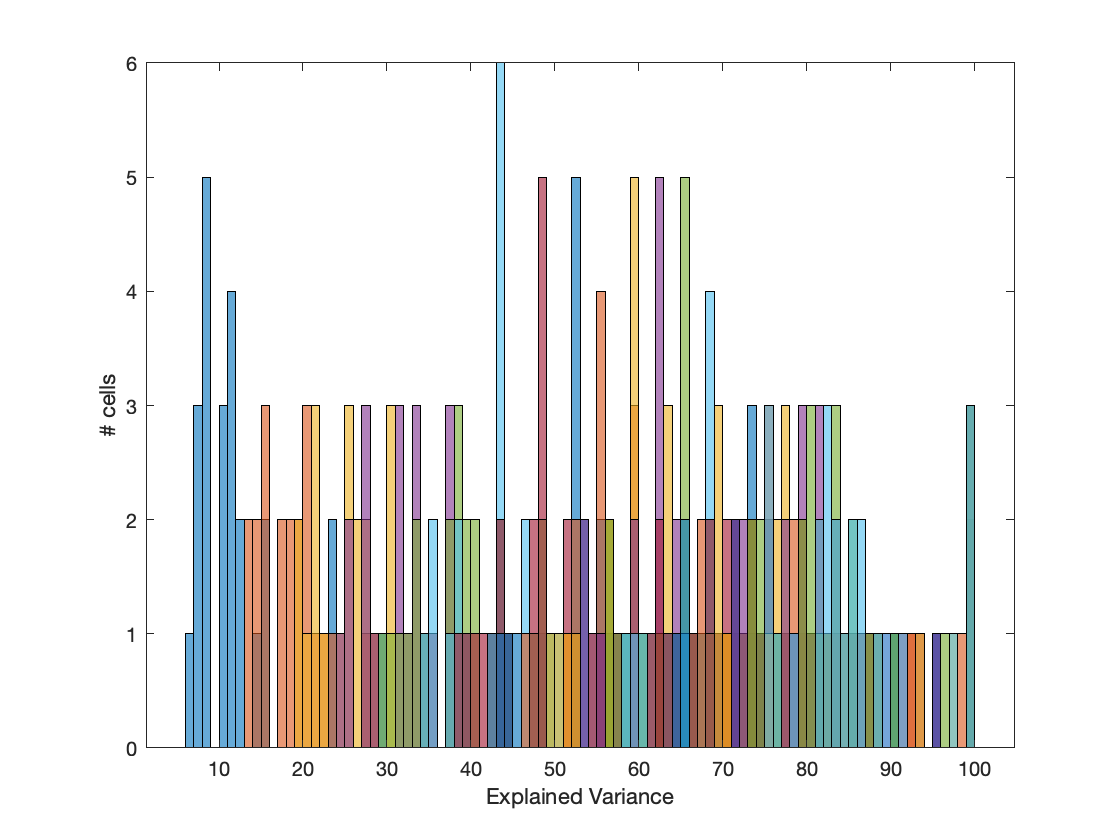


figure
for pp=1:20
    histogram(CumsumVE(:,pp),'BinWidth',1, 'DisplayName', sprintf('%d',pp))
    hold on
end
xlabel('Explained Variance')
ylabel('# cells')
hold off

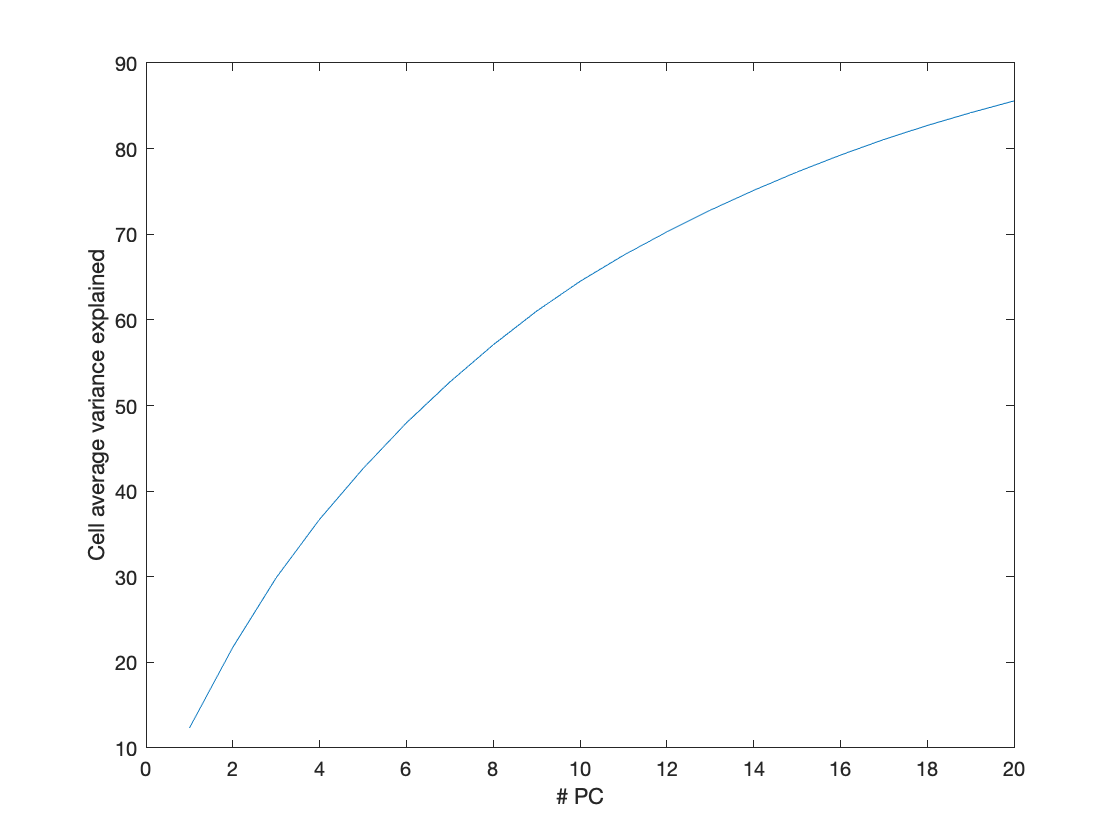


figure
plot(nanmean(CumsumVE))
xlabel('# PC')
ylabel('Cell average variance explained')

% Plot the average time varying rate
figure
shadedErrorBar([],mean(RateTrills_mat), std(RateTrills_mat)*(size(RateTrills_mat,2))^-0.5, {'k-','LineWidth',2});ylabel('Mean spike rate');xlabel('Time (s)');xticks(0:100:round(StimDuraOpt+1.5*Delay));xticklabels(-100:100:round(StimDuraOpt+Delay/2));title('Average spike rate during Trills over all vocalizer cells')
hold off


% Plot the first PC shapes
plot(PC(:,1), 'LineWidth',2);hold on;plot(PC(:,2), 'LineWidth',2);plot(PC(:,3), 'LineWidth',2);plot(PC(:,4), 'LineWidth',2);plot(PC(:,5), 'LineWidth',2);plot(PC(:,6), 'LineWidth',2);plot(PC(:,7), 'LineWidth',2);plot(PC(:,8), 'LineWidth',2);plot(PC(:,9), 'LineWidth',2);plot(PC(:,10), 'LineWidth',2);legend('PC1', 'PC2','PC3', 'PC4', 'PC5', 'PC6','PC7','PC8','PC9','PC10', 'Location', 'EastOutside'); ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(StimDuraOpt+1.5*Delay));xticklabels(-100:100:round(StimDuraOpt+Delay/2));title('PCA basis set of spike rate on Trill')
hold off

% plot all cells in the PC space
CellBatID = cell(1,NC);

for cc=1:NC
    [~,Name]=fileparts(ListCellsVocTrill{cc});
    CellBatID{cc} = str2double(Name(1:5)).*ones(1,NStims(cc));
end
CellBatID = [CellBatID{:}]';
gscatter(Score(:,1), Score(:,2), CellBatID)
xlabel('PC1')
ylabel('PC2')

% Obtain the matrix of neural distance for each cell
% calculate for each cell the centroid of the cloud of responses and find
% the neural pattern (the instance) that is closer to the centroid. It will
% Obtain the matrix of neural distance for each cell
% calculate for each cell the centroid of the cloud of responses and find
% the neural pattern (the instance) that is closer to the centroid. It will
% be used as a reference point to calculate distance to other instances
NPC = find(cumsum(VarExpl)>90,1);
NeuralVectorDistance = cell(NC,3); % first column: PCA over all responses from all cells; second column: PCA per cell; third column: zscored time average rate;fourth column PCA per cell + zscore Rate
NeuralMatrixDistance = cell(NC,3);% first column: PCA over all responses from all cells; second column: PCA per cell; third column: zscored time average rate; fourth column PCA per cell + zscore Rate
for cc=1:NC
    % Using Cellpopulation PCA
    % Find the rows in Score that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(cc)),1:min(NPC, floor(NStims(cc)/10)));
    % Calculate the centroid of the cloud of observations
    Centroid = mean(Score_local);
    % Find the observation that is closest to the centroid in Euclidean
    % distance, it will be used as a reference to calculate all other
    % distances
    D = squareform(pdist([Score_local; Centroid], 'seuclidean'));
    DCentroid = D(NStims(cc)+1,:);
    CentralInstance = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
    % Calculate the euclidean distance of all other points to the
    % reference point
    NeuralVectorDistance{cc,1} = D(CentralInstance(1), 1:end-1);
    NeuralMatrixDistance{cc,1} = D(1:(end-1), 1:end-1);
    
%     % Using individual cell PCA
%     Score_local2 = Score_per_cell{cc}(:,1:min(NPC_per_cell(cc), floor(NStims(cc)/10)));
%     % Calculate the centroid of the cloud of observations
%     Centroid = mean(Score_local2);
%     % Find the observation that is closest to the centroid in Euclidean
%     % distance, it will be used as a reference to calculate all other
%     % distances
%     D = squareform(pdist([Score_local2; Centroid], 'seuclidean'));
%     DCentroid = D(NStims(cc)+1,:);
%     CentralInstance2 = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
%     % Calculate the euclidean distance of all other points to the
%     % reference point
%     NeuralVectorDistance{cc,2} = D(CentralInstance2(1), 1:end-1);
%     NeuralMatrixDistance{cc,2} = D(1:(end-1), 1:end-1);

    % Using z-scored rate only
    % Calculate the centroid of the cloud of observations
    Centroid = mean(zscore(MeanRateTrills{cc}));
    % Find the observation that is closest to the centroid in Euclidean
    % distance, it will be used as a reference to calculate all other
    % distances
    D = squareform(pdist([zscore(MeanRateTrills{cc}) ; Centroid], 'seuclidean'));
    DCentroid = D(NStims(cc)+1,:);
    CentralInstance3 = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
    % Calculate the euclidean distance of all other points to the
    % reference point
    NeuralVectorDistance{cc,3} = D(CentralInstance3(1), 1:end-1);
    NeuralMatrixDistance{cc,3} = D(1:(end-1), 1:end-1);
    
%     % Using individual cell PCA + zscoreRate
%     Score_local3 = [Score_local2 zscore(MeanRateTrills{cc})];
%     % Calculate the centroid of the cloud of observations
%     Centroid = mean(Score_local3);
%     % Find the observation that is closest to the centroid in Euclidean
%     % distance, it will be used as a reference to calculate all other
%     % distances
%     D = squareform(pdist([Score_local3; Centroid], 'seuclidean'));
%     DCentroid = D(NStims(cc)+1,:);
%     CentralInstance4 = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
%     % Calculate the euclidean distance of all other points to the
%     % reference point
%     NeuralVectorDistance{cc,4} = D(CentralInstance4(1), 1:end-1);
%     NeuralMatrixDistance{cc,4} = D(1:(end-1), 1:end-1);

    % plot
    Col = zeros(NStims(cc),3);
    Col(CentralInstance(1),:) = [1 0 0];
%     tiledlayout(1,2)
%     nexttile
    scatter(zscore(MeanRateTrills{cc}),Score_local(:,1),40,Col, 'filled')
    xlabel('Mean Rate')
    ylabel('PC1')
    title(sprintf('Projection of Neural patterns from Cell %d/%d in population PC space', cc, NC))
%     nexttile
%     Col = zeros(NStims(cc),3);
%     Col(CentralInstance2(1),:) = [1 0 0];
%     scatter(zscore(MeanRateTrills{cc}),Score_local2(:,1),40,Col, 'filled')
%     xlabel('Mean Rate')
%     ylabel('PC1')
%     title(sprintf('Projection of Neural patterns from Cell %d/%d in cell PC space', cc, NC))
%     pause()
end

save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'NeuralMatrixDistance','NeuralVectorDistance','NPC', 'Score','NPC_per_cell','Score_per_cell','PC_per_cell','ListCellsVocTrill', '-append')

## Representing Vocalizations in an acoustic basis set

Let's represent Trills iteratively by PCA on a given time varying acoustic feature, substracting the time varying mean acoustic feature

% Import Biosound library
py.importlib.import_module('soundsig')

ans =   Python module with properties:

           sound: [1×1 py.module]
    detect_peaks: [1×1 py.module]
        timefreq: [1×1 py.module]
          signal: [1×1 py.module]

    <module 'soundsig' from '/Users/elie/anaconda3/lib/python3.7/site-packages/soundsig/__init__.py'>



% Obtain a large matrix of all single Trill time varying pitch, amplitude, saliency etc...
Trills_fund = cell(1,NC);
Trills_sal = cell(1,NC);
Trills_amp = cell(1,NC);
Trills_specMean = cell(1,NC);
Trills_formDisp = cell(1,NC);
Trills_mps = cell(1,NC);
Trills_mpsPiezo = cell(1,NC);
Trills_spectroPiezoto = cell(1,NC);
Trills_spectroPiezofo = cell(1,NC);
Trills_spectroPiezo = cell(1,NC);
Trills_spectroMicto = cell(1,NC);
Trills_spectroMicfo = cell(1,NC);
Trills_spectroMic = cell(1,NC);

% Time average PAF
% parameters that pertains to fundamental
PAF.meanfund = cell(1,NC);
PAF.cvfund = cell(1,NC);
PAF.minfund = cell(1,NC);
PAF.maxfund = cell(1,NC);
% Parameters of pitch saliency
PAF.meansal = cell(1,NC);
PAF.stdsal = cell(1,NC);
% paramters of sound amplitude
PAF.meanamp = cell(1,NC);
PAF.rms = cell(1,NC);
PAF.stdamp = cell(1,NC);
% Parameters of sound spectrum
PAF.meanspect = cell(1,NC);
PAF.stdspect = cell(1,NC);
PAF.entropyspect = cell(1,NC);
PAF.kurtspect = cell(1,NC);
PAF.skewspect = cell(1,NC);
PAF.q1 = cell(1,NC);
PAF.q2 = cell(1,NC);
PAF.q3 = cell(1,NC);
% Parameters of temporal dynamic
PAF.meantime = cell(1,NC);
PAF.stdtime = cell(1,NC);
PAF.entropytime = cell(1,NC);
PAF.kurttime = cell(1,NC);
PAF.skewtime = cell(1,NC);

SoundSpeed = 350;
Span=9;% Span is an unevennumber. smooth has a default span of 5 points = 5ms However end points are unchanged...
for cc=1:NC
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, NC)
    Cell = load(ListCellsVocTrill{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'VocTr') .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') .* (Cell.DelayBefore>=Delay) .* (Cell.DelayAfter>=Delay));
        
    end
    
    if NStims(cc) ~= length(IndVoc)
        warning('There is an issue! Check!')
        keyboard
    end

    % initialize the matrix of acoustic values with zeros
    Trills_fund{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_sal{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_amp{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_specMean{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_formDisp{cc} = zeros(max(StimDuraMax),length(IndVoc));
    Trills_mps{cc} = cell(1, length(IndVoc));
    Trills_mpsPiezo{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezo{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezoto{cc} = cell(1, length(IndVoc));
    Trills_spectroPiezofo{cc} = cell(1, length(IndVoc));
    Trills_spectroMic{cc} = cell(1, length(IndVoc));
    Trills_spectroMicto{cc} = cell(1, length(IndVoc));
    Trills_spectroMicfo{cc} = cell(1, length(IndVoc));
    
    % initialize the matrix of time average PAF with nan
    % parameters that pertains to fundamental
    PAF.meanfund{cc} = nan(1,length(IndVoc));
    PAF.cvfund{cc} = nan(1,length(IndVoc));
    PAF.minfund{cc} = nan(1,length(IndVoc));
    PAF.maxfund{cc} = nan(1,length(IndVoc));
    % Parameters of pitch saliency
    PAF.meansal{cc} = nan(1,length(IndVoc));
    PAF.stdsal{cc} = nan(1,length(IndVoc));
    % paramters of sound amplitude
    PAF.meanamp{cc} = nan(1,length(IndVoc));
    PAF.rms{cc} = nan(1,length(IndVoc));
    PAF.stdamp{cc} = nan(1,length(IndVoc));
    % Parameters of sound spectrum
    PAF.meanspect{cc} = nan(1,length(IndVoc));
    PAF.stdspect{cc} = nan(1,length(IndVoc));
    PAF.entropyspect{cc} = nan(1,length(IndVoc));
    PAF.kurtspect{cc} = nan(1,length(IndVoc));
    PAF.skewspect{cc} = nan(1,length(IndVoc));
    PAF.q1{cc} = nan(1,length(IndVoc));
    PAF.q2{cc} = nan(1,length(IndVoc));
    PAF.q3{cc} = nan(1,length(IndVoc));
    % Parameters of temporal dynamic
    PAF.meantime{cc} = nan(1,length(IndVoc));
    PAF.stdtime{cc} = nan(1,length(IndVoc));
    PAF.entropytime{cc} = nan(1,length(IndVoc));
    PAF.kurttime{cc} = nan(1,length(IndVoc));
    PAF.skewtime{cc} = nan(1,length(IndVoc));
    
    % Load the mps data corresponding to that cell
    [~,Filename,~] = fileparts(ListCellsVocTrill{cc});
    MPSMic_file = fullfile(Path2AllData, [Filename(1:14) '_MPSMic.mat']);
    MPSPiezo_file = fullfile(Path2AllData, [Filename(1:14) '_MPSPiezo.mat']);
    MPSMic_data = load(MPSMic_file);
    MPSPiezo_data = load(MPSPiezo_file);
    
    % collect the Time varying smoothed acoustic features for each
    % vocalization
    for Nstim = 1:NStims(cc)
        StimDur = length(Cell.BioSound{IndVoc(Nstim),1}.amp);
        Trills_fund{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),2}.f0, Span);
        Trills_sal{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.sal, Span);
        Trills_amp{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.amp, Span);
        Trills_specMean{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.SpectralMean, Span);
        F1 = double(Cell.BioSound{IndVoc(Nstim),1}.F1);
        F2 = double(Cell.BioSound{IndVoc(Nstim),1}.F2);
        Trills_formDisp{cc}(1:StimDur,Nstim) = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
        % Retrieve the MPS on the Mic and save it
        Local_Idx = find(MPSMic_data.IndVoc == IndVoc(Nstim));
        if ~strcmp('VocTr',MPSMic_data.Voc_what{Local_Idx}) || ~strcmp('self',MPSMic_data.Voc_who{Local_Idx})
            warning('There is an issue of indexing!!')
            keyboard
        end
        Trills_mps{cc}{Nstim} = MPSMic_data.Voc_mps{Local_Idx};
        if Nstim == NStims(cc)
            Trills_wt = MPSMic_data.Voc_wt;
            Trills_wf = MPSMic_data.Voc_wf;
        end
        % Retrieve the MPS on the Piezo and save it
        Local_Idx = find(MPSPiezo_data.IndVoc == IndVoc(Nstim));
        if ~strcmp('VocTr',MPSPiezo_data.Voc_what{Local_Idx}) || ~strcmp('self',MPSPiezo_data.Voc_who{Local_Idx})
            warning('There is an issue of indexing!!')
            keyboard
        end
        Trills_mpsPiezo{cc}{Nstim} = MPSPiezo_data.Voc_mps{Local_Idx};
        if Nstim == NStims(cc)
            Trills_wtPiezo = MPSPiezo_data.Voc_wt;
            Trills_wfPiezo = MPSPiezo_data.Voc_wf;
        end

        Trills_spectroPiezo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.spectro;
        Trills_spectroPiezoto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.to;
        Trills_spectroPiezofo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),2}.fo;
        Trills_spectroMic{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.spectro;
        Trills_spectroMicto{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.to;
        Trills_spectroMicfo{cc}{Nstim} = Cell.BioSound{IndVoc(Nstim),1}.fo;
        
        % collect PAF
        % parameters that pertains to fundamental
        if isnumeric(Cell.BioSound{IndVoc(Nstim),2}.fund) % fundamental paraneters cannot be calculated for noisy calls (poor pitch saliency)
            PAF.meanfund{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),2}.fund;
            PAF.cvfund{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),2}.cvfund;
            PAF.minfund{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),2}.minfund;
            PAF.maxfund{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),2}.maxfund;
        end
        % Parameters of pitch saliency
        PAF.meansal{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.meansal;
        PAF.stdsal{cc}(Nstim) = std(Cell.BioSound{IndVoc(Nstim),1}.sal, 'omitnan');
        % paramters of sound amplitude
        PAF.meanamp{cc}(Nstim) = mean(Cell.BioSound{IndVoc(Nstim),1}.amp, 'omitnan');
        PAF.rms{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.rms;
        PAF.stdamp{cc}(Nstim) = std(Cell.BioSound{IndVoc(Nstim),1}.amp, 'omitnan');
        % Parameters of sound spectrum
        PAF.meanspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.meanspect;
        PAF.stdspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.stdspect;
        PAF.entropyspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.entropyspect;
        PAF.kurtspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.kurtosisspect;
        PAF.skewspect{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.skewspect;
        PAF.q1{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.q1;
        PAF.q2{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.q2;
        PAF.q3{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.q3;
        % Parameters of temporal dynamic
        PAF.meantime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.meantime;
        PAF.stdtime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.stdtime;
        PAF.entropytime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.entropytime;
        PAF.kurttime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.kurtosistime;
        PAF.skewtime{cc}(Nstim) = Cell.BioSound{IndVoc(Nstim),1}.skewtime;

    end
end

Cell 1/24
Cell 2/24
Cell 3/24
Cell 4/24
Cell 5/24
Cell 6/24
Cell 7/24
Cell 8/24
Cell 9/24
Cell 10/24
Cell 11/24
Cell 12/24
Cell 13/24
Cell 14/24
Cell 15/24
Cell 16/24
Cell 17/24
Cell 18/24
Cell 19/24
Cell 20/24
Cell 21/24
Cell 22/24
Cell 23/24
Cell 24/24


save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_Ac.mat'), 'Trills_fund','Trills_amp','Trills_formDisp', 'Trills_sal', 'Trills_specMean','Trills_mps','Trills_wt', 'Trills_wf','Trills_mpsPiezo','Trills_wtPiezo', 'Trills_wfPiezo','Trills_spectroPiezo', 'Trills_spectroPiezoto','Trills_spectroPiezofo', 'PAF')
save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_spectroMic.mat'), 'Trills_spectroMic','Trills_spectroMicto','Trills_spectroMicfo', '-v7.3')

## Analysis using the MPS

For each cell, find the extreme quartiles in the Neural space, then calculate the average MPS for each quartile and the distance between these average MPS, Bootstrap the calculation by calculating 10000 groups of vocalizations of the same sizes as quartile groups and finding the distribution of MPS values for all of them.

File 11/24


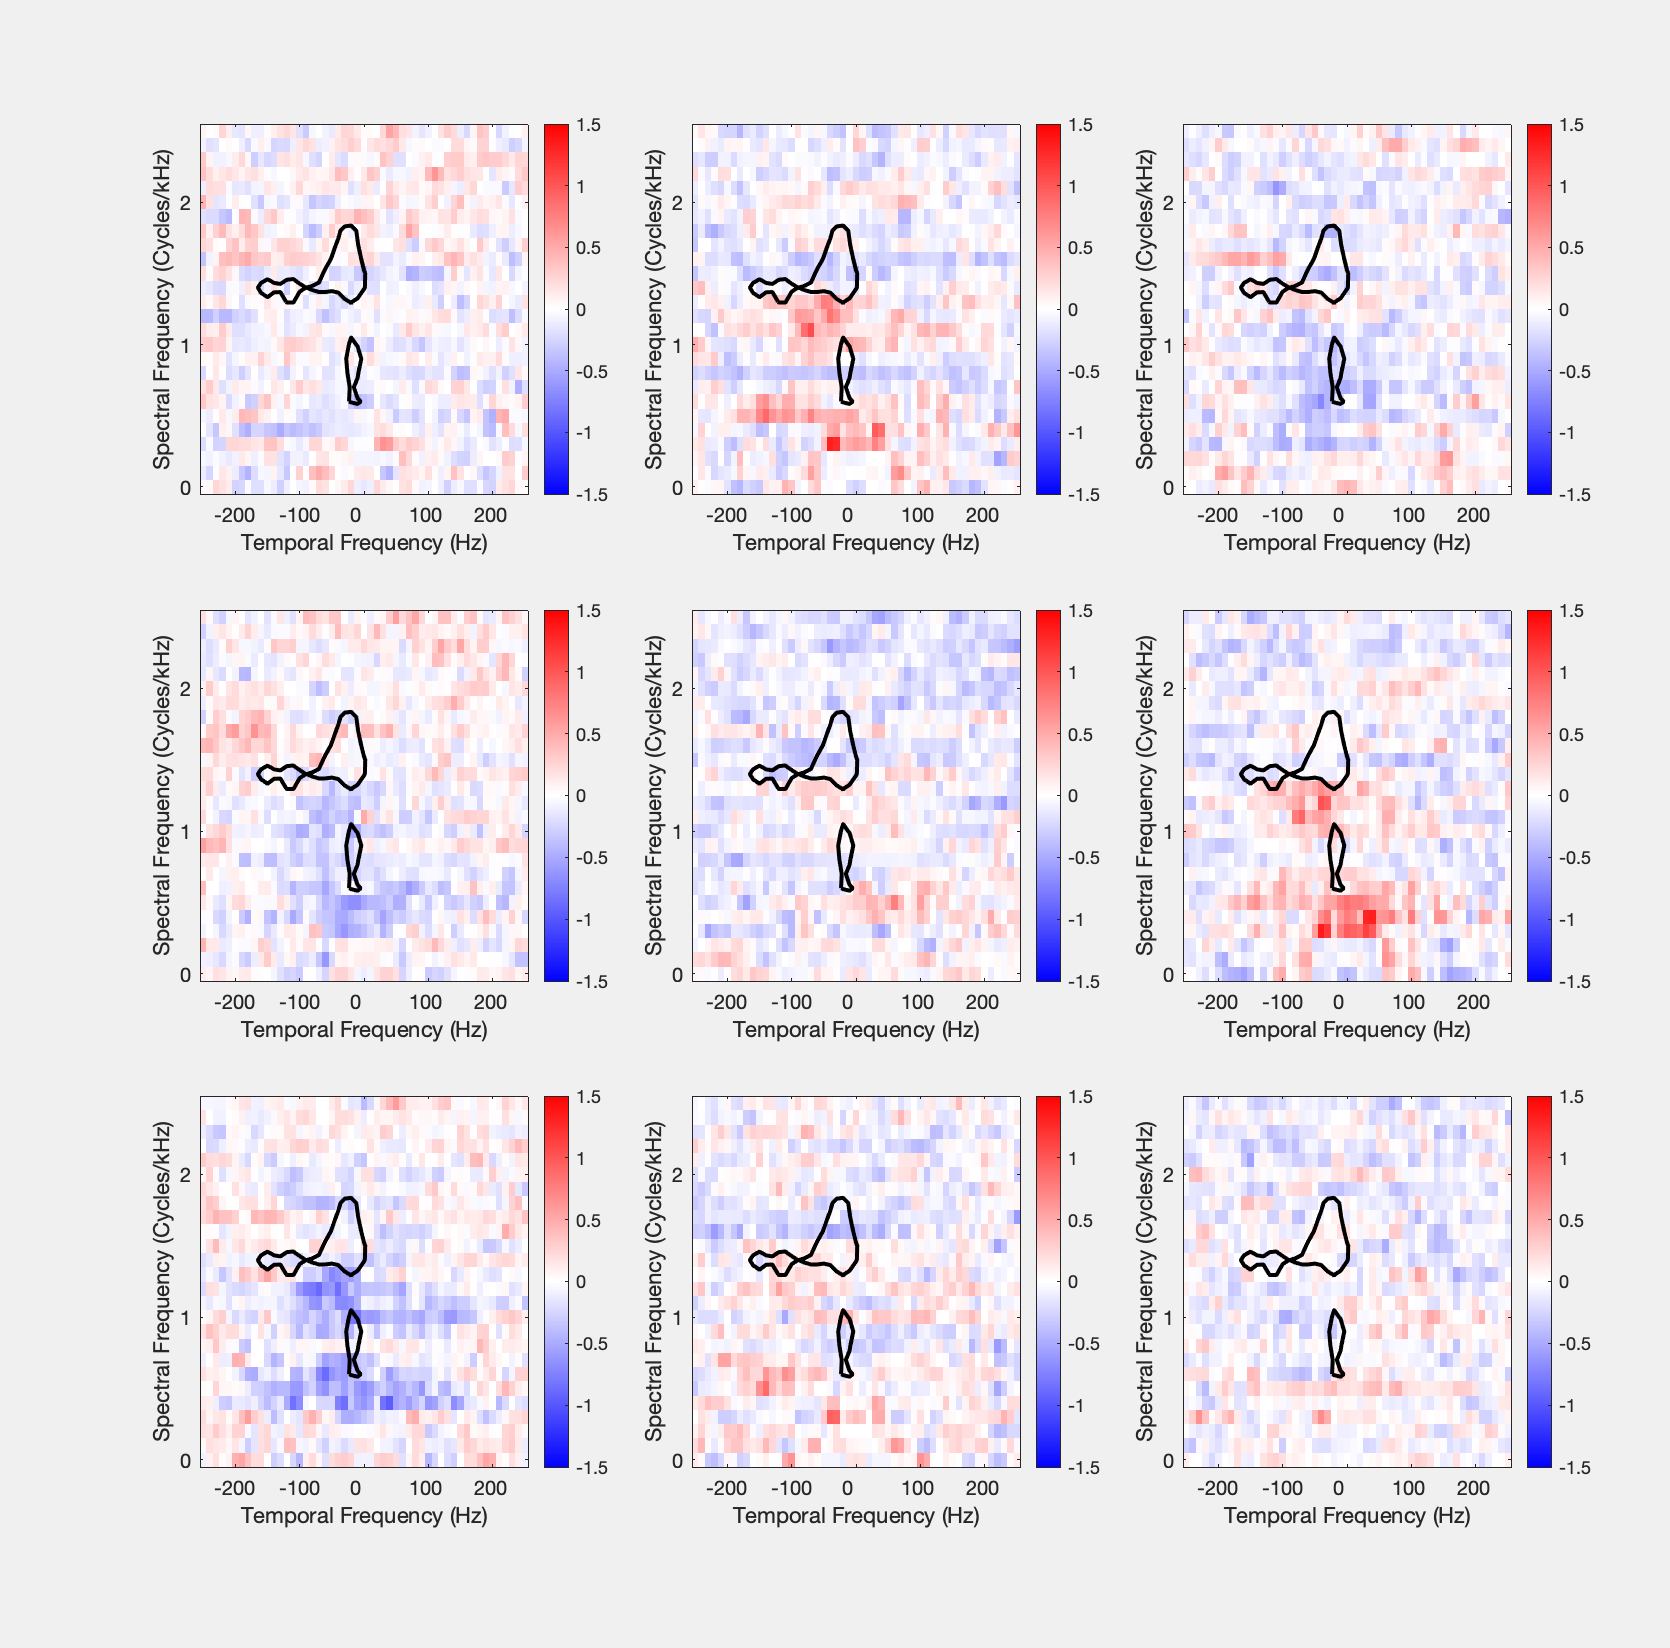

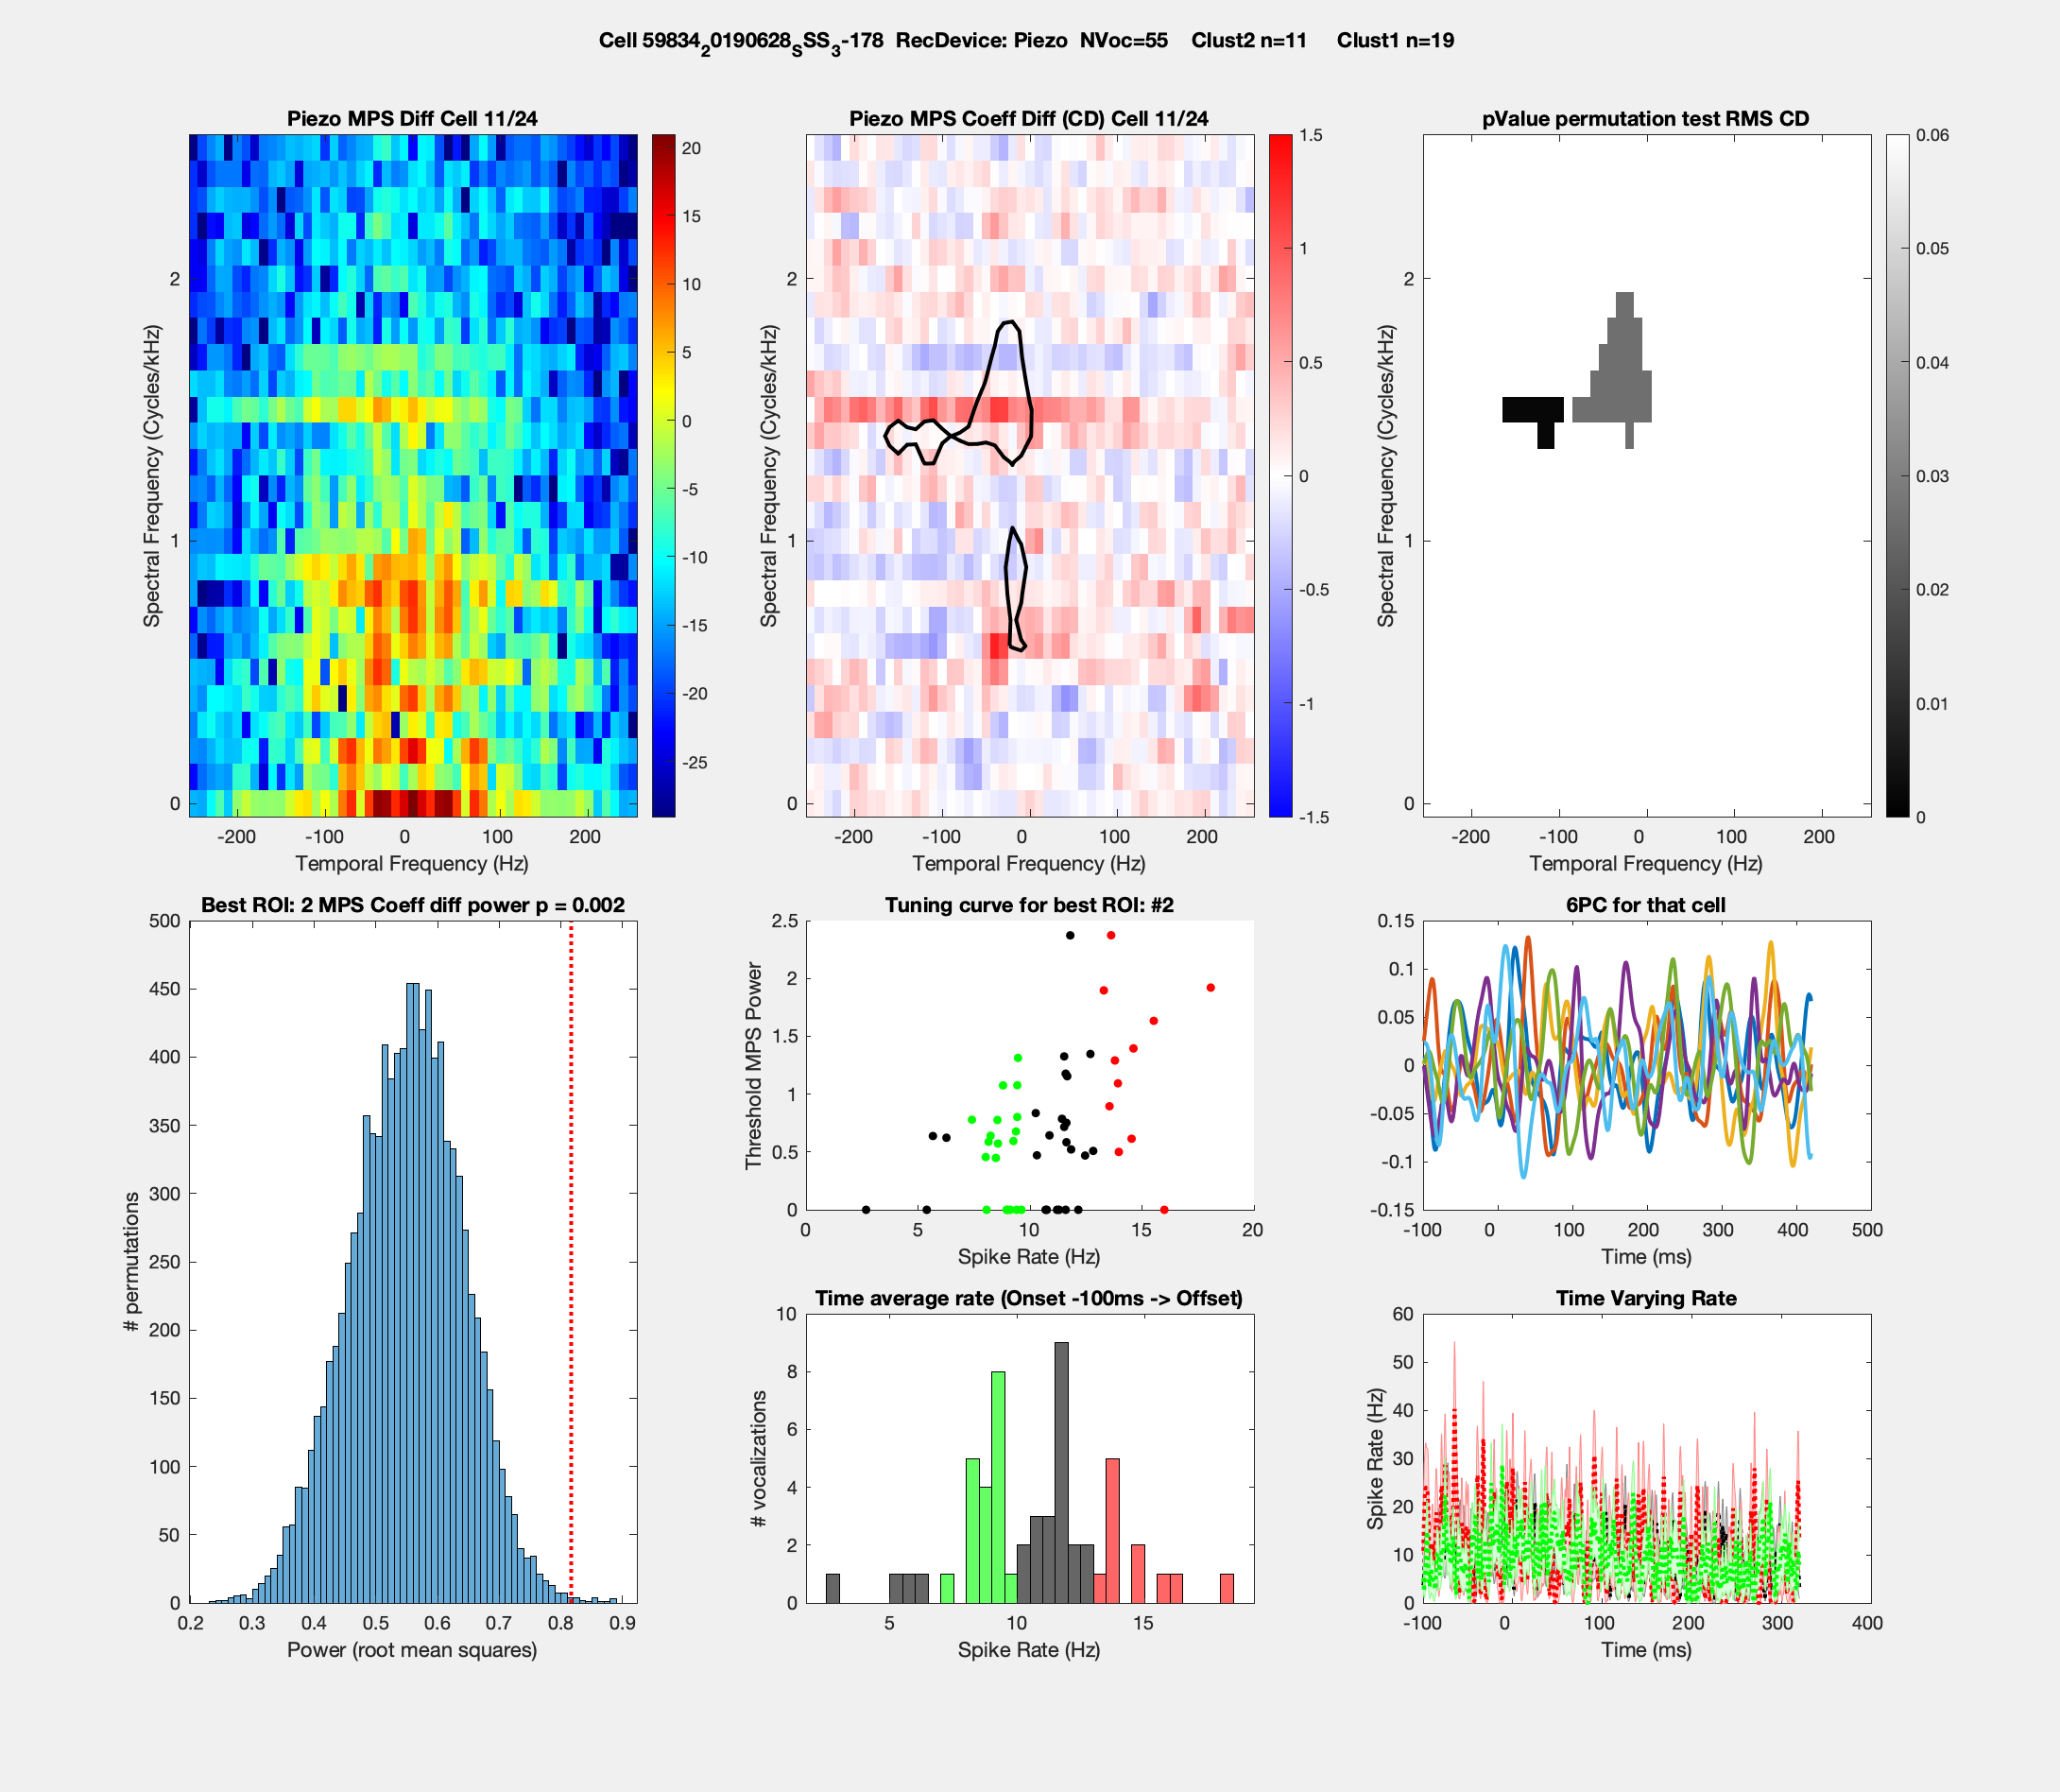

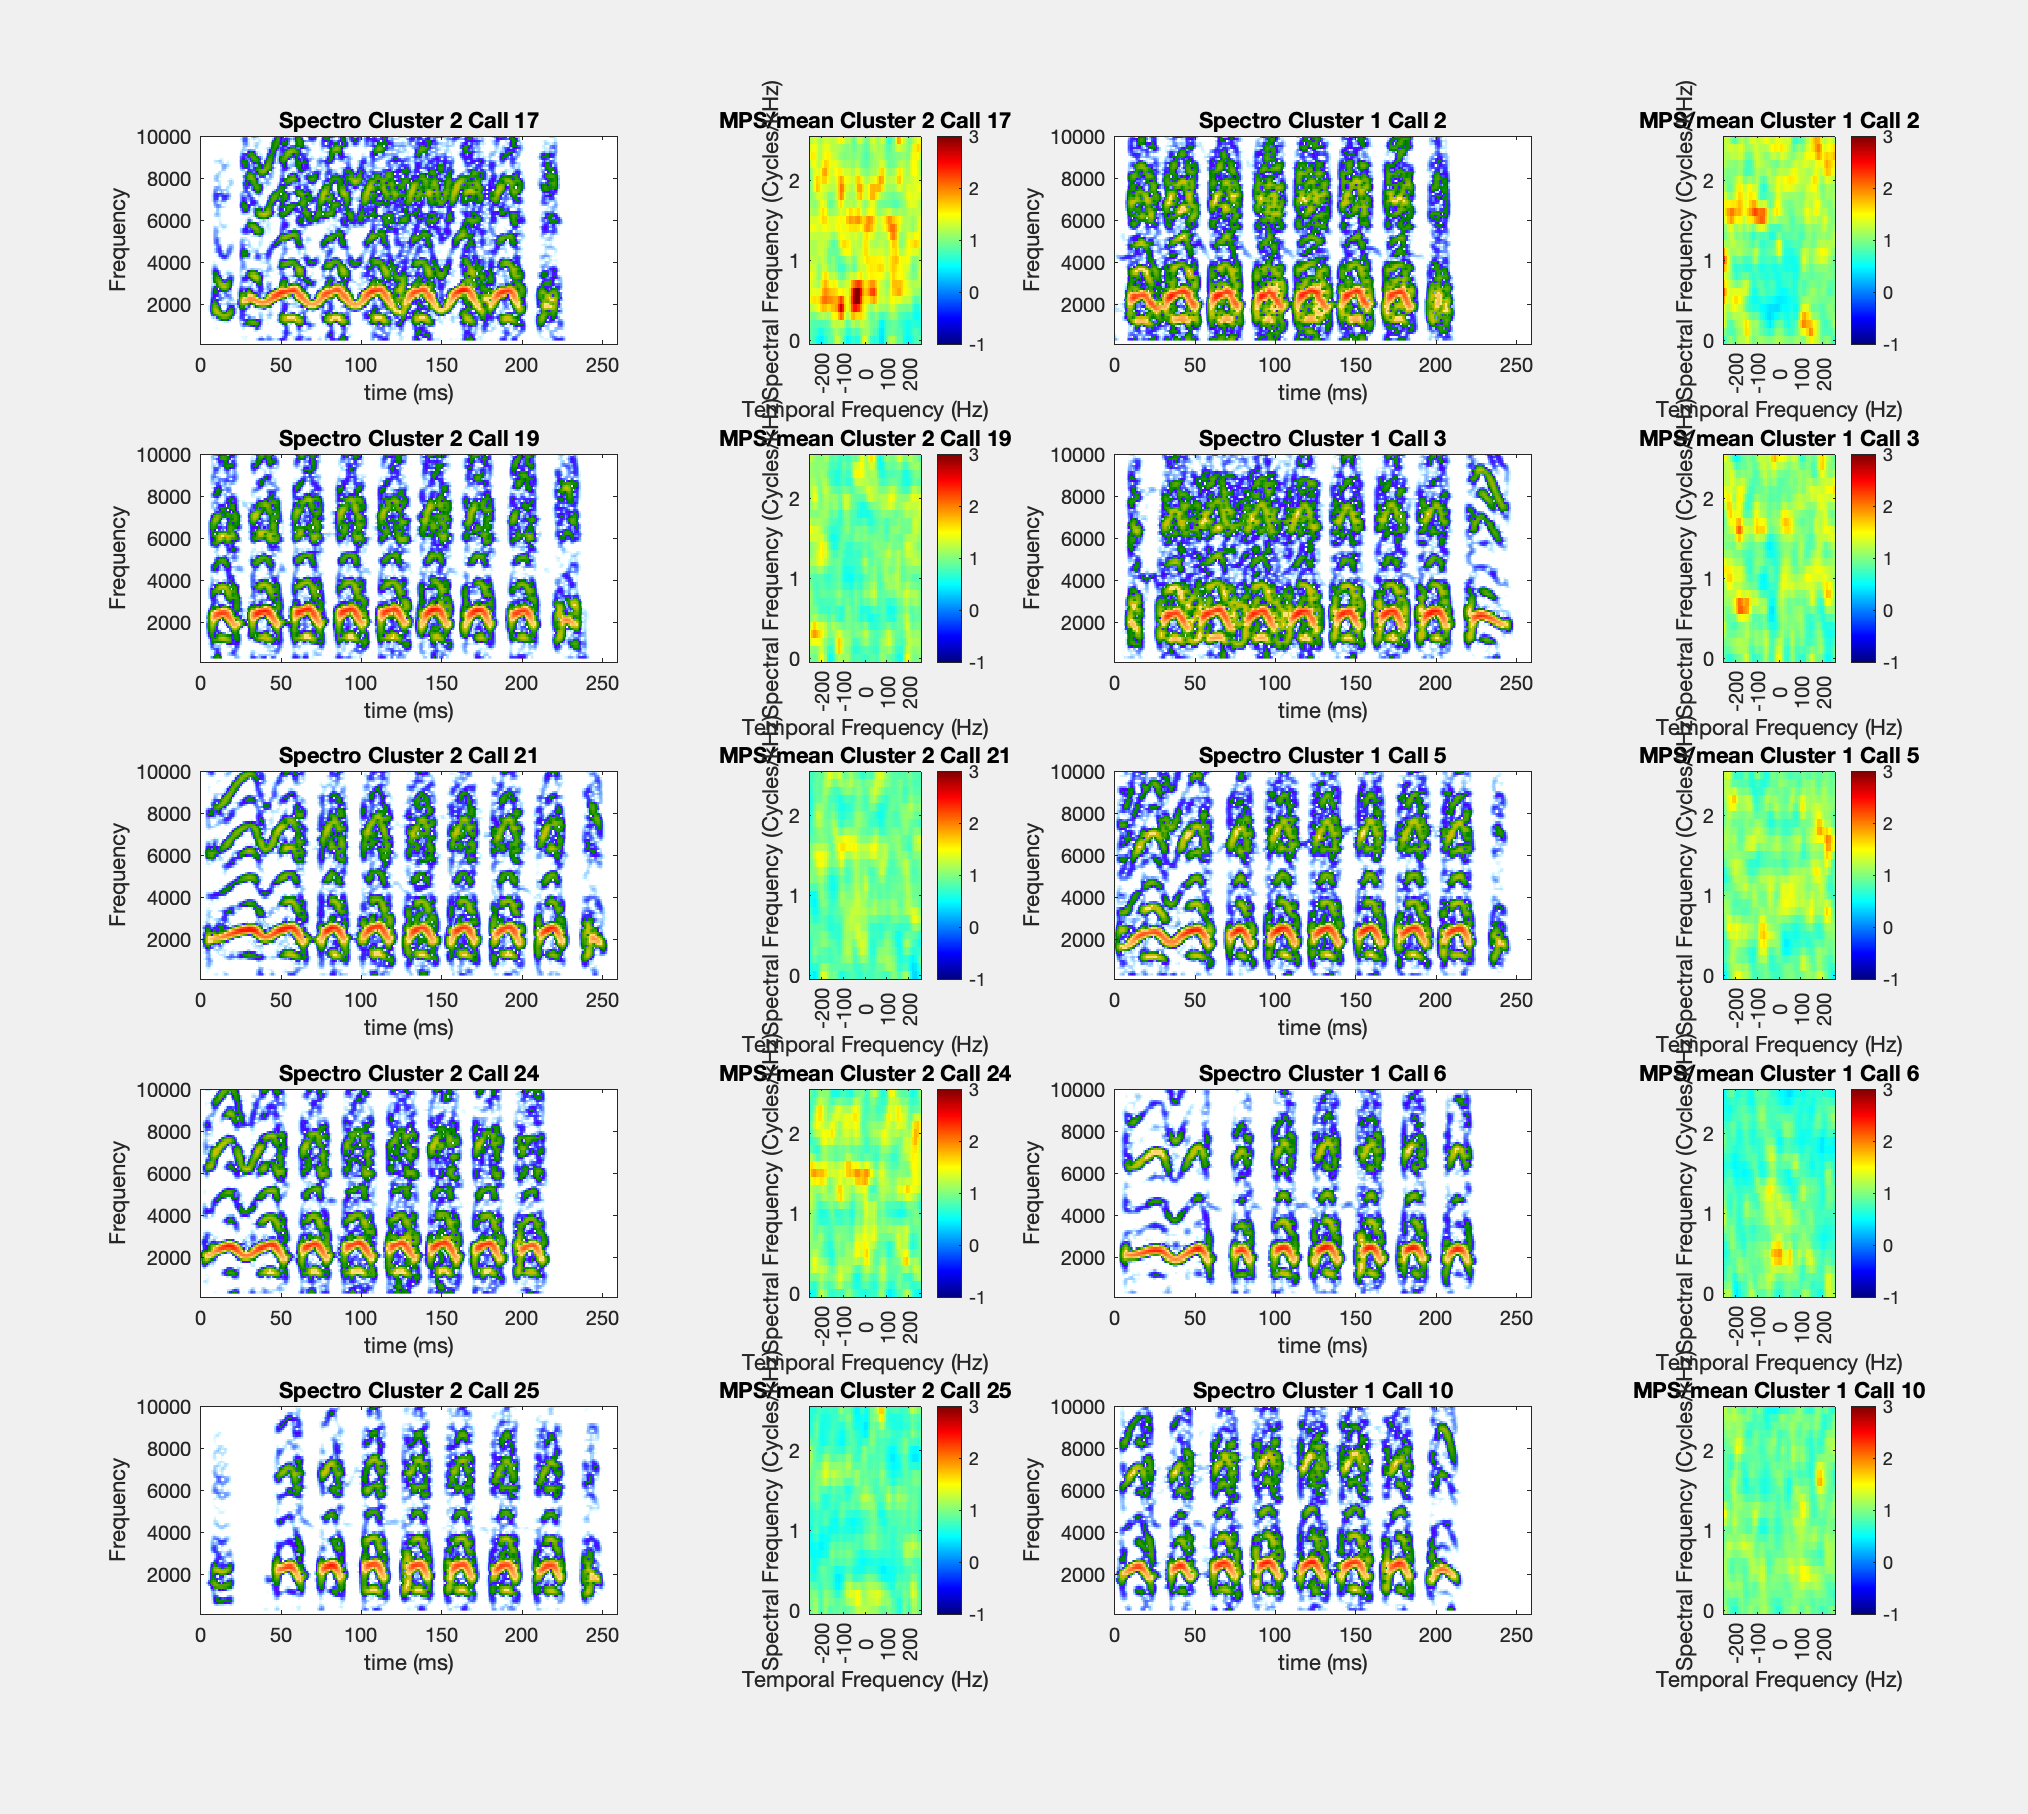

RecDevice = 'Piezo'; % Set as 'Mic' or 'Piezo' Last run for Piezo on 07/08/2022 and Mic on 07/08/2022
NBoot = 10000;
ClustNum = 4;
DBNoise = 50;
CMAP = [[(1:128)'./128; ones(128,1)] [(1:128)'./128;flip((1:128)'./128)] [ones(128,1);flip((1:128)'./128)]];

RateTrills_mat = [RateTrills{:}]';
if strcmp(RecDevice, 'Mic')
    load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_spectroMic.mat'), 'Trills_spectroMic','Trills_spectroMicto','Trills_spectroMicfo')
elseif strcmp(RecDevice, 'Piezo')
    load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_Ac.mat'), 'Trills_spectroPiezo','Trills_spectroPiezoto','Trills_spectroPiezofo')
end

% load the contour of each vocalizer bat:
VocOperantID = {'11689', '59834'};
ROI_num = nan(1,length(VocOperantID));
for BB=1:length(VocOperantID)
    BatID = VocOperantID{BB};
    load(fullfile(Path2AllData,sprintf('%s_MPS_ROI_Trills_%s.mat', BatID, RecDevice)), 'SeparateContour','Level', 'ROI','BatAllTrillsMPS', 'Wf_ROI', 'Wt_ROI')
    SeparateContour_all.(sprintf('M%s',BatID)) = SeparateContour;
    Level_all.(sprintf('M%s',BatID)) = Level;
    MeanMPS.(sprintf('M%s',BatID)) = mean(BatAllTrillsMPS)';
    ROI_all.(sprintf('M%s',BatID)) = ROI;
    ROI_num(BB) = length(ROI);
end
% Get the size of the smallest ROI:
ROIMin = min([cellfun(@(x) sum(sum(x)), ROI_all.M11689); cellfun(@(x) sum(sum(x)), ROI_all.M59834)]);

MPSDiff_Trills = cell(NC,1);
% MPSDiff_p = cell(NC,1);
% MPSDiff_Trills_rand_all = cell(NC,1);
% MPSDiff_Trills_randRMS = cell(NC,1);
% MPSDiff_Trills_RMS = nan(NC,max(ROI_num));
% MPSDiff_Trills_RMSp = nan(NC,max(ROI_num));


MPSCoeffDiff_Trills = cell(NC,1);
% MPSCoeffDiff_p = cell(NC,1);
MPSCoeffDiff_Trills_rand_all = cell(NC,1);
MPSCoeffDiff_Trills_randRMS = cell(NC,1);
MPSCoeffDiff_Trills_RMS = nan(NC,max(ROI_num));
MPSCoeffDiff_Trills_RMSp = nan(NC,max(ROI_num));

if strcmp(RecDevice, 'Mic')
    % Load mps from previous cells if not just calculated
    load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_Ac.mat'), 'Trills_mps', 'Trills_wt', 'Trills_wf')
    
elseif strcmp(RecDevice, 'Piezo')
    % Load mps from previous cells if not just calculated
    load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_Ac.mat'), 'Trills_mpsPiezo', 'Trills_wtPiezo', 'Trills_wfPiezo')
    Trills_wf = Trills_wfPiezo;
    Trills_wt = Trills_wtPiezo;
    Trills_mps = Trills_mpsPiezo;
    
end

Wf_pos = logical((Trills_wf>=0) .* (Trills_wf*10^3<=2.5));
Wt_narrow = logical((Trills_wt>=-250) .* (Trills_wt<=250));



for cc=1:NC
    fprintf(1, 'File %d/%d\n', cc, NC)
    % find the extreme quartiles in Neural PC space + Z-scored Rate
    ZSRate = (MeanRateTrills{cc} - mean(MeanRateTrills{cc}))./std(MeanRateTrills{cc});
    Score_local = [ZSRate Score_per_cell{cc}(:,1:min(NPC_per_cell(cc), floor(NStims(cc)/10)))];
    [Idx, ClustMaxD] = find_extreme_clusters(Score_local, ClustNum, {'kmeans', 'RecursivePoint'});
    if isnan(Idx)
        [Idx, ClustMaxD] = find_extreme_clusters(Score_local, ClustNum, {'kmeans', 'RecursiveCluster'});
    end

    
    % Get the MPS for both clusters
    Trills_mps_local = cell(length(ClustMaxD),1);
    for Clust = 1:length(ClustMaxD)
        Trills_mps_local{Clust} = Trills_mps{cc}(Idx == ClustMaxD(Clust));
    end

    % Get the average MPS over all vocalizations for that Bat
    % Retrieve the name of the Vocalizer and the corresponding average Trill MPS
    [~,Name]=fileparts(ListCellsVocTrill{cc});
    Trills_mps_mean = MeanMPS.(sprintf('M%s',Name(1:5)));
    ROI = ROI_all.(sprintf('M%s', Name(1:5)));
    SeparateContour = SeparateContour_all.(sprintf('M%s',Name(1:5)));
    Level = Level_all.(sprintf('M%s', Name(1:5)));

    % Get the MPS Power in each ROI of all vocalizations for plot purposes
    MPSPower_Cell = nan(NStims(cc), length(ROI));
    for Stim=1:NStims(cc)
        MPS = Trills_mps{cc}{Stim}./Trills_mps_mean;
        MPSNorm = reshape(MPS,length(Trills_wf), length(Trills_wt));
        MPSNorm = MPSNorm(Wf_pos,Wt_narrow);
        MPSNorm_vec = reshape(MPSNorm, numel(MPSNorm),1);
        for rr=1:length(ROI)
            ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
            MPSNorm_vecROI=abs(MPSNorm_vec(ROI_local));
            if ~any(MPSNorm_vecROI>=Level)
                MPSPower_Cell (Stim, rr) = 0;
            else
                % order values by decreasing order and select all
                % values above the Level choosen for ROI or all the
                % higher values with a minimum of n=ROIMin values.
                RMSValues = sort(MPSNorm_vecROI, 'descend');
                UsefullValuesInd = max(ROIMin,find(RMSValues>=Level,1,'last'));
                MPSPower_Cell(Stim, rr) = mean(RMSValues(1:UsefullValuesInd));
            end
        end
    end

    % Get the matrix of MPS difference between the 2 clusters for ploting
    % purposes
    MPSDiff_vec = mean([Trills_mps_local{1}{:}],2) - mean([Trills_mps_local{2}{:}],2);
    MPSDiff_mat = reshape(MPSDiff_vec, length(Trills_wf), length(Trills_wt));
    MPSDiff_Trills{cc} = MPSDiff_mat(Wf_pos,Wt_narrow);
    MPSDiff_vec_upper = reshape(MPSDiff_Trills{cc},numel(MPSDiff_Trills{cc}),1);

    % Get the MPS coefficient difference between the 2 clusters for
    % plotting purposes
    MPSCoeffDiff_vec = MPSDiff_vec ./ Trills_mps_mean;
    MPSCoeffDiff_mat = reshape(MPSCoeffDiff_vec, length(Trills_wf), length(Trills_wt));
    MPSCoeffDiff_Trills{cc} = MPSCoeffDiff_mat(Wf_pos,Wt_narrow);
    MPSCoeffDiff_vec_upper = reshape(MPSCoeffDiff_Trills{cc},numel(MPSCoeffDiff_Trills{cc}),1);
    
    % Get the cell array of MPS coefficient pair differences between the 2
    % clusters for statistic purposes
    MPSCoeffDiffRMS_perstim = nan(length(Trills_mps_local{1}),length(Trills_mps_local{2}), length(ROI));
    for Stim1=1:length(Trills_mps_local{1})
        MPS1 = Trills_mps_local{1}{Stim1}./Trills_mps_mean;
        for Stim2=1:length(Trills_mps_local{2})
            MPS2 = Trills_mps_local{2}{Stim2}./Trills_mps_mean;
            MPSNormDiff = reshape(MPS1-MPS2, length(Trills_wf), length(Trills_wt));
            MPSNormDiff = MPSNormDiff(Wf_pos,Wt_narrow);
            MPSCoeffDiff_vec = reshape(MPSNormDiff, numel(MPSNormDiff),1);
            for rr=1:length(ROI)
                ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
                MPSCoeffDiff_vecROI=abs(MPSCoeffDiff_vec(ROI_local));
                if ~any(MPSCoeffDiff_vecROI>=Level)
                    MPSCoeffDiffRMS_perstim(Stim1, Stim2, rr) = 0;
                else
                    % order values by decreasing order and select all
                    % values above the Level choosen for ROI or all the
                    % higher values with a minimum of n=ROIMin values.
                    RMSValues = sort(MPSCoeffDiff_vecROI, 'descend');
                    UsefullValuesInd = max(ROIMin,find(RMSValues>=Level,1,'last'));
                    MPSCoeffDiffRMS_perstim(Stim1, Stim2, rr) = mean(RMSValues(1:UsefullValuesInd));
                end
            end
        end
    end




    % randomly sample groups of vocalizations, calculate distribution of MPSDiff
%     MPSDiff_rand = cell(NBoot,1);
%     MPSDiff_Trills_randRMS{cc} = nan(NBoot,length(ROI));% This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
    MPSCoeffDiff_rand = cell(NBoot,1);
    MPSCoeffDiff_Trills_randRMS{cc} = nan(NBoot,length(ROI)); % This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
    F2 = figure(2);
    set(F2,'Visible','on')
    if cc==1
        % Stop to manually enlarge the figure as landscape
        keyboard
    end
    clf(F2)
    tiledlayout(3,3)
    for bb=1:NBoot
        Idx_rand = Idx(randperm(length(Idx)));
        % Get the average MPS for both clusters
        Trills_mps_local = cell(length(ClustMaxD),1);
        for Clust = 1:length(ClustMaxD)
            Trills_mps_local{Clust} = Trills_mps{cc}(Idx_rand == ClustMaxD(Clust));
        end

        % Get the MPS difference between the 2 clusters
        MPSDiff_rand_vec = mean([Trills_mps_local{1}{:}],2) - mean([Trills_mps_local{2}{:}],2);
%         MPSDiff_rand_mat = reshape(MPSDiff_rand_vec, length(Trills_wf), length(Trills_wt));
%         MPSDiff_rand_mat_upper = MPSDiff_rand_mat(Wf_pos,Wt_narrow);
%         MPSDiff_rand{bb} = reshape(MPSDiff_rand_mat_upper, numel(MPSDiff_rand_mat_upper),1);
%         for rr=1:length(ROI)
%             ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
%             % Get the threshold RMS
%             MPSDiff_Trills_randRMS{cc}(bb,rr) = (mean(MPSDiff_rand{bb}(logical(ROI_local)).^2)).^0.5;
%         end
        
        % Get the MPS coefficient difference between the 2 clusters
        MPSCoeffDiff_rand_vec = MPSDiff_rand_vec ./ Trills_mps_mean;
        MPSCoeffDiff_rand_mat = reshape(MPSCoeffDiff_rand_vec, length(Trills_wf), length(Trills_wt));
        MPSCoeffDiff_rand_mat_upper = MPSCoeffDiff_rand_mat(Wf_pos,Wt_narrow);
        MPSCoeffDiff_rand{bb} = reshape(MPSCoeffDiff_rand_mat_upper, numel(MPSCoeffDiff_rand_mat_upper),1);

        % Get the cell array of MPS coefficient pair differences between the 2
        % clusters for statistic purposes, and the threshold RMS for each
        % ROI for each pair of vocalizations
        MPSCoeffDiffRMS_perstim_rand = nan(length(Trills_mps_local{1}),length(Trills_mps_local{2}),length(ROI));% This is the matrix
        for Stim1=1:length(Trills_mps_local{1})
            MPS1 = Trills_mps_local{1}{Stim1}./Trills_mps_mean;
            for Stim2=1:length(Trills_mps_local{2})
                MPS2 = Trills_mps_local{2}{Stim2}./Trills_mps_mean;
                MPSNormDiff = reshape(MPS1-MPS2, length(Trills_wf), length(Trills_wt));
                MPSNormDiff = MPSNormDiff(Wf_pos,Wt_narrow);
                MPSCoeffDiff_vec = reshape(MPSNormDiff, numel(MPSNormDiff),1);
                for rr=1:length(ROI)
                    ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
                    MPSCoeffDiff_vecROI=abs(MPSCoeffDiff_vec(ROI_local));
                    if ~any(MPSCoeffDiff_vecROI>=Level)
                        MPSCoeffDiffRMS_perstim_rand(Stim1, Stim2, rr) =0;
                    else
                        % order values by decreasing order and select all
                        % values above the Level choosen for ROI or all the
                        % higher values with a minimum of n=ROIMin values.
                        RMSValues = sort(MPSCoeffDiff_vecROI, 'descend');
                        UsefullValuesInd = max(ROIMin,find(RMSValues>=Level,1,'last'));
                        MPSCoeffDiffRMS_perstim_rand(Stim1, Stim2, rr) = mean(RMSValues(1:UsefullValuesInd));
                    end
                end
            end
        end
        
        % for each ROI, take the average over the bin averaged paired differences
        % threshold RMS
        for rr=1:length(ROI)
            MPSCoeffDiff_Trills_randRMS{cc}(bb,rr) = mean(reshape(MPSCoeffDiffRMS_perstim_rand(:,:,rr),[],1));
        end

        if (~rem(bb,NBoot/10)) && (bb<NBoot)
            NT = nexttile;
            plot_mps(MPSCoeffDiff_rand_mat_upper, Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,0, [0 2.5], [-250 250]);
            caxis([-1.5 1.5])
            colormap(CMAP)
            hold on
            for cont=1:length(SeparateContour)
                plot(SeparateContour{cont}(1,:),SeparateContour{cont}(2,:), 'k-', 'LineWidth',2)
                hold on
            end
            hold off

        end
    end
%     MPSDiff_Trills_rand_all{cc} = [MPSDiff_rand{:}]';
    MPSCoeffDiff_Trills_rand_all{cc} = [MPSCoeffDiff_rand{:}]';
    
    % Not useful anymore
%     MPSDiff_p{cc} = sum(abs(MPSDiff_rand_all{cc})>abs(MPSDiff_vec_upper'))./NBoot;
%     MPSDiff_pclean = imgaussfilt(MPSDiff_p{cc},0.5);
%     MPSDiff_pclean(MPSDiff_pclean>1) = 1;
%     MPSCoeffDiff_p{cc} = sum(abs(MPSCoeffDiff_rand_all{cc})>abs(MPSCoeffDiff_vec_upper'))./NBoot;
%     MPSCoeffDiff_pclean = imgaussfilt(MPSCoeffDiff_p{cc},0.5);
%     MPSCoeffDiff_pclean(MPSCoeffDiff_pclean>1) = 1;
%   
    % Calculate for each ROI the probability of getting the average RMS
    % we're getting in the observed data
%     MPSDiff_RMS_p_map = ones(size(ROI{1}));
    MPSCoeffDiff_RMS_p_map = ones(size(ROI{1}));


       

    for rr=1:length(ROI)
%         ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
%         MPSDiff_Trills_RMS(cc,rr) = mean(reshape(MPSCoeffDiffRMS_perstim(:,:,rr),[],1));
%         MPSDiff_Trills_RMS(cc,rr) = (mean(MPSDiff_vec_upper(logical(ROI_local)).^2)).^0.5;
%         MPSDiff_Trills_RMSp(cc,rr) = sum(MPSDiff_Trills_randRMS{cc}(:,rr)>=MPSDiff_Trills_RMS(cc,rr))/NBoot;
%         MPSDiff_RMS_p_map(logical(ROI{rr})) = MPSDiff_Trills_RMSp(cc,rr);
        % for each ROI, take the average over the bin averaged paired differences
        % threshold RMS
        MPSCoeffDiff_Trills_RMS(cc,rr) = mean(reshape(MPSCoeffDiffRMS_perstim(:,:,rr),[],1));
        MPSCoeffDiff_Trills_RMSp(cc,rr) = sum(MPSCoeffDiff_Trills_randRMS{cc}(:,rr)>=MPSCoeffDiff_Trills_RMS(cc,rr))/NBoot;
        MPSCoeffDiff_RMS_p_map(logical(ROI{rr})) = MPSCoeffDiff_Trills_RMSp(cc,rr);
    end

    F1 = figure(1);
    clf(F1)
    set(F1,'Visible','on')
    if cc==1
        % Stop to manually enlarge the figure as landscape
        keyboard
    end
    tiledlayout(4,3)
    nexttile([2,1])
%     MPS_rescale = MPSDiff{cc};
%     MinMPS = min(min(MPSDiff{cc}));
%     MPS_rescale = MPS_rescale + (-MinMPS +1);
    plot_mps(abs(MPSDiff_Trills{cc}), Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,1, [0 2.5], [-250 250]);
    title(sprintf('%s MPS Diff Cell %d/%d', RecDevice, cc, NC))
    
    NT = nexttile([2,1]);
    plot_mps(MPSCoeffDiff_Trills{cc}, Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,0, [0 2.5], [-250 250]);
    caxis([-1.5 1.5])
    colormap(NT,CMAP)
    title(sprintf('%s MPS Coeff Diff (CD) Cell %d/%d', RecDevice, cc, NC))
    hold on
    for cont=1:length(SeparateContour)
        plot(SeparateContour{cont}(1,:),SeparateContour{cont}(2,:), 'k-', 'LineWidth',2)
        hold on
    end
    hold off
    
%     nexttile
%     % plot the pvalue in each region of interest for Power of
%     % difference
%     Im = imagesc(MPSDiff_RMS_p_map);
%     colorbar()
%     axis xy
%     colormap(Im.Parent,'gray')
%     Im.Parent.CLim = [0 0.05];
%     % get nice X and y tick labels
%     MaxWf = max(floor(Wf_ROI*10^3));
%     YTickLabel=0:MaxWf;
%     YTick = nan(length(YTickLabel),1);
%     for yy=1:length(YTick)
%         YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
%     end
%     set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
%     MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
%     XTickLabel = -MaxWt:100:MaxWt;
%     XTick = nan(length(XTickLabel),1);
%     for xx=1:length(XTick)
%         [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
%     end
%     set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
%     ylabel('Spectral Frequency (Cycles/kHz)')
%     xlabel('Temporal Frequency (Hz)')
%     title('pValue permutation test on RMS difference')

    
    NT = nexttile([2,1]);
    % plot the pvalue in each region of interest for Power of
    % difference coefficient
    Im = imagesc(MPSCoeffDiff_RMS_p_map);
    colorbar()
    axis xy
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_ROI*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    ylabel('Spectral Frequency (Cycles/kHz)')
    xlabel('Temporal Frequency (Hz)')
    title('pValue permutation test RMS CD')
    
    % Best ROI
    nexttile([2,1])
    [p_BestROI,IndBestROI] = min(MPSCoeffDiff_Trills_RMSp(cc,:));
    histogram(MPSCoeffDiff_Trills_randRMS{cc}(:,IndBestROI)); hold on; V=vline(MPSCoeffDiff_Trills_RMS(cc,IndBestROI));V.LineWidth = 2;hold off; xlabel('Power (root mean squares)'); ylabel('# permutations'); title(sprintf('Best ROI: %d MPS Coeff diff power p = %.3f', IndBestROI, p_BestROI));
    
    % Plot the tuning curve for the best ROI
    nexttile(8,[1,1])
    LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
    scatter(MeanRateTrills{cc}(LogicalOther), MPSPower_Cell(LogicalOther,IndBestROI), 20, 'k', 'Filled')
    hold on
    scatter(MeanRateTrills{cc}(Idx == ClustMaxD(1)), MPSPower_Cell(Idx == ClustMaxD(1),IndBestROI), 20, 'r', 'Filled')
    hold on
    scatter(MeanRateTrills{cc}(Idx == ClustMaxD(2)), MPSPower_Cell(Idx == ClustMaxD(2),IndBestROI), 20, 'g', 'Filled')
    hold off; xlabel('Spike Rate (Hz)'); ylabel('Threshold MPS Power')
    title(sprintf('Tuning curve for best ROI: #%d', IndBestROI))

%     % Plot the histogram of ZScored average spike rate used as input
%     nexttile(8,[1,1])
%     LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
%     histogram(ZSRate(LogicalOther), 'BinWidth',0.1, 'FaceColor', 'k');
%     hold on
%     histogram(ZSRate(Idx == ClustMaxD(1)), 'BinWidth',0.1, 'FaceColor', [1 0 0]);
%     hold on; 
%     histogram(ZSRate(Idx == ClustMaxD(2)), 'BinWidth',0.1, 'FaceColor', [0 1 0]);
%     hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations')
%     title('ZS Time average rate (Onset -100ms -> Offset)')

    % Plot the histogram of average spike rate
    nexttile(11,[1,1])
    LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
    histogram(MeanRateTrills{cc}(LogicalOther), 'BinWidth',0.5, 'FaceColor', 'k');
    hold on
    histogram(MeanRateTrills{cc}(Idx == ClustMaxD(1)), 'BinWidth',0.5, 'FaceColor', [1 0 0]);
    hold on; 
    histogram(MeanRateTrills{cc}(Idx == ClustMaxD(2)), 'BinWidth',0.5, 'FaceColor', [0 1 0]);
    hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations')
    title('Time average rate (Onset -100ms -> Offset)')
    

    % Plot the PC used for that Cell
    NPC_i = min(NPC_per_cell(cc), round(NStims(cc)/10));
    nexttile(9,[1,1])
    for pc=1:NPC_i
        plot(PC_per_cell{cc}(:,pc), 'LineWidth',2)
        hold on
    end
    hold off
    XTickLabel = get(gca, 'XTickLabel');
    XTickLabels=nan(length(XTickLabel),1);
    for ll=1:length(XTickLabel)
        XTickLabels(ll) = str2double(XTickLabel{ll});
    end
    set(gca, 'XTickLabel', XTickLabels-100)
    xlabel('Time (ms)')
    title(sprintf('%dPC for that cell', NPC_i))

    % Plot the average time varying rate for the 2 clusters
    nexttile(12,[1,1])
    % Find the rows in spike rate that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(cc)),:)*10^3; % Here we are plotting the rate in spike /seconds with a sampling rate of 1kHz
    % Plot
    if sum(LogicalOther)==1
        plot(RateTrills_mat_local(LogicalOther,:),':', 'Color','k', 'LineWidth',2);
    else
        shadedErrorBar([],mean(RateTrills_mat_local(LogicalOther,:),1), std(RateTrills_mat_local(LogicalOther,:))./(sum(LogicalOther))^0.5, {':', 'Color','k', 'LineWidth',2})
    end
    hold on
    for clust = 1:length(ClustMaxD)
        Col = zeros(1,3);
        Col(clust) = 1;
        if sum(Idx == ClustMaxD(clust))==1
            plot(RateTrills_mat_local(Idx == ClustMaxD(clust),:),':', 'Color',Col, 'LineWidth',2);
        else
            shadedErrorBar([],mean(RateTrills_mat_local(Idx == ClustMaxD(clust),:),1), std(RateTrills_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
        end
        hold on
    end
    title('Time Varying Rate')
    xlabel('Time (ms)')
    set(gca, 'XTickLabel', XTickLabels-100)
    xlabel('Time (ms)') 
    ylabel('Spike Rate (Hz)')
    hold off


    [~,Name] = fileparts(ListCellsVocTrill(cc));
    suplabel(sprintf('Cell %s  RecDevice: %s  NVoc=%d    Clust%d n=%d     Clust%d n=%d ', Name, RecDevice, length(Idx),ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))),'t');
    


    % Plot 5 examplars of calls belonging to each cluster in the
    % spectrogram and MPS spaces
    Idx1 = find(Idx == ClustMaxD(1));
    Idx2 = find(Idx == ClustMaxD(2));
%     if mean(MeanRateTrills{cc}(Idx1))> mean(MeanRateTrills{cc}(Idx2))
%         [~,Ord1] = sort(MeanRateTrills{cc}(Idx1), 'descend');
%         [~,Ord2] = sort(MeanRateTrills{cc}(Idx2), 'ascend');
%     else
%         [~,Ord1] = sort(MeanRateTrills{cc}(Idx1), 'ascend');
%         [~,Ord2] = sort(MeanRateTrills{cc}(Idx2), 'descend');
%     end
    Ord1 = 1:length(Idx1);
    Ord2 = 1:length(Idx2);
    F3 = figure(3);
    
    if strcmp(RecDevice, 'Mic')
        [~, nTimes]=cellfun(@size, Trills_spectroMic{cc}, 'UniformOutput', false);
        f_low = 100;
        f_high = 40000;
    elseif strcmp(RecDevice, 'Piezo')
        [~, nTimes]=cellfun(@size, Trills_spectroPiezo{cc}, 'UniformOutput', false);
        f_low = 100;
        f_high = 10000;
    end
    nTimes = [nTimes{:}];
    t_max = max([nTimes(Idx1(1:min(5, length(Idx1)))) nTimes(Idx2(1:min(5, length(Idx2))))]);
    clf(F3)
    set(F3,'Visible','on')
    if cc==1
        % Stop to manually enlarge the figure as landscape
        keyboard
    end
    tiledlayout(5,6)
    
    PlotInd = 1:6:30;
    for ii=1:5
        if ii<=length(Idx1)
            nexttile(PlotInd(ii),[1,2])
            %spectro CLust1
            if strcmp(RecDevice, 'Mic')
                plot_spectro(Trills_spectroMic{cc}{Idx1(Ord1(ii))},DBNoise, Trills_spectroMicto{cc}{Idx1(Ord1(ii))}, Trills_spectroMicfo{cc}{Idx1(Ord1(ii))}, f_low, f_high,t_max)
            elseif strcmp(RecDevice, 'Piezo')
                plot_spectro(Trills_spectroPiezo{cc}{Idx1(Ord1(ii))},DBNoise, Trills_spectroPiezoto{cc}{Idx1(Ord1(ii))}, Trills_spectroPiezofo{cc}{Idx1(Ord1(ii))}, f_low, f_high,t_max)
            end
            title(sprintf('Spectro Cluster %d Call %d',ClustMaxD(1),Idx1(Ord1(ii))))

            nexttile(PlotInd(ii)+2,[1,1])
            %mps Clust1
            plot_mps(reshape(Trills_mps{cc}{Idx1(Ord1(ii))}./ Trills_mps_mean, length(Trills_wf), length(Trills_wt)),Trills_wf, Trills_wt, DBNoise,0, [0 2.5], [-250 250], [-1 3],1);
            title(sprintf('MPS/mean Cluster %d Call %d',ClustMaxD(1),Idx1(Ord1(ii))))
        end

        if ii<=length(Idx2)
            nexttile(PlotInd(ii)+3,[1,2])
            %spectro CLust2
            if strcmp(RecDevice, 'Mic')
                plot_spectro(Trills_spectroMic{cc}{Idx2(Ord2(ii))},DBNoise, Trills_spectroMicto{cc}{Idx2(Ord2(ii))}, Trills_spectroMicfo{cc}{Idx2(Ord2(ii))}, f_low, f_high, t_max)
            elseif strcmp(RecDevice, 'Piezo')
                plot_spectro(Trills_spectroPiezo{cc}{Idx2(Ord2(ii))},DBNoise, Trills_spectroPiezoto{cc}{Idx2(Ord2(ii))}, Trills_spectroPiezofo{cc}{Idx2(Ord2(ii))}, f_low, f_high, t_max)
            end
            title(sprintf('Spectro Cluster %d Call %d',ClustMaxD(2),Idx2(Ord2(ii))))

            nexttile(PlotInd(ii)+5,[1,1])
            %mps Clust2
            plot_mps(reshape(Trills_mps{cc}{Idx2(Ord2(ii))}./ Trills_mps_mean, length(Trills_wf), length(Trills_wt)),Trills_wf, Trills_wt, DBNoise,0, [0 2.5], [-250 250], [-1 3],1);
            title(sprintf('MPS/mean Cluster %d Call %d',ClustMaxD(2),Idx2(Ord2(ii))))
        end
    end
%     pause()
    drawnow
%    if any((MPSCoeffDiff_Trills_RMSp(cc,:))<0.06)
        orient(F1,'landscape')
        print(F1,fullfile(Path2AllData,sprintf('PCARateNeuralDistTrills_MPS%s_%s.pdf', RecDevice,Name)),'-dpdf','-fillpage')
        orient(F2,'landscape')
        print(F2,fullfile(Path2AllData,sprintf('PCARateNeuralDistTrills_MPS%s_%s_Bootstrap.pdf', RecDevice,Name)),'-dpdf','-fillpage')
        orient(F3,'landscape')
        print(F3,fullfile(Path2AllData,sprintf('PCARateNeuralDistTrills_MPS%s_%s_VocExamples.pdf', RecDevice,Name)),'-dpdf','-fillpage')
%     end
end

if strcmp(RecDevice, 'Mic')
    MPSMicDistRes.MPSDiff_Trills =MPSDiff_Trills ;
    MPSMicDistRes.MPSCoeffDiff_Trills = MPSCoeffDiff_Trills;
%     MPSMicDistRes.MPSCoeffDiff_Trills_rand_all=MPSCoeffDiff_Trills_rand_all;
    MPSMicDistRes.MPSCoeffDiff_Trills_randRMS= MPSCoeffDiff_Trills_randRMS;
    MPSMicDistRes.MPSCoeffDiff_Trills_RMS= MPSCoeffDiff_Trills_RMS;
    MPSMicDistRes.MPSCoeffDiff_Trills_RMSp = MPSCoeffDiff_Trills_RMSp;
    save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'MPSMicDistRes', '-append');
elseif strcmp(RecDevice, 'Piezo')
    MPSPiezoDistRes.MPSDiff_Trills =MPSDiff_Trills ;
    MPSPiezoDistRes.MPSCoeffDiff_Trills = MPSCoeffDiff_Trills;
%     MPSPiezoDistRes.MPSCoeffDiff_Trills_rand_all=MPSCoeffDiff_Trills_rand_all;
    MPSPiezoDistRes.MPSCoeffDiff_Trills_randRMS= MPSCoeffDiff_Trills_randRMS;
    MPSPiezoDistRes.MPSCoeffDiff_Trills_RMS= MPSCoeffDiff_Trills_RMS;
    MPSPiezoDistRes.MPSCoeffDiff_Trills_RMSp = MPSCoeffDiff_Trills_RMSp;
    save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'MPSPiezoDistRes', '-append');
end

## Analysis using the PAF

For each cell, find the extreme quartiles in the Neural space, then calculate the average PAF for each quartile and the distance between these average PAF, Bootstrap the calculation by calculating 10000 groups of vocalizations of the same sizes as quartile groups and finding the distribution of MPS values for all of them.

File 1/24


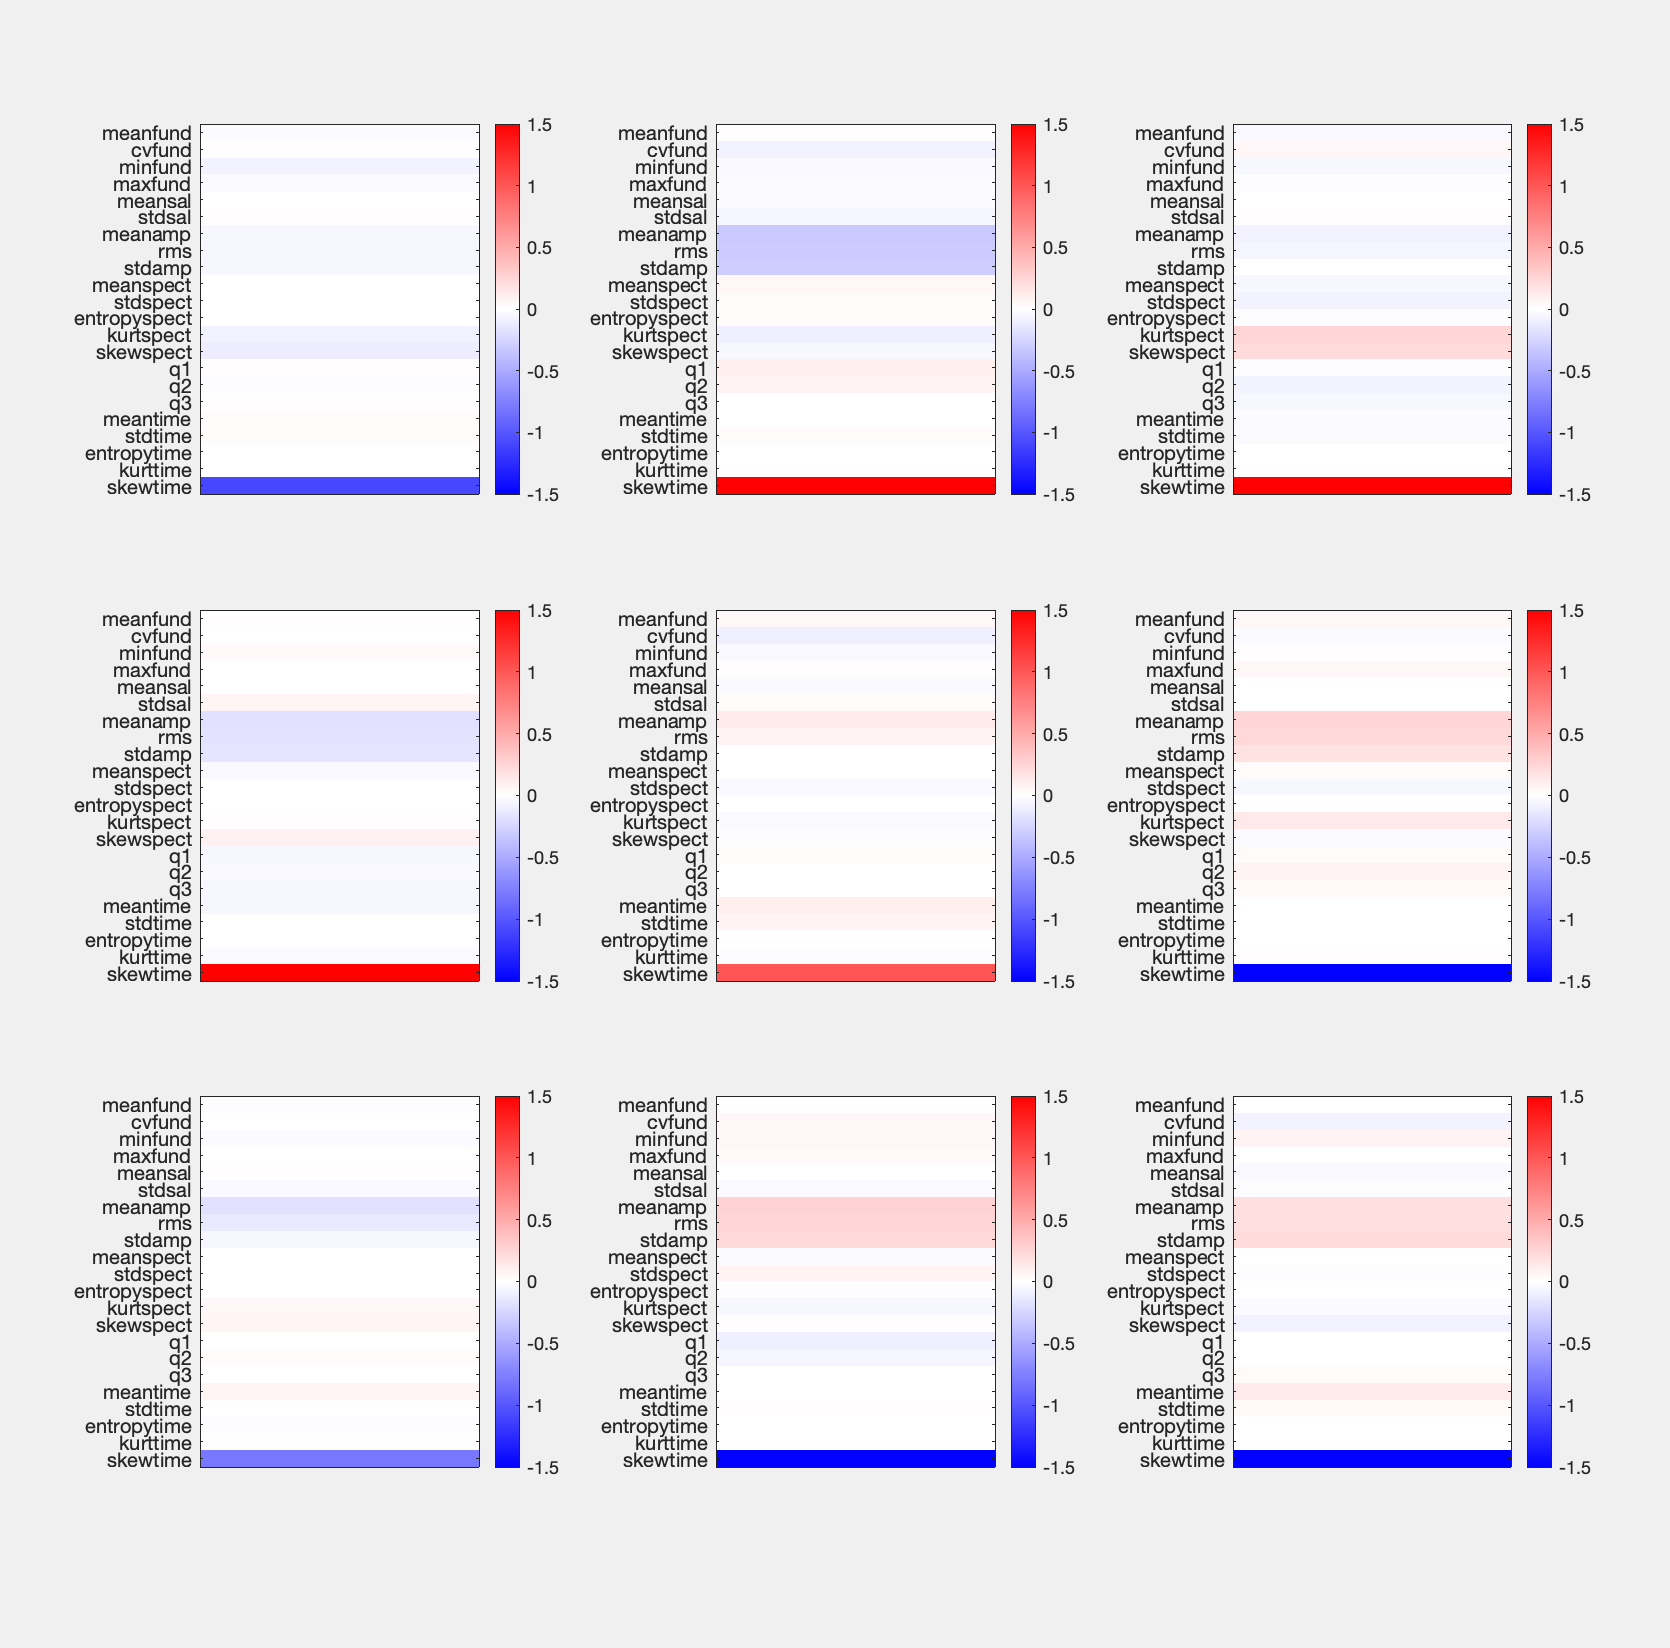

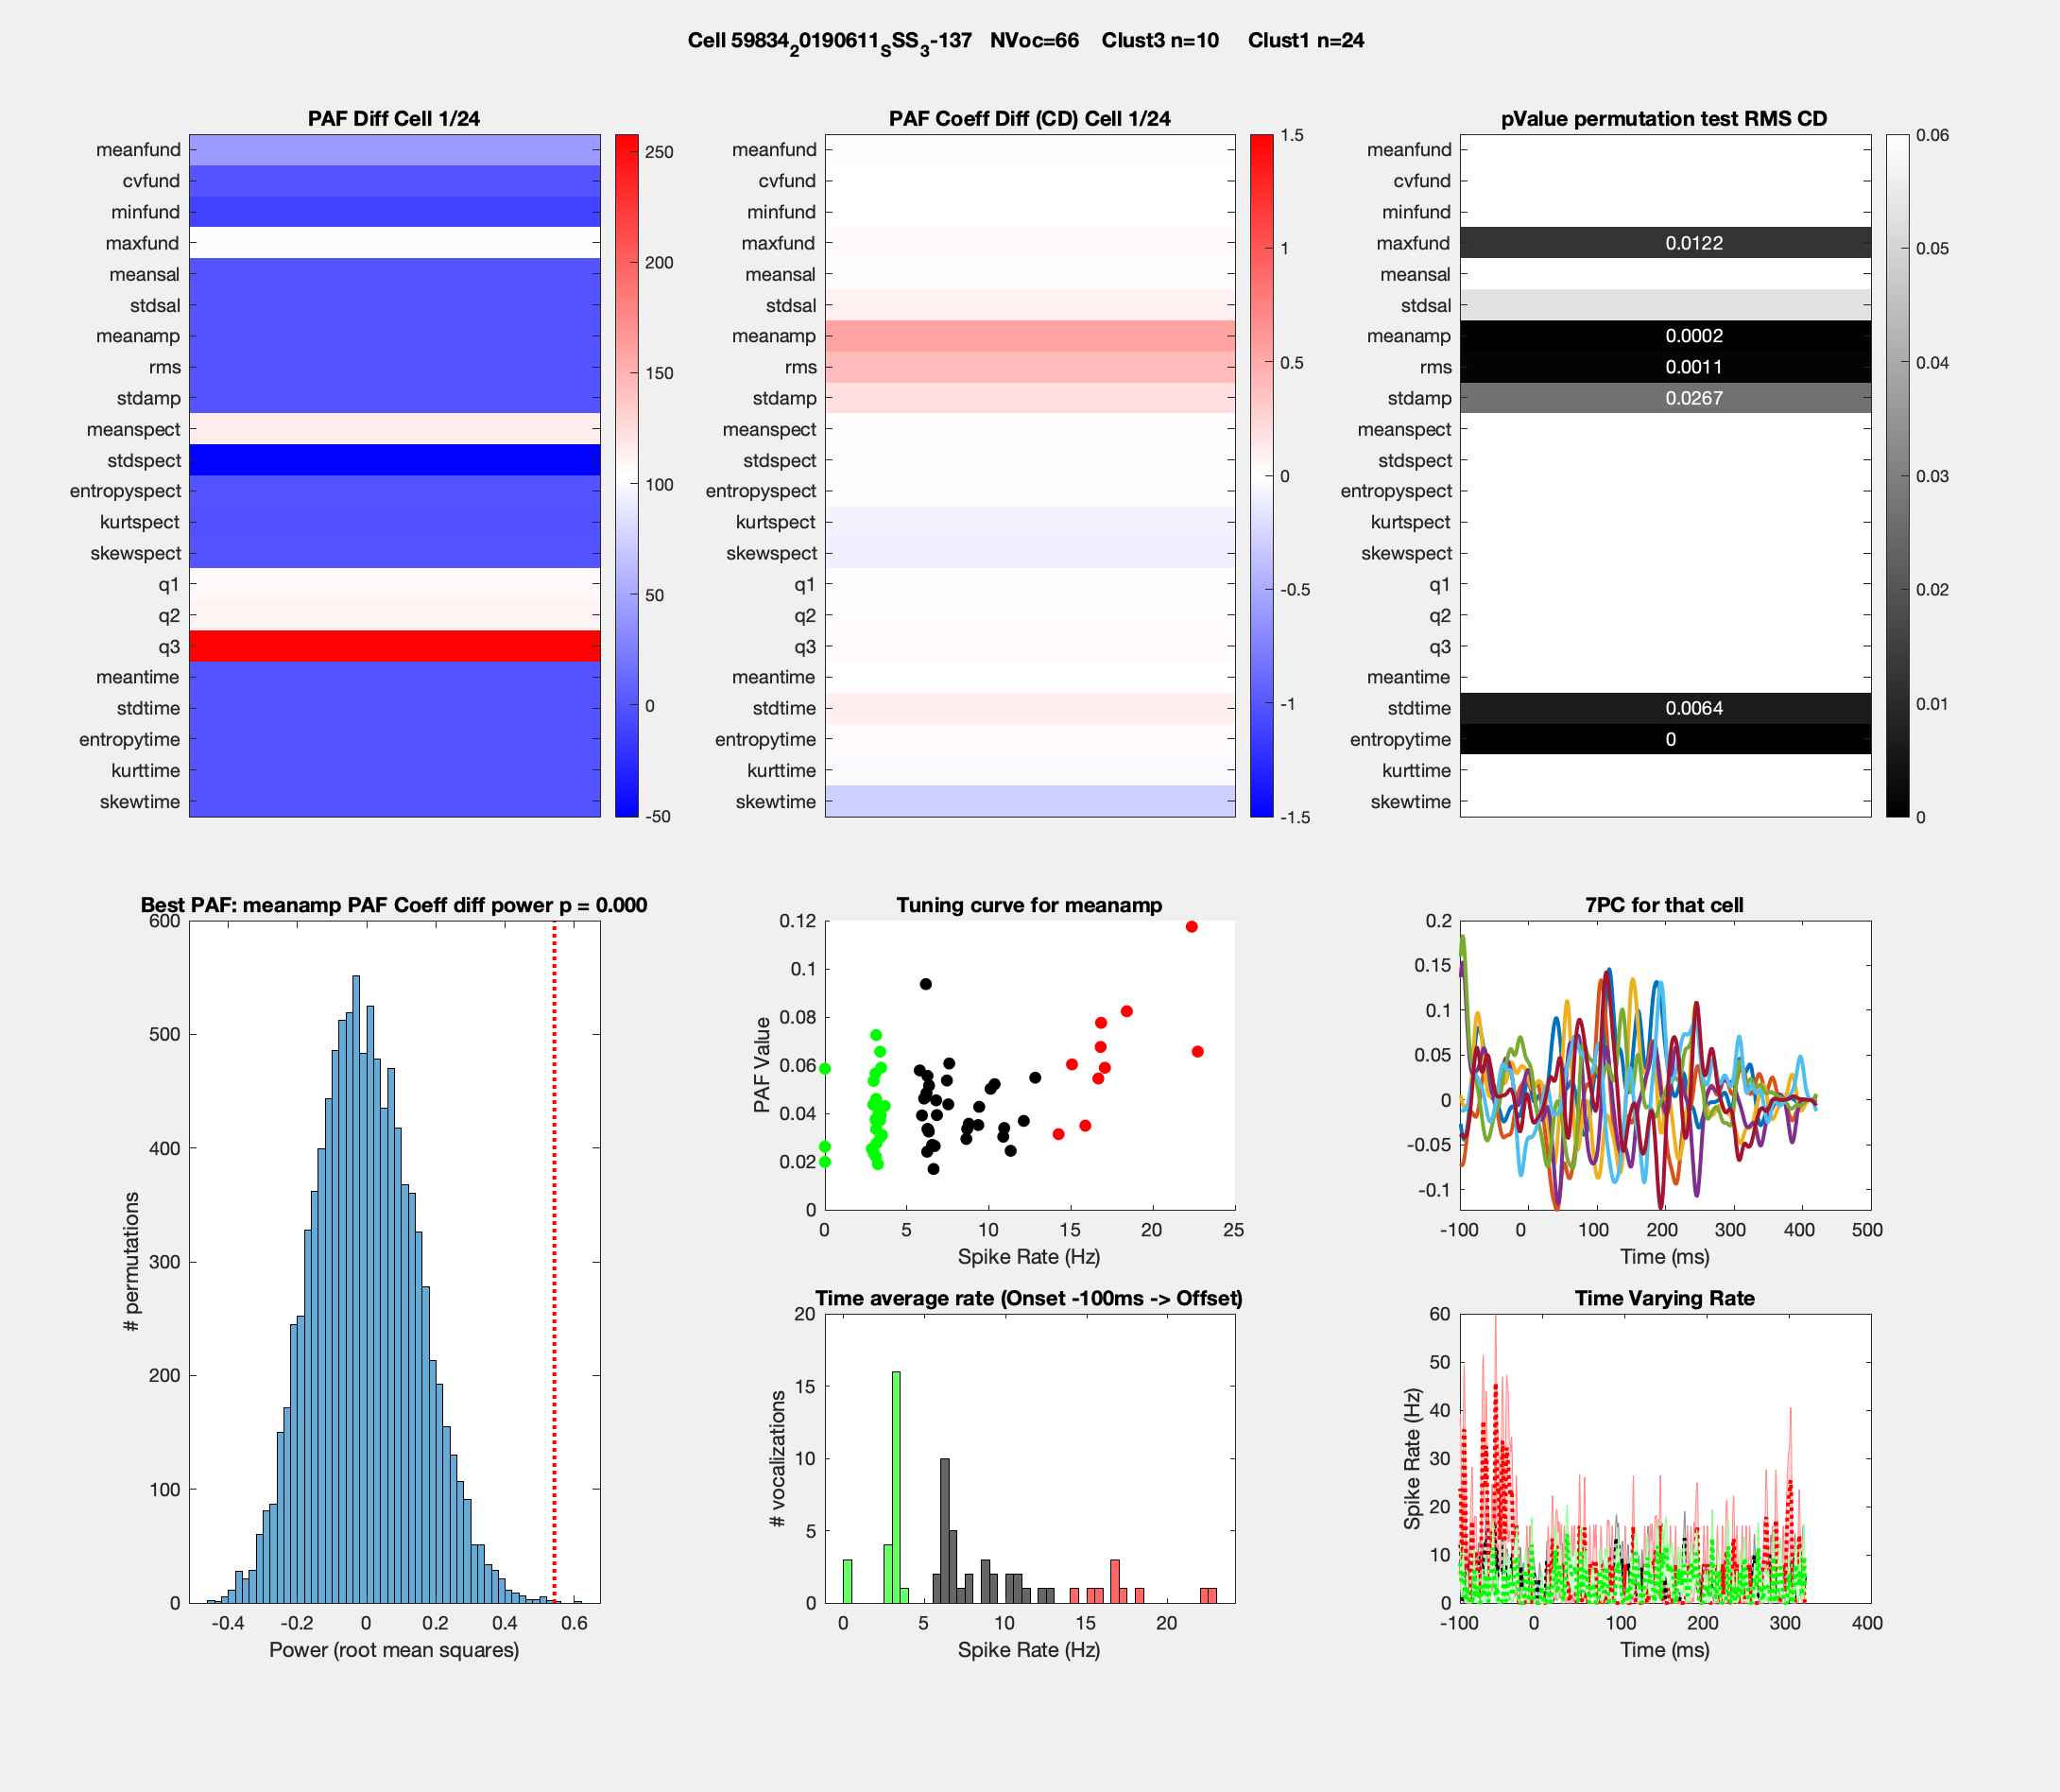

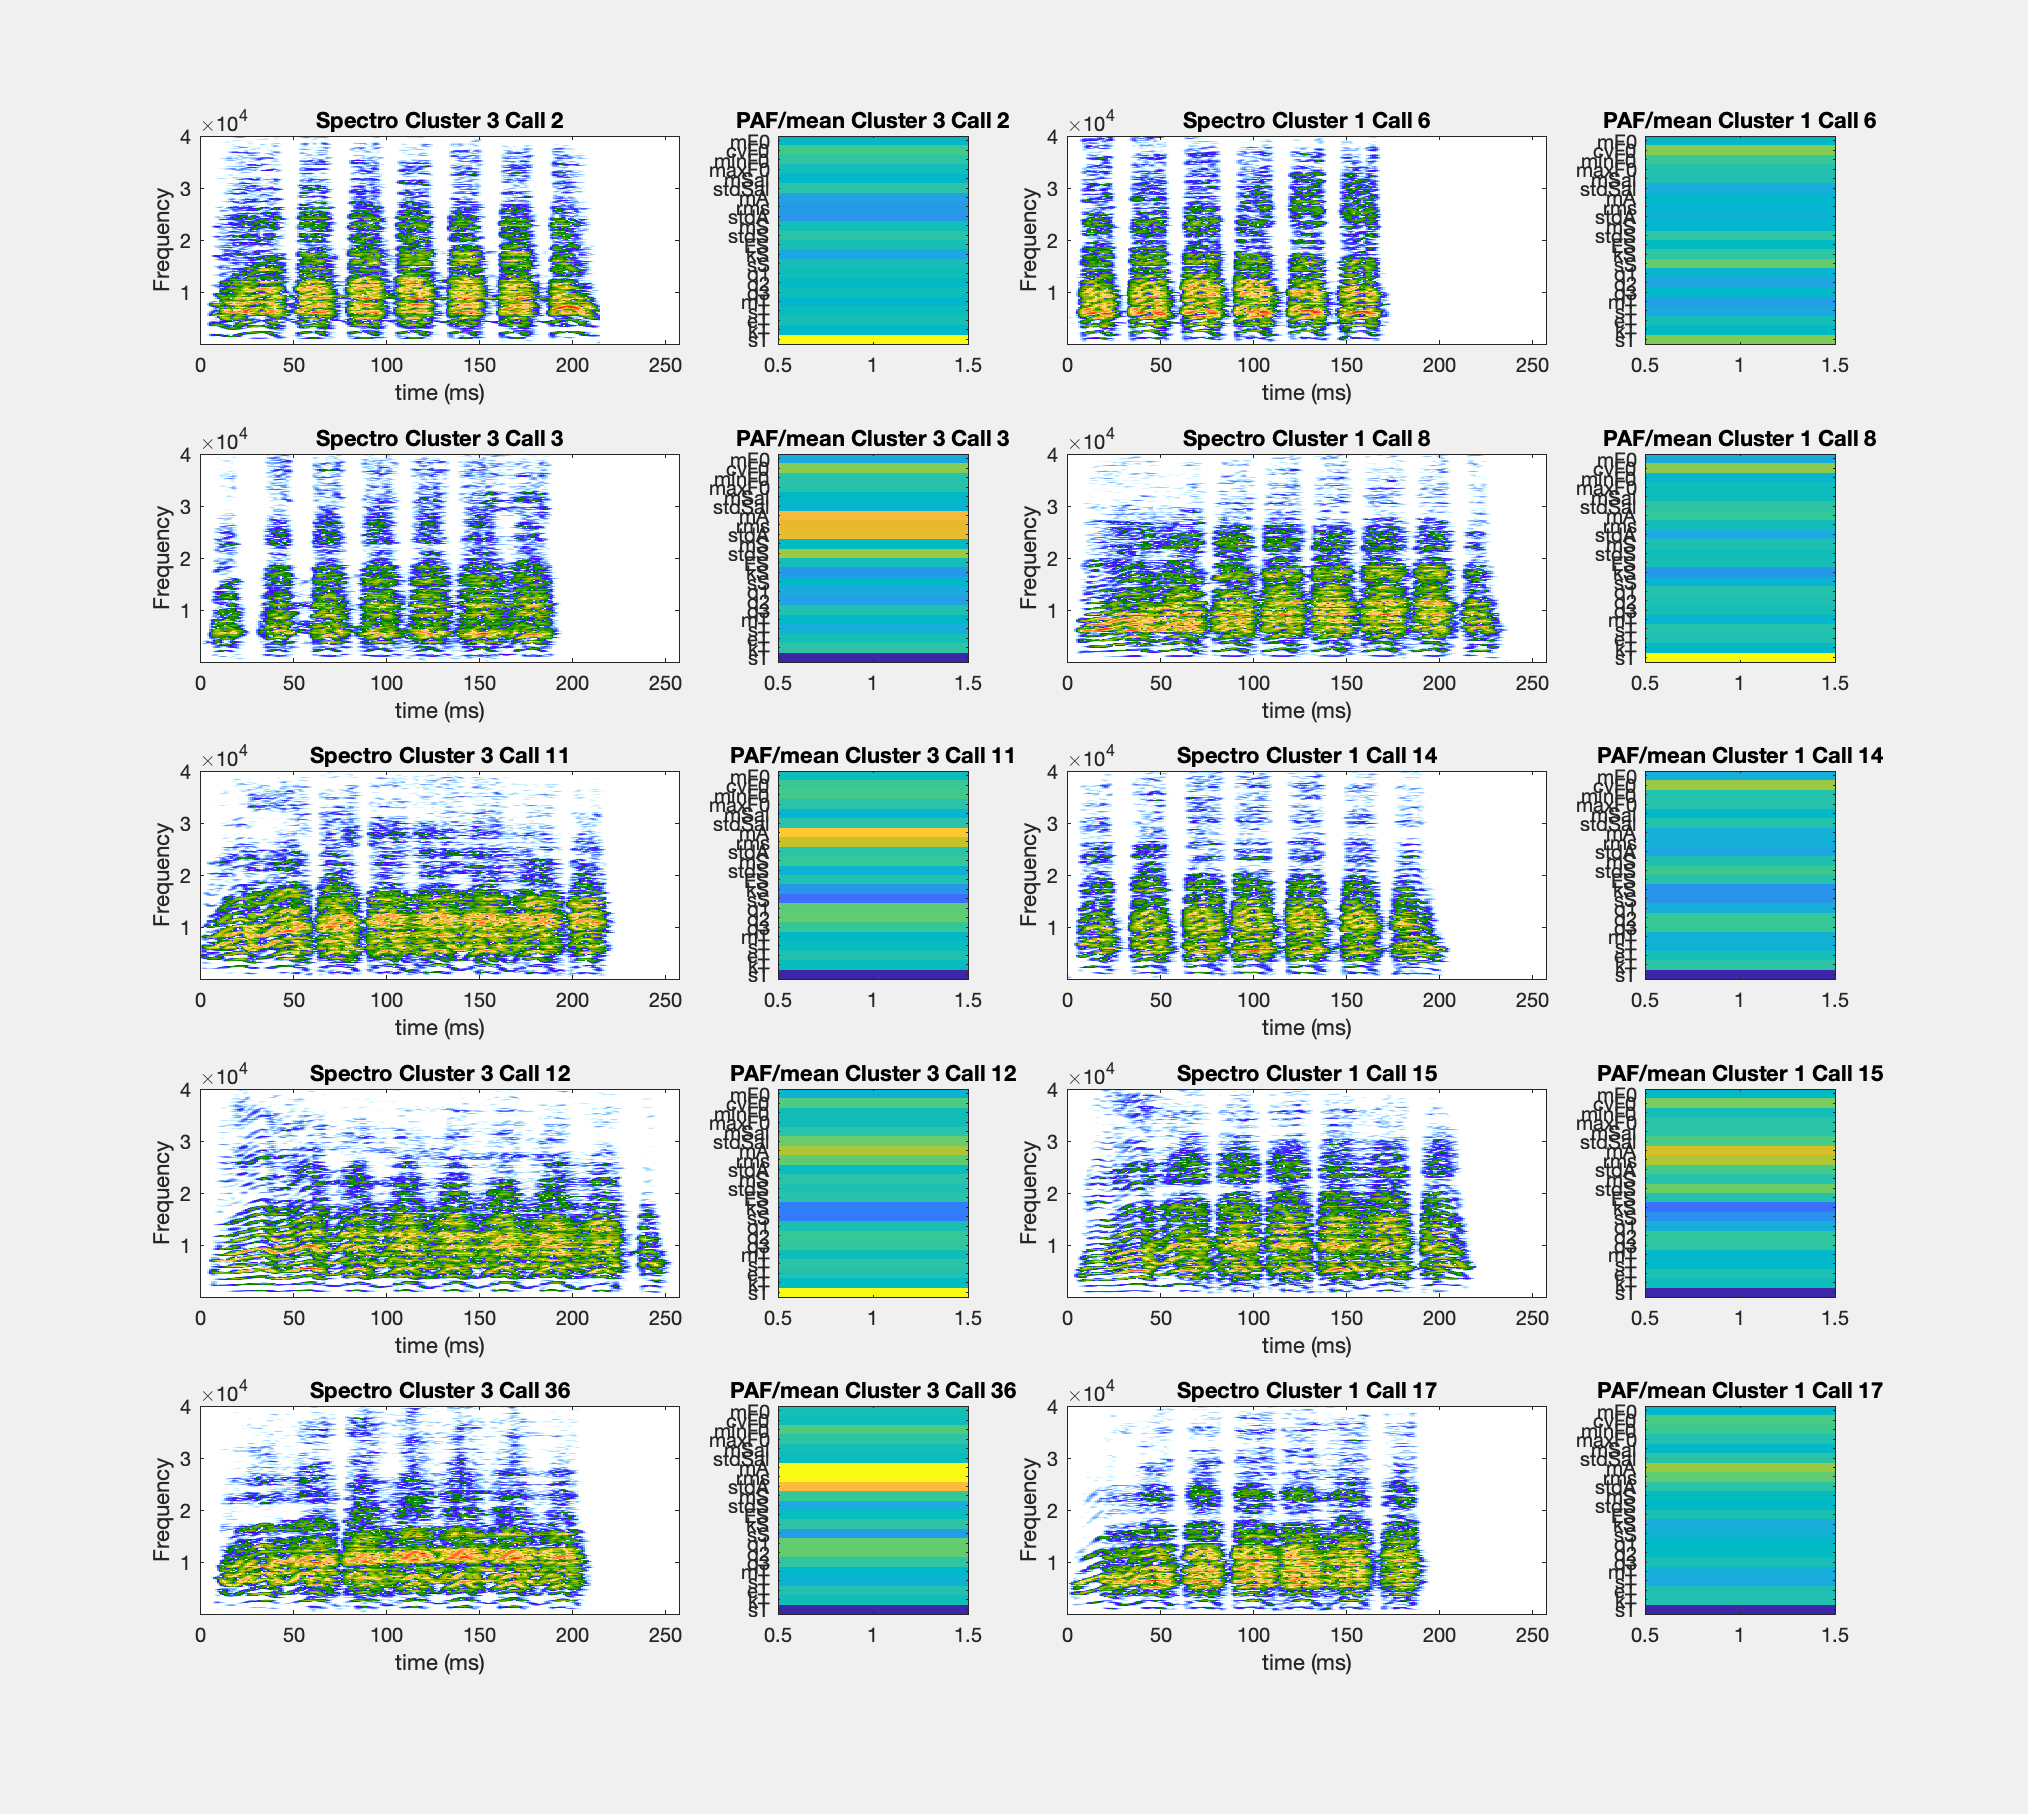

RecDevice = 'Mic'; %set as 'Mic' or 'Piezo', only for plot purposes of examples though!! Last run 07/09/2022
NBoot = 10000;
ClustNum = 4;
DBNoise = 50;
RateTrills_mat = [RateTrills{:}]';
CMAP = [[(1:128)'./128; ones(128,1)] [(1:128)'./128;flip((1:128)'./128)] [ones(128,1);flip((1:128)'./128)]];

% Load the spectrogram for plot purposes
if strcmp(RecDevice, 'Mic')
    load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_spectroMic.mat'), 'Trills_spectroMic','Trills_spectroMicto','Trills_spectroMicfo')
elseif strcmp(RecDevice, 'Piezo')
    load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_Ac.mat'), 'Trills_spectroPiezo','Trills_spectroPiezoto','Trills_spectroPiezofo')
end

% Load the PAF values for the stimuli of the cells investigated here
load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_Ac.mat'), 'PAF')

% load the average PAF features each vocalizer bat:
VocOperantID = {'11689', '59834'};
PAF_num = nan(1,length(VocOperantID));
for BB=1:length(VocOperantID)
    BatID = VocOperantID{BB};
    load(fullfile(Path2AllData,sprintf('%s_PAF.mat', BatID)), 'MeanPAF_T')
    MeanPAF.(sprintf('M%s',BatID)) = MeanPAF_T;
    PAF_num(BB) = length(MeanPAF_T);
end

PAFDiff = cell(NC,1);
PAFCoeffDiff = cell(NC,1);
PAFCoeffDiff_rand_all = cell(NC,1);% difference of the average stim values in the 2 clusters
PAFCoeffDiff_randRMS = cell(NC,1);% Average over the paired stim differences between random pairs of clusters
PAFCoeffDiff_RMS = nan(NC,max(PAF_num));% Average over the paired stim differences between 2 clusters
PAFCoeffDiff_RMSp = nan(NC,max(PAF_num));% probability of getting the value observed

PAFnames = fieldnames(PAF);

for cc=1:NC
    fprintf(1, 'File %d/%d\n', cc, NC)
    % find the extreme quartiles in Neural PC space + Z-scored Rate
    ZSRate = (MeanRateTrills{cc} - mean(MeanRateTrills{cc}))./std(MeanRateTrills{cc});
    Score_local = [ZSRate Score_per_cell{cc}(:,1:min(NPC_per_cell(cc), floor(NStims(cc)/10)))];
    [Idx, ClustMaxD] = find_extreme_clusters(Score_local, ClustNum, {'kmeans', 'RecursivePoint'});
    if isnan(Idx)
        [Idx, ClustMaxD] = find_extreme_clusters(Score_local, ClustNum, {'kmeans', 'RecursiveCluster'});
    end

    
    % Get the PAF for both clusters
    PAF_local = cell(length(ClustMaxD),1);
    for Clust = 1:length(ClustMaxD)
        PAF_Clust = cell(1,length(PAFnames));
        for ff=1:length(PAFnames)
            PAF_Clust{ff} = PAF.(PAFnames{ff}){cc}(Idx == ClustMaxD(Clust))'; % this should be a column vector
        end
        PAF_local{Clust} = [PAF_Clust{:}];
    end
    
    % Get the PAF for all stims for plot purposes
    PAF_Cell = nan(NStims(cc),length(PAFnames));
    for ff=1:length(PAFnames)
        PAF_Cell(:,ff) = PAF.(PAFnames{ff}){cc}'; % this should be a column vector
    end

    % Get the average PAF over all vocalizations for that Bat
    % Retrieve the name of the Vocalizer and the corresponding average
    % Trill PAF
    [~,Name]=fileparts(ListCellsVocTrill{cc});
    PAF_mean = MeanPAF.(sprintf('M%s',Name(1:5)));

    % Get the matrix of PAF difference between the 2 clusters for ploting
    % purposes
    PAFDiff{cc} = (mean(PAF_local{1},1, 'omitnan') - mean(PAF_local{2},1, 'omitnan'))';

    % Get the MPS coefficient difference between the 2 clusters for
    % plotting purposes
    PAFCoeffDiff{cc} = PAFDiff{cc} ./ PAF_mean;
    
    % Get the cell array of PAF coefficient pair differences between the 2
    % clusters for statistic purposes
    PAFCoeffDiff_perstim = nan(size(PAF_local{1},1),size(PAF_local{2},1), length(PAFnames));
    for Stim1=1:size(PAF_local{1},1)
        PAF1 = PAF_local{1}(Stim1,:)'./PAF_mean;
        for Stim2=1:size(PAF_local{2},1)
            PAF2 = PAF_local{2}(Stim2,:)'./PAF_mean;
            PAFCoeffDiff_perstim(Stim1, Stim2,:) = PAF1-PAF2;
        end
    end

     for ff=1:length(PAFnames)
        % for each PAF, take the average over the paired coeficient differences
        PAFCoeffDiff_RMS(cc,ff) = mean(reshape(PAFCoeffDiff_perstim(:,:,ff),[],1), 'omitnan');
     end
     NNanPAF = ~isnan(PAFCoeffDiff_RMS(cc,:)); % These are the non nan PAF

    % randomly sample groups of vocalizations, calculate distribution of MPSDiff
    PAFCoeffDiff_rand = nan(NBoot,length(PAFnames));% This matrix will contain all the CD (Coefficient of difference) of stim average values for each PAF in the case of random grouping of vocalizations
    PAFCoeffDiff_randRMS{cc} = nan(NBoot,length(PAFnames)); % This matrix will contain all the pair averaged CD (Coefficient of difference) values for each PAF in the case of random grouping of vocalizations
    F2 = figure(2);
    set(F2,'Visible','on')
    clf(F2)
    if cc==1
        % Stop to manually enlarge the figure as portrait
        keyboard
    end
    tiledlayout(3,3)
    for bb=1:NBoot
        Idx_rand = Idx(randperm(length(Idx)));
        % Get the average MPS for both clusters
        PAF_local = cell(length(ClustMaxD),1);
        for Clust = 1:length(ClustMaxD)
            PAF_Clust = cell(1,length(PAFnames));
            for ff=1:length(PAFnames)
                PAF_Clust{ff} = PAF.(PAFnames{ff}){cc}(Idx_rand == ClustMaxD(Clust))'; % this should be a column vector
            end
            PAF_local{Clust} = [PAF_Clust{:}];
        end

        % Get the PAF difference between the 2 clusters
        PAFDiff_rand = (mean(PAF_local{1},1, 'omitnan') - mean(PAF_local{2},1, 'omitnan'))';
        
        % Get the PAF coefficient difference between the 2 clusters
        PAFCoeffDiff_rand(bb,:) = (PAFDiff_rand ./ PAF_mean)';
        
        % Get the cell array of PAF coefficient pair differences between the 2
        % clusters for statistic purposes, and the threshold RMS for each
        % PAF for each pair of vocalizations
        PAFCoeffDiff_perstim_rand = nan(size(PAF_local{1},1),size(PAF_local{2},1),length(PAFnames));% This is the matrix
        for Stim1=1:size(PAF_local{1},1)
            PAF1 = PAF_local{1}(Stim1,:)'./PAF_mean;
            for Stim2=1:size(PAF_local{2},1)
                PAF2 = PAF_local{2}(Stim2,:)'./PAF_mean;
                PAFCoeffDiff_perstim_rand(Stim1, Stim2,:) = PAF1-PAF2;
            end
        end
        
        % for each PAF, take the average over the paired differences
        for ff=1:length(PAFnames)
            PAFCoeffDiff_randRMS{cc}(bb,ff) = mean(reshape(PAFCoeffDiff_perstim_rand(:,:,ff),[],1), 'omitnan');
        end

        % Plot some of the results of the bootstraps
        if (~rem(bb,NBoot/10)) && (bb<NBoot)
            NT = nexttile;
            imagesc(PAFCoeffDiff_randRMS{cc}(bb,NNanPAF)')
            colorbar()
            colormap(CMAP)
            set(gca, 'YTick', 1:length(PAFnames(NNanPAF)), 'YTickLabel', PAFnames(NNanPAF), 'XTickLabel', {},'XTick',[])
            caxis('manual');
            caxis([-1.5 1.5])
        end
    end
    PAFCoeffDiff_rand_all{cc} = PAFCoeffDiff_rand;
    
    % Calculate for each PAF the probability of getting the average value
    % we're getting in the observed data
    for ff=1:length(PAFnames)
        if isnan(PAFCoeffDiff_RMS(cc,ff))
            PAFCoeffDiff_RMSp(cc,ff) = nan;
        else
            PAFCoeffDiff_RMSp(cc,ff) = sum(PAFCoeffDiff_randRMS{cc}(:,ff)>=PAFCoeffDiff_RMS(cc,ff))/(NBoot- sum(isnan(PAFCoeffDiff_randRMS{cc}(:,ff)))); % substract the NaN values that would show up as non superior to the observed value;
        end
    end
    
    % plot the results of calculations for non-nan PAF
    F1 = figure(1);
    clf(F1)
    set(F1,'Visible','on')
    if cc==1
        % Stop to manually enlarge the figure as landscape
        keyboard
    end
    tiledlayout(4,3)
    nexttile([2,1])
    imagesc(PAFCoeffDiff_RMS(cc,NNanPAF)'.*PAF_mean(NNanPAF))
%     imagesc(PAFDiff{cc});
    colorbar()
    set(gca, 'YTick', 1:length(PAFnames(NNanPAF)), 'YTickLabel', PAFnames(NNanPAF), 'XTickLabel', {},'XTick',[])
    title(sprintf('PAF Diff Cell %d/%d', cc, NC))
    
    NT = nexttile([2,1]);
    imagesc(PAFCoeffDiff_RMS(cc,NNanPAF)');
    colorbar()
    colormap(CMAP)
    set(gca, 'YTick', 1:length(PAFnames(NNanPAF)), 'YTickLabel', PAFnames(NNanPAF), 'XTickLabel', {},'XTick',[])
    caxis([-1.5 1.5])
    title(sprintf('PAF Coeff Diff (CD) Cell %d/%d', cc, NC))
    
    
    NT = nexttile([2,1]);
    % plot the pvalue of each PAF for Power of
    % difference coefficient
    Im = imagesc(PAFCoeffDiff_RMSp(cc,NNanPAF)');
    colorbar()
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    set(gca, 'YTick', 1:length(PAFnames(NNanPAF)), 'YTickLabel', PAFnames(NNanPAF), 'XTickLabel', {},'XTick',[])
    title('pValue permutation test RMS CD')
    NNanPAFi = find(NNanPAF);
    for ff=1:length(NNanPAFi)
        if PAFCoeffDiff_RMSp(cc,NNanPAFi(ff))<0.05
            text(1,ff,num2str(PAFCoeffDiff_RMSp(cc,NNanPAFi(ff))),'Color', 'w')
        end
    end
    
    % Best ROI
    nexttile([2,1])
    [p_BestPAF,IndBestPAF] = min(PAFCoeffDiff_RMSp(cc,:));
    histogram(PAFCoeffDiff_randRMS{cc}(:,IndBestPAF)); hold on; V=vline(PAFCoeffDiff_RMS(cc,IndBestPAF));V.LineWidth = 2;hold off; xlabel('Power (root mean squares)'); ylabel('# permutations'); title(sprintf('Best PAF: %s PAF Coeff diff power p = %.3f', PAFnames{IndBestPAF}, p_BestPAF));
    
    % Plot the scatter of spike rate against values for the best PAF
    nexttile(8,[1,1])
    LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
    scatter(MeanRateTrills{cc}(LogicalOther), PAF_Cell(LogicalOther,IndBestPAF),40,'k', 'Filled')
    hold on
    scatter(MeanRateTrills{cc}(Idx == ClustMaxD(1)), PAF_Cell(Idx == ClustMaxD(1),IndBestPAF),40,'r', 'Filled')
    hold on
    scatter(MeanRateTrills{cc}(Idx == ClustMaxD(2)), PAF_Cell(Idx == ClustMaxD(2),IndBestPAF),40,'g', 'Filled')
    hold off; xlabel('Spike Rate (Hz)'); ylabel('PAF Value')
    title(sprintf('Tuning curve for %s', PAFnames{IndBestPAF}))
%     
%     % Plot the histogram of ZScored average spike rate used as input
%     nexttile(8,[1,1])
%     LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
%     histogram(ZSRate(LogicalOther), 'BinWidth',0.1, 'FaceColor', 'k');
%     hold on
%     histogram(ZSRate(Idx == ClustMaxD(1)), 'BinWidth',0.1, 'FaceColor', [1 0 0]);
%     hold on; 
%     histogram(ZSRate(Idx == ClustMaxD(2)), 'BinWidth',0.1, 'FaceColor', [0 1 0]);
%     hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations')
%     title('ZS Time average rate (Onset -100ms -> Offset)')

    % Plot the histogram of average spike rate
    nexttile(11,[1,1])
    LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
    histogram(MeanRateTrills{cc}(LogicalOther), 'BinWidth',0.5, 'FaceColor', 'k');
    hold on
    histogram(MeanRateTrills{cc}(Idx == ClustMaxD(1)), 'BinWidth',0.5, 'FaceColor', [1 0 0]);
    hold on; 
    histogram(MeanRateTrills{cc}(Idx == ClustMaxD(2)), 'BinWidth',0.5, 'FaceColor', [0 1 0]);
    hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations')
    title('Time average rate (Onset -100ms -> Offset)')
    

    % Plot the PC used for that Cell
    NPC_i = min(NPC_per_cell(cc), round(NStims(cc)/10));
    nexttile(9,[1,1])
    for pc=1:NPC_i
        plot(PC_per_cell{cc}(:,pc), 'LineWidth',2)
        hold on
    end
    hold off
    XTickLabel = get(gca, 'XTickLabel');
    XTickLabels=nan(length(XTickLabel),1);
    for ll=1:length(XTickLabel)
        XTickLabels(ll) = str2double(XTickLabel{ll});
    end
    set(gca, 'XTickLabel', XTickLabels-100)
    xlabel('Time (ms)')
    title(sprintf('%dPC for that cell', NPC_i))

    % Plot the average time varying rate for the 2 clusters
    nexttile(12,[1,1])
    % Find the rows in spike rate that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(cc)),:)*10^3; % Here we are plotting the rate in spike /seconds with a sampling rate of 1kHz
    % Plot
    if sum(LogicalOther)==1
        plot(RateTrills_mat_local(LogicalOther,:),':', 'Color','k', 'LineWidth',2);
    else
        shadedErrorBar([],mean(RateTrills_mat_local(LogicalOther,:),1), std(RateTrills_mat_local(LogicalOther,:))./(sum(LogicalOther))^0.5, {':', 'Color','k', 'LineWidth',2})
    end
    hold on
    for clust = 1:length(ClustMaxD)
        Col = zeros(1,3);
        Col(clust) = 1;
        if sum(Idx == ClustMaxD(clust))==1
            plot(RateTrills_mat_local(Idx == ClustMaxD(clust),:),':', 'Color',Col, 'LineWidth',2);
        else
            shadedErrorBar([],mean(RateTrills_mat_local(Idx == ClustMaxD(clust),:),1), std(RateTrills_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
        end
        hold on
    end
    title('Time Varying Rate')
    xlabel('Time (ms)')
    set(gca, 'XTickLabel', XTickLabels-100)
    xlabel('Time (ms)') 
    ylabel('Spike Rate (Hz)')
    hold off


    [~,Name] = fileparts(ListCellsVocTrill(cc));
    suplabel(sprintf('Cell %s   NVoc=%d    Clust%d n=%d     Clust%d n=%d ', Name, length(Idx),ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))),'t');
    


    % Plot 5 examplars of calls belonging to each cluster in the
    % spectrogram and PAF spaces
    Idx1 = find(Idx == ClustMaxD(1));
    Idx2 = find(Idx == ClustMaxD(2));
    Ord1 = 1:length(Idx1);
    Ord2 = 1:length(Idx2);
    F3 = figure(3);
    
    if strcmp(RecDevice, 'Mic')
        [~, nTimes]=cellfun(@size, Trills_spectroMic{cc}, 'UniformOutput', false);
        f_low = 100;
        f_high = 40000;
    elseif strcmp(RecDevice, 'Piezo')
        [~, nTimes]=cellfun(@size, Trills_spectroPiezo{cc}, 'UniformOutput', false);
        f_low = 100;
        f_high = 10000;
    end
    nTimes = [nTimes{:}];
    t_max = max([nTimes(Idx1(1:min(5, length(Idx1)))) nTimes(Idx2(1:min(5, length(Idx2))))]);
    clf(F3)
    set(F3,'Visible','on')
    if cc==1
        % Stop to manually enlarge the figure as portrait
        keyboard
    end
    tiledlayout(5,6)
    PAFnamesShort = {'mF0', 'cvF0','minF0', 'maxF0', 'mSal', 'stdSal','mA', 'rms','stdA','mS','stdS','ES','kS','sS','q1','q2','q3','mT', 'sT','eT','kT','sT'};
    PlotInd = 1:6:30;
    for ii=1:5
        if ii<=length(Idx1)
            nexttile(PlotInd(ii),[1,2])
            %spectro CLust1
            if strcmp(RecDevice, 'Mic')
                plot_spectro(Trills_spectroMic{cc}{Idx1(Ord1(ii))},DBNoise, Trills_spectroMicto{cc}{Idx1(Ord1(ii))}, Trills_spectroMicfo{cc}{Idx1(Ord1(ii))}, f_low, f_high,t_max)
            elseif strcmp(RecDevice, 'Piezo')
                plot_spectro(Trills_spectroPiezo{cc}{Idx1(Ord1(ii))},DBNoise, Trills_spectroPiezoto{cc}{Idx1(Ord1(ii))}, Trills_spectroPiezofo{cc}{Idx1(Ord1(ii))}, f_low, f_high,t_max)
            end
            title(sprintf('Spectro Cluster %d Call %d',ClustMaxD(1),Idx1(Ord1(ii))))

            nexttile(PlotInd(ii)+2,[1,1])
            %PAF Clust1
            imagesc(PAF_Cell(Idx1(Ord1(ii)),NNanPAF)'./PAF_mean(NNanPAF))
%             colorbar()
            set(gca, 'YTick', 1:length(PAFnames(NNanPAF)), 'YTickLabel', PAFnamesShort(NNanPAF))
            caxis([0 2])
            title(sprintf('PAF/mean Cluster %d Call %d',ClustMaxD(1),Idx1(Ord1(ii))))
        end

        if ii<=length(Idx2)
            nexttile(PlotInd(ii)+3,[1,2])
            %spectro CLust2
            if strcmp(RecDevice, 'Mic')
                plot_spectro(Trills_spectroMic{cc}{Idx2(Ord2(ii))},DBNoise, Trills_spectroMicto{cc}{Idx2(Ord2(ii))}, Trills_spectroMicfo{cc}{Idx2(Ord2(ii))}, f_low, f_high, t_max)
            elseif strcmp(RecDevice, 'Piezo')
                plot_spectro(Trills_spectroPiezo{cc}{Idx2(Ord2(ii))},DBNoise, Trills_spectroPiezoto{cc}{Idx2(Ord2(ii))}, Trills_spectroPiezofo{cc}{Idx2(Ord2(ii))}, f_low, f_high, t_max)
            end
            title(sprintf('Spectro Cluster %d Call %d',ClustMaxD(2),Idx2(Ord2(ii))))

            nexttile(PlotInd(ii)+5,[1,1])
            %mps Clust2
            imagesc(PAF_Cell(Idx2(Ord2(ii)),NNanPAF)'./PAF_mean(NNanPAF))
%             colorbar()
            set(gca, 'YTick', 1:length(PAFnames(NNanPAF)), 'YTickLabel', PAFnamesShort(NNanPAF))
            caxis([0 2])
            title(sprintf('PAF/mean Cluster %d Call %d',ClustMaxD(2),Idx2(Ord2(ii))))
        end
    end
%     pause()
    drawnow
%    if any((PAFCoeffDiff_RMSp(cc,:))<0.06)
        orient(F1,'landscape')
        print(F1,fullfile(Path2AllData,sprintf('PCARateNeuralDistTrills_PAF_%s.pdf', Name)),'-dpdf','-fillpage')
        orient(F2,'portrait')
        print(F2,fullfile(Path2AllData,sprintf('PCARateNeuralDistTrills_PAF_%s_Bootstrap.pdf', Name)),'-dpdf','-fillpage')
        orient(F3,'portrait')
        print(F3,fullfile(Path2AllData,sprintf('PCARateNeuralDistTrills_PAF_%s_VocExamples.pdf', Name)),'-dpdf','-fillpage')
%     end
end

PAFDistRes.PAFDiff = PAFDiff;
PAFDistRes.PAFCoeffDiff=PAFCoeffDiff;
PAFDistRes.PAFCoeffDiff_rand_all=PAFCoeffDiff_rand_all;
PAFDistRes.PAFCoeffDiff_randRMS=PAFCoeffDiff_randRMS;
PAFDistRes.PAFCoeffDiff_RMS=PAFCoeffDiff_RMS;
PAFDistRes.PAFCoeffDiff_RMSp=PAFCoeffDiff_RMSp;
PAFDistRes.PAFnames=PAFnames;
save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'PAFDistRes','-append');

Calculate True p-value with FDR correction accross all tests 

load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'PAFDistRes', 'MPSMicDistRes', 'MPSPiezoDistRes')
% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank)) per acoustic feature
All_p = [PAFDistRes.PAFCoeffDiff_RMSp MPSMicDistRes.MPSCoeffDiff_Trills_RMSp MPSPiezoDistRes.MPSCoeffDiff_Trills_RMSp];
All_p_FDRC = nan(size(All_p));
for ac=1:size(All_p,2)
    [~,P_vec_rank] = sort(All_p(:,ac), 'ascend');
    P_vec_rank(P_vec_rank == size(All_p,1)) = size(All_p,1)-1; 
    All_p_FDRC(:,ac) = All_p(:,ac) .* (size(All_p,1)-P_vec_rank);
end
All_p_FDRC(isnan(All_p_FDRC))=1;
%% Below is FDR correction accross all comparisons (could be too stringent...)
% All_p_vec = reshape(All_p, numel(All_p),1);
% [~,All_p_vec_rank] = sort(All_p_vec, 'ascend');
% All_p_vec_rank(All_p_vec_rank == length(All_p_vec)) = length(All_p_vec)-1; 
% All_p_FDRC = reshape(All_p_vec .* (length(All_p_vec)-All_p_vec_rank), size(All_p));

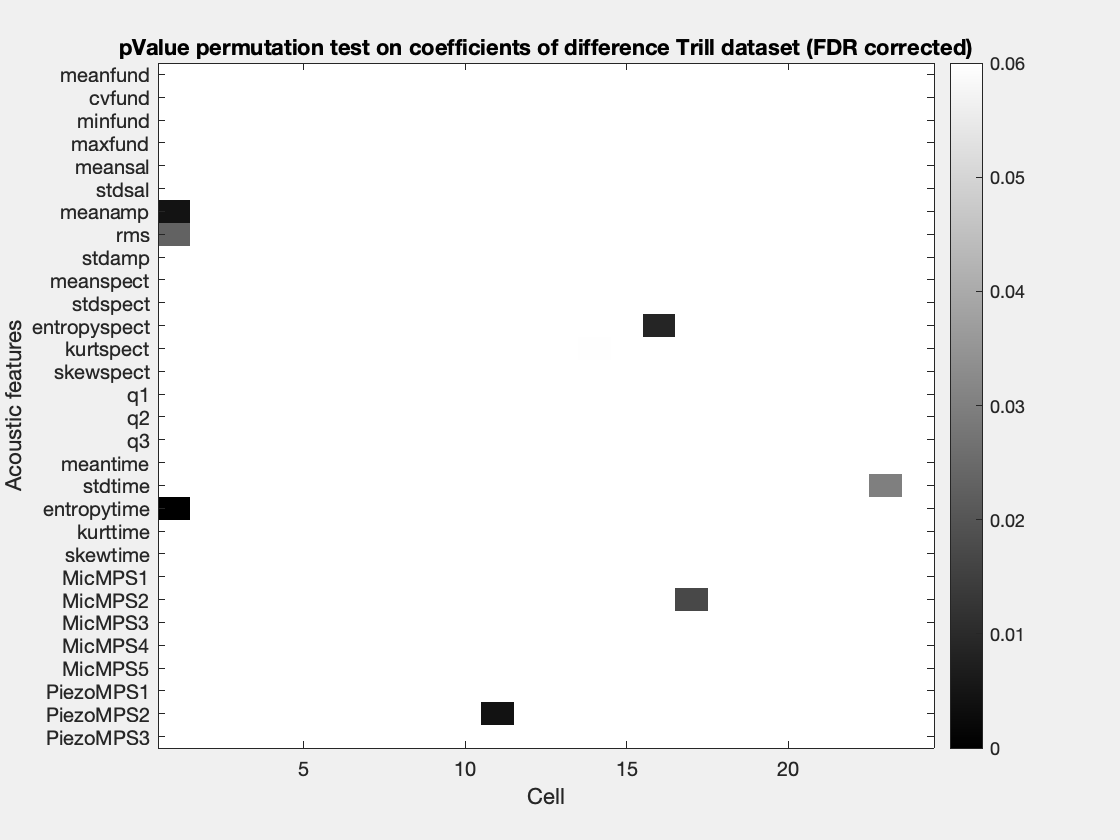

F4=figure(4);
clf(F4)
set(F4,'Visible','on')
Im = imagesc(All_p_FDRC');
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
MicMPSROI = cell(size(MPSMicDistRes.MPSCoeffDiff_Trills_RMSp,2),1);
for rr = 1:size(MPSMicDistRes.MPSCoeffDiff_Trills_RMSp,2)
    MicMPSROI{rr} = sprintf('MicMPS%d',rr);
end
PiezoMPSROI = cell(size(MPSPiezoDistRes.MPSCoeffDiff_Trills_RMSp,2),1);
for rr = 1:size(MPSPiezoDistRes.MPSCoeffDiff_Trills_RMSp,2)
    PiezoMPSROI{rr} = sprintf('PiezoMPS%d',rr);
end
set(gca, 'YTick', 1:(length(PAFDistRes.PAFnames) + length(MicMPSROI) + length(PiezoMPSROI)), 'YTickLabel',   [PAFDistRes.PAFnames; MicMPSROI; PiezoMPSROI])
ylabel('Acoustic features')
xlabel('Cell')
title('pValue permutation test on coefficients of difference Trill dataset (FDR corrected)')

Plot the results fro the approach with extreme cluster and congruence of distance matrices (Mantel test)

if strcmp(RecDevice, 'Mic')
    figure();
    subplot(1,5,1);
    PlotDat1 = MPSCoeffDiff_Trills_RMSp;
    PlotDat1(isnan(PlotDat1))=0.06;
    Im1 = imagesc(PlotDat1);
    colorbar();
    colormap(Im1.Parent,'gray')
    Im1.Parent.CLim = [0 0.06];
    title('MPS Coeff Diff extreme clusters permutation test');
    subplot(1,5,2);
    PlotDat2 = Mantel_mps_PCAper_cell_pval;
    PlotDat2(isnan(PlotDat2)) = 0.06;
    Im2=imagesc(PlotDat2); 
    colorbar();
    colormap(Im2.Parent,'gray')
    Im2.Parent.CLim = [0 0.06];
    title('MPS Mantel test with PCA per cell')
    subplot(1,5,3);
    PlotDat3 = Mantel_mps_PCApop_pval;
    PlotDat3(isnan(PlotDat3)) = 0.06;
    Im2=imagesc(PlotDat3); 
    colorbar();
    colormap(Im2.Parent,'gray')
    Im2.Parent.CLim = [0 0.06];
    title('MPS Mantel test with PCA population')
    subplot(1,5,4);
    PlotDat4 = Mantel_mps_ZSRate_pval;
    PlotDat4(isnan(PlotDat4)) = 0.06;
    Im2=imagesc(PlotDat4); 
    colorbar();
    colormap(Im2.Parent,'gray')
    Im2.Parent.CLim = [0 0.06];
    title('MPS Mantel test with ZSRate')
    subplot(1,5,5);
    PlotDat5 = Mantel_mps_ZSRatePCAper_cell_pval;
    PlotDat5(isnan(PlotDat5)) = 0.06;
    Im2=imagesc(PlotDat5); 
    colorbar();
    colormap(Im2.Parent,'gray')
    Im2.Parent.CLim = [0 0.06];
    title('MPS Mantel test with ZSRate + PCA per Cell')

elseif strcmp(RecDevice, 'Piezo')
    figure();
    subplot(1,5,1);
    PlotDat = MPSCoeffDiff_Trills_RMSp;
    PlotDat(isnan(PlotDat)) = 0.06;
    Im1 = imagesc(PlotDat);
    colorbar();
    colormap(Im1.Parent,'gray')
    Im1.Parent.CLim = [0 0.06];
    title('MPS Coeff Diff extreme clusters permutation test');
    subplot(1,5,2);
    PlotDat2 = Mantel_mpsPiezo_PCAper_cell_pval;
    PlotDat2(isnan(PlotDat2)) = 0.06;
    Im2=imagesc(PlotDat2); 
    colorbar();
    colormap(Im2.Parent,'gray')
    Im2.Parent.CLim = [0 0.06];
    title('MPS Mantel test with PCA per cell')
    subplot(1,5,3);
    PlotDat3 = Mantel_mpsPiezo_PCApop_pval;
    PlotDat3(isnan(PlotDat3))=0.06;
    Im2=imagesc(PlotDat3); 
    colorbar();
    colormap(Im2.Parent,'gray')
    Im2.Parent.CLim = [0 0.06];
    title('MPS Mantel test with PCA population')
    subplot(1,5,4);
    PlotDat4 = Mantel_mpsPiezo_ZSRate_pval;
    PlotDat4(isnan(PlotDat4)) = 0.06;
    Im2=imagesc(PlotDat4); 
    colorbar();
    colormap(Im2.Parent,'gray')
    Im2.Parent.CLim = [0 0.06];
    title('MPS Mantel test with ZSRate')
    subplot(1,5,5);
    PlotDat5 = Mantel_mpsPiezo_ZSRatePCAper_cell_pval;
    PlotDat5(isnan(PlotDat5)) = 0.06;
    Im2=imagesc(PlotDat5); 
    colorbar();
    colormap(Im2.Parent,'gray')
    Im2.Parent.CLim = [0 0.06];
    title('MPS Mantel test with ZSRate + PCA per Cell')
end

if strcmp(RecDevice, 'Mic')
    save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'),'MPSCoeffDiff_Trills_RMS','MPSCoeffDiff_Trills_RMSp', '-append')
elseif strcmp(RecDevice, 'Piezo')
    MPSPiezoCoeffDiff_Trills_RMS = MPSCoeffDiff_Trills_RMS;
    MPSPiezoCoeffDiff_Trills_RMSp = MPSCoeffDiff_Trills_RMSp;
    save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'),'MPSPiezoCoeffDiff_Trills_RMS','MPSPiezoCoeffDiff_Trills_RMSp', '-append')
else
    error('Nothing was saved RecDevice not defined properly')
end


## Analysis using mantel test on distance matrices in the acoustic space

That was not working very well :-\ Probably not enough data?

Trills_fund_mat = [Trills_fund{:}]';
Trills_sal_mat = [Trills_sal{:}]';
Trills_amp_mat = [Trills_amp{:}]';
Trills_specMean_mat = [Trills_specMean{:}]';
Trills_formDisp_mat = [Trills_formDisp{:}]';
Trills_mps_mat = [Trills_mps{:}];
Trills_mps_mat = [Trills_mps_mat{:}]';
Trills_mpsPiezo_mat = [Trills_mpsPiezo{:}];
Trills_mpsPiezo_mat = [Trills_mpsPiezo_mat{:}]';

% replace nan values by 0
Trills_fund_mat(isnan(Trills_fund_mat)) = 0;
Trills_sal_mat(isnan(Trills_sal_mat)) = 0;
Trills_amp_mat(isnan(Trills_amp_mat)) = 0;
Trills_specMean_mat(isnan(Trills_specMean_mat)) = 0;
Trills_formDisp_mat(isnan(Trills_formDisp_mat)) = 0;
% there should not be any nan values in mps
if any(isnan(Trills_mps_mat))
    return
end

% substract the time varying mean
Trills_fund_centered = Trills_fund_mat - mean(Trills_fund_mat);
Trills_sal_centered = Trills_sal_mat - mean(Trills_sal_mat);
Trills_amp_centered = Trills_amp_mat - mean(Trills_amp_mat);
Trills_specMean_centered = Trills_specMean_mat - mean(Trills_specMean_mat);
Trills_formDisp_centered = Trills_formDisp_mat - mean(Trills_formDisp_mat);
Trills_mps_centered = Trills_mps_mat - mean(Trills_mps_mat);

% Calculate independant PCA for each (by default pca center the data)
[PC_fund,Score_fund,~, ~, VarExpl_fund,~] = pca(Trills_fund_mat);
[PC_sal,Score_sal,~, ~, VarExpl_sal,~] = pca(Trills_sal_mat);
[PC_amp,Score_amp,~, ~, VarExpl_amp,~] = pca(Trills_amp_mat);
[PC_specMean,Score_specMean,~, ~, VarExpl_specMean,~] = pca(Trills_specMean_mat);
[PC_formDisp,Score_formDisp,~, ~, VarExpl_formDisp,~] = pca(Trills_formDisp_mat);
% [PC_mps,Score_mps,~, ~, VarExpl_mps,~] = pca(Trills_mps_mat);



% Plot the variance explained
PercVar = 80;
t = tiledlayout(3,2,'TileSpacing','Compact');
nexttile
plot(cumsum(VarExpl_amp), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_amp)>PercVar,1), '-k',sprintf('%d%% at n=%dPC', PercVar,find(cumsum(VarExpl_amp)>PercVar,1)))
hold off
title('Amplitude')

nexttile
plot(cumsum(VarExpl_fund), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_fund)>PercVar,1), '-k',sprintf('%d%% at n=%dPC', PercVar,find(cumsum(VarExpl_fund)>PercVar,1)))
hold off
title('Fundamental')

nexttile
plot(cumsum(VarExpl_sal), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_sal)>PercVar,1), '-k',sprintf('%d%% at n=%dPC', PercVar,find(cumsum(VarExpl_sal)>PercVar,1)))
hold off
title('Saliency')

nexttile
plot(cumsum(VarExpl_formDisp), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_formDisp)>PercVar,1), '-k',sprintf('%d%% at n=%dPC',PercVar, find(cumsum(VarExpl_formDisp)>PercVar,1)))
hold off
title('Formant Dispersion')

nexttile
plot(cumsum(VarExpl_specMean), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_specMean)>PercVar,1), '-k',sprintf('%d%% at n=%dPC',PercVar, find(cumsum(VarExpl_specMean)>PercVar,1)))
hold off
title('Spectral Mean')

% nexttile
% plot(cumsum(VarExpl_mps), 'LineWidth',2)
% xlabel('# PC dimensions')
% ylabel('% variance explained')
% hold on
% vline(find(cumsum(VarExpl_mps)>95,1), '-k',sprintf('%d%% at n=%dPC',95, find(cumsum(VarExpl_mps)>95,1)))
% hold off
% title('MPS')

% Plot the first PC shapes
t = tiledlayout(3,2,'TileSpacing','Compact');

nexttile
NPC_amp = find(cumsum(VarExpl_amp)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_amp 
    plot(PC_amp(:,ii), 'LineWidth',2,'DisplayName', sprintf('PC%d',ii));
    hold on
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill amplitude')
hold off

nexttile
NPC_fund = find(cumsum(VarExpl_fund)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_fund 
    plot(PC_fund(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill fundamental')
hold off

nexttile
NPC_sal = find(cumsum(VarExpl_sal)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_sal 
    plot(PC_sal(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill saliency')
hold off

nexttile
NPC_formDisp = find(cumsum(VarExpl_formDisp)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_formDisp 
    plot(PC_formDisp(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill formant dispersion')
hold off

nexttile
NPC_specMean = find(cumsum(VarExpl_specMean)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_specMean 
    plot(PC_specMean(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax)));xticklabels(0:100:max(StimDuraMax));
title('PCA basis set of Trill spectral Mean')
hold off

% figure
% tiledlayout(2,2)
% nexttile
% MPS_PC1 = reshape(PC_mps(:,1),length(Trills_wf2), length(Trills_wt));
% plot_mps(MPS_PC1, Trills_wf2, Trills_wt, 50,0);
% title(' PC1 MPS for Trills')
% 
% nexttile
% MPS_PC2 = reshape(PC_mps(:,2),length(Trills_wf2), length(Trills_wt));
% plot_mps(MPS_PC1, Trills_wf2, Trills_wt,50,0);
% title(' PC2 MPS for Trills')
% 
% nexttile
% MPS_PC3 = reshape(PC_mps(:,3),length(Trills_wf2), length(Trills_wt));
% plot_mps(MPS_PC3, Trills_wf2, Trills_wt,50,0);
% title(' PC3 MPS for Trills')

% for pp = 1:20
%     figure()
%     MPS_PCpp = reshape(PC_mps(:,pp),length(Trills_wf2), length(Trills_wt));
%     plot_mps(MPS_PCpp, Trills_wf2, Trills_wt,50,0)
%     title(sprintf(' PC%d MPS for Trills', pp))
% end

% plot all vocalizations in the first PC dimension of each acoustic feature
t = tiledlayout(2,2,'TileSpacing','Compact');
nexttile
scatter(Score_amp(:,1),Score_fund(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 fundamental')

nexttile
scatter(Score_amp(:,1),Score_sal(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 saliency')

nexttile
scatter(Score_amp(:,1),Score_formDisp(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 formant dispersion')

nexttile
scatter(Score_amp(:,1),Score_specMean(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 spectral mean')

% we can observe that formant dispersion has some outsider that might drive
% the pca weirdly...

t = tiledlayout(1,1);
% Obtain the matrix of acoustic distance for each cell for each PAF and
% PCScore on PAF
% retrieve for each cell the instance that was used as a reference for neural distances
AcousticVectorDistance = cell(NC,1);
AcousticMatrixDistance = cell(NC,1);
AcousticMatrixDistance_amp = cell(NC,1);
AcousticMatrixDistance_fund = cell(NC,1);
AcousticMatrixDistance_sal = cell(NC,1);
AcousticMatrixDistance_specMean = cell(NC,1);
AcousticMatrixDistance_formDisp = cell(NC,1);
for cc=1:NC
    % Find the rows in Score that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    Score_local = [Score_amp(Row1(end)+(1:NStims(cc)),1:NPC_amp) Score_fund(Row1(end)+(1:NStims(cc)),1:NPC_fund) Score_sal(Row1(end)+(1:NStims(cc)),1:NPC_sal) Score_formDisp(Row1(end)+(1:NStims(cc)),1:NPC_formDisp) Score_specMean(Row1(end)+(1:NStims(cc)),1:NPC_specMean)];
    % Calculate euclidean distance between pairs of vocalizations in PCA
    % space
    D = squareform(pdist(Score_local, 'seuclidean'));
    % Find the observation that we used as a reference to calculate neural
    % distances
    CentralInstance = find(NeuralVectorDistance{cc} == 0);
    % Calculate the euclidean distance of all other points to the
    % reference point
    AcousticVectorDistance{cc} = D(CentralInstance(1), :);
    AcousticMatrixDistance{cc} = D;
    % Calculate euclidean distance between pairs of vocalizations in PFA
    % space
    AcousticMatrixDistance_amp{cc} = squareform(pdist(Score_amp(Row1(end)+(1:NStims(cc)),1:NPC_amp), 'seuclidean'));
    AcousticMatrixDistance_fund{cc} = squareform(pdist(Score_fund(Row1(end)+(1:NStims(cc)),1:NPC_fund), 'seuclidean'));
    AcousticMatrixDistance_sal{cc} = squareform(pdist(Score_sal(Row1(end)+(1:NStims(cc)),1:NPC_sal), 'seuclidean'));
    AcousticMatrixDistance_specMean{cc} = squareform(pdist(Score_specMean(Row1(end)+(1:NStims(cc)),1:NPC_specMean), 'seuclidean'));
    AcousticMatrixDistance_formDisp{cc} = squareform(pdist(Score_formDisp(Row1(end)+(1:NStims(cc)),1:NPC_formDisp), 'seuclidean'));
    Col = zeros(NStims(cc),3);
    Col(CentralInstance(1),:) = [1 0 0];
    scatter(Score_local(:,1),Score_local(:,NPC_amp + NPC_fund+1),40,Col, 'filled')
    xlabel('PC1 amp')
    ylabel('PC1 sal')
    title(sprintf('Projection of vocalizations from Cell %d/%d in PC space', cc, NC))
end

save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'AcousticMatrixDistance','-append')


RecDevice = 'Piezo'; %set to 'Mic' or 'Piezo'
if strcmp(RecDevice, 'Mic')
    % Load mps from previous cells if not just calculated
    load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_Ac.mat'), 'Trills_mps', 'Trills_wt', 'Trills_wf')
    Trills_wf_local = Trills_wf;
    Trills_wt_local = Trills_wt;
    PAF_local = Trills_mps;
    
elseif strcmp(RecDevice, 'Piezo')
    % Load mps from previous cells if not just calculated
    load(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data_Ac.mat'), 'Trills_mpsPiezo', 'Trills_wtPiezo', 'Trills_wfPiezo')
    Trills_wf_local = Trills_wfPiezo;
    Trills_wt_local = Trills_wtPiezo;
    Trills_mps_local = Trills_mpsPiezo;
    
end
Wf_pos = logical((Trills_wf_local>=0) .* (Trills_wf_local*10^3<=2.5));
Wt_narrow = logical((Trills_wt_local>=-250) .* (Trills_wt_local<=250));
% load the average MPS of each vocalizer bat:
VocOperantID = {'11689', '59834'};
ROI_num = nan(length(VocOperantID),1);
for BB=1:length(VocOperantID)
    BatID = VocOperantID{BB};
    load(fullfile(Path2AllData,sprintf('%s_MPS_ROI_Trills_%s.mat', BatID, RecDevice)), 'BatAllTrillsMPS','Voc_wf','Voc_wt','ROI','Wf_ROI','Wt_ROI', 'Level')
    if any(Voc_wf~=Trills_wf_local) || any(Voc_wt~=Trills_wt_local) || sum(Wf_pos)~=length(Wf_ROI) || sum(Wt_narrow)~=length(Wt_ROI)
        warning('MPS Dimensions issue, they have to match!')
        keyboard
    end
    MeanMPS.(sprintf('M%s',BatID)) = mean(BatAllTrillsMPS)';
    ROI_all.(sprintf('M%s',BatID)) = ROI;
    Level_all.(sprintf('M%s',BatID)) = Level;
    ROI_num(BB) = length(ROI);
end



% Obtain the matrix of acoustic distance in MPS space for each cell
% retrieve for each cell the instance that was used as a reference for neural distances
AcMD_mps = cell(NC,max(ROI_num));
DBNoise =50;
FigFlag=0;
for cc=1:NC
    % Retrieve the name of the Vocalizer and the corresponding average Trill MPS
    [~,Name]=fileparts(ListCellsVocTrill{cc});
    MeanMPS_local = MeanMPS.(sprintf('M%s',Name(1:5)));
    % Calculate euclidean distance between pairs of vocalizations in MPS
    % space
    for rr=1:length(ROI_all.(sprintf('M%s',Name(1:5))))
            ROI_local = reshape(ROI_all.(sprintf('M%s',Name(1:5))){rr},numel(ROI_all.(sprintf('M%s',Name(1:5))){rr}),1);
            AcMD_mps{cc,rr} = zeros(NStims(cc));
        for ss1=1:NStims(cc)
            Mps_local1 = reshape(Trills_mps_local{cc}{ss1}./MeanMPS_local, length(Trills_wf_local), length(Trills_wt_local));
            MPS_local1  = Mps_local1(Wf_pos, Wt_narrow);
            MPS_vec1 = reshape(MPS_local1, numel(MPS_local1),1);
            for ss2=(ss1+1):NStims(cc)
                Mps_local2 = reshape(Trills_mps_local{cc}{ss2}./MeanMPS_local, length(Trills_wf_local), length(Trills_wt_local));
                MPS_local2  = Mps_local2(Wf_pos, Wt_narrow);
                MPS_vec2 = reshape(MPS_local2, numel(MPS_local2),1);
                MPS_Diff = MPS_vec1 - MPS_vec2;
                if FigFlag
                    F4=figure(4); clf(F4);
                    set(F4,'Visible','on')
                    tiledlayout(1,4)
                    nexttile
                    plot_mps(MPS_local1, Trills_wf_local(Wf_pos), Trills_wt_local(Wt_narrow),DBNoise,1, [0 2.5], [-250 250]);
                    title(sprintf('Normalized MPS Stim %d',ss1))
                    nexttile
                    plot_mps(MPS_local2, Trills_wf_local(Wf_pos), Trills_wt_local(Wt_narrow),DBNoise,1, [0 2.5], [-250 250]);
                    title(sprintf('Normalized MPS Stim %d',ss2))
                    nexttile
                    CLIM =[-2 2].*Level_all.(sprintf('M%s',Name(1:5)));
                    plot_mps(MPS_local1-MPS_local2, Trills_wf_local(Wf_pos), Trills_wt_local(Wt_narrow),DBNoise,0, [0 2.5], [-250 250],CLIM);
                    
                    title('Normalized abs(MPS Diff)')
                    nexttile
                    ROI_local_mat = ROI_all.(sprintf('M%s',Name(1:5))){rr}.*(MPS_local1-MPS_local2);
                    plot_mps(ROI_local_mat, Trills_wf_local(Wf_pos), Trills_wt_local(Wt_narrow),DBNoise,0, [0 2.5], [-250 250], CLIM);
                    axis xy
                    title('ROI filtered Normalized abs(MPS Diff)')
                end
%                 MPS_Diff_ROI = abs(MPS_Diff(logical(ROI_local)));
%                 MPS_Diff_ROI = MPS_Diff_ROI(MPS_Diff_ROI>Level_all.(sprintf('M%s',Name(1:5)))); % Threshold the data to only take into account the power of pixels > Level
                % Calculate euclidean distance between the 2 stim ROIs
                AcMD_mps{cc,rr}(ss1,ss2) = pdist([MPS_vec1(logical(ROI_local)) MPS_vec2(logical(ROI_local))]');
                AcMD_mps{cc,rr}(ss2,ss1) = AcMD_mps{cc,rr}(ss1,ss2);
            end
        end
    end
end

if strcmp(RecDevice, 'Mic')
    AcousticMatrixDistance_mps = AcMD_mps;
    clear AcMD_mps
    save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'AcousticMatrixDistance_mps','-append')
elseif strcmp(RecDevice, 'Piezo')
    AcousticMatrixDistance_mpsPiezo = AcMD_mps;
    clear AcMD_mps
    save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'), 'AcousticMatrixDistance_mpsPiezo','-append')
end


% Now for each cell, see if there is any correlation between the distance
% of vocalization in the neural space and the distance of vocalization in
% the acoustic space
figure
Rho = nan(NC,2);
Rho_per_cell = nan(NC,2);
for cc=1:NC
    CentralInstance = find(NeuralVectorDistance{cc} == 0);
    AVD = AcousticVectorDistance{cc};
    AVD(CentralInstance) = [];
    NVD1 = NeuralVectorDistance{cc,1};
    NVD1(CentralInstance) = [];
    NVD2 = NeuralVectorDistance{cc,2};
    NVD2(CentralInstance) = [];

    tiledlayout(1,2)
    nexttile
    scatter(AVD,NVD1, 40, 'k', 'filled')
    xlabel('Acoustic distance')
    ylabel('Neural distance')
    [Rho(cc,1), Rho(cc,2)] = corr(AVD',NVD1');
    title(sprintf('Population PCA Cell %d Rho = %.2f pval = %.3f',cc, Rho(cc,1), Rho(cc,2)))
    nexttile
    scatter(AVD,NVD2, 40, 'k', 'filled')
    xlabel('Acoustic distance')
    ylabel('Neural distance')
    [Rho_per_cell(cc,1), Rho_per_cell(cc,2)] = corr(AVD',NVD2');
    title(sprintf('Individual PCA: Cell %d Rho = %.2f pval = %.3f',cc, Rho_per_cell(cc,1), Rho_per_cell(cc,2)))
    pause()
    
end
fprintf(1, 'There are %d/%d cells for which Acoustic and Neural distances (one row of the matrix excluding the reference vocalization) are significantly correlated at 0.05', sum(Rho(:,2)<0.05), NC)

if strcmp(RecDevice, 'Mic')
    % Run a Mantel test between matrices of Distance to find cells with
    % significantly similar neural and acoustic matrices
    Mantel_PCApop = nan(NC,4);
    Mantel_PCAper_cell = nan(NC,4);
    Mantel_mps_PCApop = nan(NC,max(ROI_num),4);
    Mantel_mps_PCAper_cell = nan(NC,max(ROI_num),4);
    Mantel_mps_ZSRate = nan(NC,max(ROI_num),4);
    Mantel_mps_ZSRatePCAper_cell = nan(NC,max(ROI_num),4);
    for cc=1:NC
        [Mantel_PCApop(cc,1), Mantel_PCApop(cc,2), Mantel_PCApop(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance{cc});
        Mantel_PCApop(cc,4) = r(1,2);
        [Mantel_PCAper_cell(cc,1), Mantel_PCAper_cell(cc,2), Mantel_PCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance{cc});
        Mantel_PCAper_cell(cc,4) = r(1,2);
        % Retrieve the name of the Vocalizer and the corresponding average Trill MPS
        [~,Name]=fileparts(ListCellsVocTrill{cc});
        for rr=1:ROI_num(strcmp(VocOperantID,Name(1:5)))
            [Mantel_mps_PCApop(cc,rr,1), Mantel_mps_PCApop(cc,rr,2), Mantel_mps_PCApop(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_mps{cc,rr});
            Mantel_mps_PCApop(cc,rr,4) = r(1,2);
            [Mantel_mps_PCAper_cell(cc,rr,1), Mantel_mps_PCAper_cell(cc,rr,2), Mantel_mps_PCAper_cell(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_mps{cc,rr});
            Mantel_mps_PCAper_cell(cc,rr,4) = r(1,2);
            [Mantel_mps_ZSRate(cc,rr,1), Mantel_mps_ZSRate(cc,rr,2), Mantel_mps_ZSRate(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,3}, AcousticMatrixDistance_mps{cc,rr});
            Mantel_mps_ZSRate(cc,rr,4) = r(1,2);
            [Mantel_mps_ZSRatePCAper_cell(cc,rr,1), Mantel_mps_ZSRatePCAper_cell(cc,rr,2), Mantel_mps_ZSRatePCAper_cell(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,4}, AcousticMatrixDistance_mps{cc,rr});
            Mantel_mps_ZSRatePCAper_cell(cc,rr,4) = r(1,2);
        end
    end
end

if strcmp(RecDevice, 'Mic')
    save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'),'Mantel_mps_PCApop','Mantel_mps_PCAper_cell','Mantel_mps_ZSRate','Mantel_mps_ZSRatePCAper_cell','-append');
end

if strcmp(RecDevice, 'Piezo')
    % Run a Mantel test between matrices of Distance to find cells with
    % significantly similar neural and acoustic matrices PLLY THIS TO PIEZO MPS!
    Mantel_mpsPiezo_PCApop = nan(NC,max(ROI_num),4);
    Mantel_mpsPiezo_PCAper_cell = nan(NC,max(ROI_num),4);
    Mantel_mpsPiezo_ZSRate = nan(NC,max(ROI_num),4);
    Mantel_mpsPiezo_ZSRatePCAper_cell = nan(NC,max(ROI_num),4);
    for cc=1:NC
        % Retrieve the name of the Vocalizer and the corresponding average Trill MPS
        [~,Name]=fileparts(ListCellsVocTrill{cc});
        for rr=1:ROI_num(strcmp(VocOperantID,Name(1:5)))
            [Mantel_mpsPiezo_PCApop(cc,rr,1), Mantel_mpsPiezo_PCApop(cc,rr,2), Mantel_mpsPiezo_PCApop(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_mpsPiezo{cc,rr});
            Mantel_mps_PCApop(cc,rr,4) = r(1,2);
            [Mantel_mpsPiezo_PCAper_cell(cc,rr,1), Mantel_mpsPiezo_PCAper_cell(cc,rr,2), Mantel_mpsPiezo_PCAper_cell(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_mpsPiezo{cc,rr});
            Mantel_mpsPiezo_PCAper_cell(cc,rr,4) = r(1,2);
            [Mantel_mpsPiezo_ZSRate(cc,rr,1), Mantel_mpsPiezo_ZSRate(cc,rr,2), Mantel_mpsPiezo_ZSRate(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,3}, AcousticMatrixDistance_mpsPiezo{cc,rr});
            Mantel_mpsPiezo_ZSRate(cc,rr,4) = r(1,2);
            [Mantel_mpsPiezo_ZSRatePCAper_cell(cc,rr,1), Mantel_mpsPiezo_ZSRatePCAper_cell(cc,rr,2), Mantel_mpsPiezo_ZSRatePCAper_cell(cc,rr,3), r] = mantelapprox(NeuralMatrixDistance{cc,4}, AcousticMatrixDistance_mpsPiezo{cc,rr});
            Mantel_mpsPiezo_ZSRatePCAper_cell(cc,rr,4) = r(1,2);
        end
    end
end

if strcmp(RecDevice, 'Piezo')
    save(fullfile(Path2AllData,'DistanceNeuroAcoustic_Trills_data.mat'),'Mantel_mpsPiezo_PCApop','Mantel_mpsPiezo_PCAper_cell','Mantel_mpsPiezo_ZSRate','Mantel_mpsPiezo_ZSRatePCAper_cell','-append');
end

if strcmp(RecDevice, 'Mic')
    fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (PAF and Cell population PCA)', sum(Mantel_PCApop(:,2)<0.05), NC)
    ListCellsVocTrill{Mantel_PCApop(:,2)<0.05}
    fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (PAF and Individual Cell PCA)', sum(Mantel_PCAper_cell(:,2)<0.05), NC)
    ListCellsVocTrill{Mantel_PCAper_cell(:,2)<0.05}
    Mantel_mps_PCApop_pval = nan(NC,max(ROI_num));
    Mantel_mps_PCAper_cell_pval = nan(NC,max(ROI_num));
    Mantel_mps_ZSRate_pval = nan(NC,max(ROI_num));
    Mantel_mps_ZSRatePCAper_cell_pval = nan(NC,max(ROI_num));
    Mantel_mps_PCApop_r = nan(NC,max(ROI_num));
    Mantel_mps_PCAper_cell_r = nan(NC,max(ROI_num));
    Mantel_mps_ZSRate_r = nan(NC,max(ROI_num));
    Mantel_mps_ZSRatePCAper_cell_r = nan(NC,max(ROI_num));
    BatIDs = {'11689' '59834'};
    for BB=1:length(BatIDs)
        BatID = BatIDs{BB};
        ListCellsVocTrillBatID_01 = contains(ListCellsVocTrill,BatID);
        for rr=1:ROI_num(BB)
            fprintf(1, '\n\n***** Mic ROI %d/%d **********\n', rr, ROI_num(BB))
            fprintf(1, '%s has %d/%d cells for which the Mantel test on all pairs of Acoustic Mic MPS and Neural distances is significant at 0.05 (Cell population PCA)', BatID, sum(Mantel_mps_PCApop(ListCellsVocTrillBatID_01,rr,2)<0.05), sum(ListCellsVocTrillBatID_01))
            ListCellsVocTrill{(Mantel_mps_PCApop(ListCellsVocTrillBatID_01,rr,2)<0.05)}
            Mantel_mps_PCApop_pval(ListCellsVocTrillBatID_01,rr) = Mantel_mps_PCApop(ListCellsVocTrillBatID_01,rr,2);
            Mantel_mps_PCApop_r(ListCellsVocTrillBatID_01,rr) = Mantel_mps_PCApop(ListCellsVocTrillBatID_01,rr,4);
            fprintf(1, '%s has %d/%d cells for which the Mantel test on all pairs of Acoustic Mic MPS and Neural distances is significant at 0.05 (Individual Cell PCA)', BatID, sum(Mantel_mps_PCAper_cell(ListCellsVocTrillBatID_01,rr,2)<0.05), sum(ListCellsVocTrillBatID_01))
            ListCellsVocTrill{Mantel_mps_PCAper_cell(ListCellsVocTrillBatID_01,rr,2)<0.05}
            Mantel_mps_PCAper_cell_pval(ListCellsVocTrillBatID_01,rr) = Mantel_mps_PCAper_cell(ListCellsVocTrillBatID_01,rr,2);
            Mantel_mps_PCAper_cell_r(ListCellsVocTrillBatID_01,rr) = Mantel_mps_PCAper_cell(ListCellsVocTrillBatID_01,rr,4);
            fprintf(1, '%s has %d/%d cells for which the Mantel test on all pairs of Acoustic Mic MPS and Neural distances is significant at 0.05 (ZS Rate)', BatID, sum(Mantel_mps_ZSRate(ListCellsVocTrillBatID_01,rr,2)<0.05), sum(ListCellsVocTrillBatID_01))
            ListCellsVocTrill{Mantel_mps_ZSRate(ListCellsVocTrillBatID_01,rr,2)<0.05}
            Mantel_mps_ZSRate_pval(ListCellsVocTrillBatID_01,rr) = Mantel_mps_ZSRate(ListCellsVocTrillBatID_01,rr,2);
            Mantel_mps_ZSRate_r(ListCellsVocTrillBatID_01,rr) = Mantel_mps_ZSRate(ListCellsVocTrillBatID_01,rr,4);
            fprintf(1, '%s has %d/%d cells for which the Mantel test on all pairs of Acoustic Mic MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)', BatID, sum(Mantel_mps_ZSRatePCAper_cell(ListCellsVocTrillBatID_01,rr,2)<0.05), sum(ListCellsVocTrillBatID_01))
            ListCellsVocTrill{Mantel_mps_ZSRatePCAper_cell(ListCellsVocTrillBatID_01,rr,2)<0.05}
            Mantel_mps_ZSRatePCAper_cell_pval(ListCellsVocTrillBatID_01,rr) = Mantel_mps_ZSRatePCAper_cell(ListCellsVocTrillBatID_01,rr,2);
            Mantel_mps_ZSRatePCAper_cell_r(ListCellsVocTrillBatID_01,rr) = Mantel_mps_ZSRatePCAper_cell(ListCellsVocTrillBatID_01,rr,4);
        end
    end
    fprintf(1, '%d/%d cells have at least one significant Mic ROI with per Cell PCA', sum(sum(Mantel_mps_PCAper_cell_pval<0.05,2)>0),NC)
    fprintf(1, '%d/%d cells have at least one significant Mic ROI with population PCA', sum(sum(Mantel_mps_PCApop_pval<0.05,2)>0),NC)
    fprintf(1, '%d/%d cells have at least one significant Mic ROI with ZSRate', sum(sum(Mantel_mps_ZSRate_pval<0.05,2)>0),NC)
    fprintf(1, '%d/%d cells have at least one significant Mic ROI with ZSRate + per Cell PCA', sum(sum(Mantel_mps_ZSRatePCAper_cell_pval<0.05,2)>0),NC)
end

if strcmp(RecDevice, 'Piezo')
    Mantel_mpsPiezo_PCApop_pval = nan(NC,max(ROI_num));
    Mantel_mpsPiezo_PCAper_cell_pval = nan(NC,max(ROI_num));
    Mantel_mpsPiezo_ZSRate_pval = nan(NC,max(ROI_num));
    Mantel_mpsPiezo_ZSRatePCAper_cell_pval = nan(NC,max(ROI_num));
    Mantel_mpsPiezo_PCApop_r = nan(NC,max(ROI_num));
    Mantel_mpsPiezo_PCAper_cell_r = nan(NC,max(ROI_num));
    Mantel_mpsPiezo_ZSRate_r = nan(NC,max(ROI_num));
    Mantel_mpsPiezo_ZSRatePCAper_cell_r = nan(NC,max(ROI_num));
    BatIDs = {'11689' '59834'};
    for BB=1:length(BatIDs)
        BatID = BatIDs{BB};
        ListCellsVocTrillBatID_01 = contains(ListCellsVocTrill,BatID);
        for rr=1:ROI_num(BB)
            fprintf(1, '\n\n***** Piezo ROI %d/%d **********\n', rr, ROI_num(BB))
            fprintf(1, '%s has %d/%d cells for which the Mantel test on all pairs of Acoustic Piezo MPS and Neural distances is significant at 0.05 (Cell population PCA)', BatID, sum(Mantel_mpsPiezo_PCApop(ListCellsVocTrillBatID_01,rr,2)<0.05), sum(ListCellsVocTrillBatID_01))
            ListCellsVocTrill{(Mantel_mpsPiezo_PCApop(ListCellsVocTrillBatID_01,rr,2)<0.05)}
            Mantel_mpsPiezo_PCApop_pval(ListCellsVocTrillBatID_01,rr) = Mantel_mpsPiezo_PCApop(ListCellsVocTrillBatID_01,rr,2);
            Mantel_mpsPiezo_PCApop_r(ListCellsVocTrillBatID_01,rr) = Mantel_mpsPiezo_PCApop(ListCellsVocTrillBatID_01,rr,4);
            fprintf(1, '%s has %d/%d cells for which the Mantel test on all pairs of Acoustic Piezo MPS and Neural distances is significant at 0.05 (Individual Cell PCA)', BatID, sum(Mantel_mpsPiezo_PCAper_cell(ListCellsVocTrillBatID_01,rr,2)<0.05), sum(ListCellsVocTrillBatID_01))
            ListCellsVocTrill{Mantel_mpsPiezo_PCAper_cell(ListCellsVocTrillBatID_01,rr,2)<0.05}
            Mantel_mpsPiezo_PCAper_cell_pval(ListCellsVocTrillBatID_01,rr) = Mantel_mpsPiezo_PCAper_cell(ListCellsVocTrillBatID_01,rr,2);
            Mantel_mpsPiezo_PCAper_cell_r(ListCellsVocTrillBatID_01,rr) = Mantel_mpsPiezo_PCAper_cell(ListCellsVocTrillBatID_01,rr,4);
            fprintf(1, '%s has %d/%d cells for which the Mantel test on all pairs of Acoustic Piezo MPS and Neural distances is significant at 0.05 (ZS Rate)', BatID, sum(Mantel_mpsPiezo_ZSRate(ListCellsVocTrillBatID_01,rr,2)<0.05), sum(ListCellsVocTrillBatID_01))
            ListCellsVocTrill{Mantel_mpsPiezo_ZSRate(ListCellsVocTrillBatID_01,rr,2)<0.05}
            Mantel_mpsPiezo_ZSRate_pval(ListCellsVocTrillBatID_01,rr) = Mantel_mpsPiezo_ZSRate(ListCellsVocTrillBatID_01,rr,2);
            Mantel_mpsPiezo_ZSRate_r(ListCellsVocTrillBatID_01,rr) = Mantel_mpsPiezo_ZSRate(ListCellsVocTrillBatID_01,rr,4);
            fprintf(1, '%s has %d/%d cells for which the Mantel test on all pairs of Acoustic Piezo MPS and Neural distances is significant at 0.05 (ZS Rate + PCA Indiv Cell)', BatID, sum(Mantel_mpsPiezo_ZSRatePCAper_cell(ListCellsVocTrillBatID_01,rr,2)<0.05), sum(ListCellsVocTrillBatID_01))
            ListCellsVocTrill{Mantel_mpsPiezo_ZSRatePCAper_cell(ListCellsVocTrillBatID_01,rr,2)<0.05}
            Mantel_mpsPiezo_ZSRatePCAper_cell_pval(ListCellsVocTrillBatID_01,rr) = Mantel_mpsPiezo_ZSRatePCAper_cell(ListCellsVocTrillBatID_01,rr,2);
            Mantel_mpsPiezo_ZSRatePCAper_cell_r(ListCellsVocTrillBatID_01,rr) = Mantel_mpsPiezo_ZSRatePCAper_cell(ListCellsVocTrillBatID_01,rr,4);
        end
    end
    fprintf(1, '%d/%d cells have at least one significant Piezo ROI with per Cell PCA', sum(sum(Mantel_mpsPiezo_PCAper_cell_pval<0.05,2)>0),NC)
    fprintf(1, '%d/%d cells have at least one significant Piezo ROI with population PCA', sum(sum(Mantel_mpsPiezo_PCApop_pval<0.05,2)>0),NC)
    fprintf(1, '%d/%d cells have at least one significant Piezo ROI with ZSRate', sum(sum(Mantel_mpsPiezo_ZSRate_pval<0.05,2)>0),NC)
    fprintf(1, '%d/%d cells have at least one significant Piezo ROI with ZSRate + per Cell PCA', sum(sum(Mantel_mpsPiezo_ZSRatePCAper_cell_pval<0.05,2)>0),NC)
end

if strcmp(RecDevice, 'Mic')
    % plot ROI mapping Microphone MPS
    for BB=1:length(VocOperantID)
        figure()
        ColorCode = [get(groot, 'DefaultAxesColorOrder'); 1 0 0; 0 1 1; 0 1 0; 1 0 1];
        ColorCode = ColorCode([3 2 1 4:11], :);
        ROI_map = ones(size(ROI_all.(sprintf('M%s', VocOperantID{BB})){1},1),size(ROI_all.(sprintf('M%s', VocOperantID{BB})){1},2),3);
        for rr=1:length(ROI_all.(sprintf('M%s', VocOperantID{BB})))
            [Row, Col] = ind2sub(size(ROI_all.(sprintf('M%s', VocOperantID{BB})){rr}),find(logical(ROI_all.(sprintf('M%s', VocOperantID{BB})){rr})));
            for ii=1:length(Row)
                ROI_map(Row(ii),Col(ii),:) = ColorCode(rr,:);
            end
        end
        imagesc(ROI_map)
        axis xy
        % get nice X and y tick labels
        MaxWf = max(floor(Wf_ROI*10^3));
        YTickLabel=0:MaxWf;
        YTick = nan(length(YTickLabel),1);
        for yy=1:length(YTick)
            YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
        end
        set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
        MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
        XTickLabel = -MaxWt:100:MaxWt;
        XTick = nan(length(XTickLabel),1);
        for xx=1:length(XTick)
            [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
        end
        set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
        ylabel('Spectral Frequency (Cycles/kHz)')
        xlabel('Temporal Frequency (Hz)')
        title(sprintf('Retained Mic ROIs for M%s', VocOperantID{BB}))

        for rr=1:length(ROI_all.(sprintf('M%s', VocOperantID{BB})))
            text(43, 123-3*rr, sprintf('ROI %d', rr), 'Color',ColorCode(rr,:), 'FontWeight', 'bold');
        end
    end
end

if strcmp(RecDevice, 'Piezo')
    % plot ROI mapping Piezo MPS
    for BB=1:length(VocOperantID)
        figure()
        ColorCode = [get(groot, 'DefaultAxesColorOrder'); 1 0 0; 0 1 1; 0 1 0; 1 0 1];
        ColorCode = ColorCode([3 2 1 4:11], :);
        ROI_map = ones(size(ROI_all.(sprintf('M%s', VocOperantID{BB})){1},1),size(ROI_all.(sprintf('M%s', VocOperantID{BB})){1},2),3);
        for rr=1:length(ROI_all.(sprintf('M%s', VocOperantID{BB})))
            [Row, Col] = ind2sub(size(ROI_all.(sprintf('M%s', VocOperantID{BB})){rr}),find(logical(ROI_all.(sprintf('M%s', VocOperantID{BB})){rr})));
            for ii=1:length(Row)
                ROI_map(Row(ii),Col(ii),:) = ColorCode(rr,:);
            end
        end
        imagesc(ROI_map)
        axis xy
        % get nice X and y tick labels
        MaxWf = max(floor(Wf_ROI*10^3));
        YTickLabel=0:MaxWf;
        YTick = nan(length(YTickLabel),1);
        for yy=1:length(YTick)
            YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
        end
        set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
        MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
        XTickLabel = -MaxWt:100:MaxWt;
        XTick = nan(length(XTickLabel),1);
        for xx=1:length(XTick)
            [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
        end
        set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
        ylabel('Spectral Frequency (Cycles/kHz)')
        xlabel('Temporal Frequency (Hz)')
        title(sprintf('Retained Piezo ROIs for M%s', VocOperantID{BB}))

        for rr=1:length(ROI_all.(sprintf('M%s', VocOperantID{BB})))
            text(43, 123-3*rr, sprintf('ROI %d', rr), 'Color',ColorCode(rr,:), 'FontWeight', 'bold');
        end
    end
end

if strcmp(RecDevice, 'Mic')
    % Plot the Coeff correlation between the matrices elements and the
    % significance of the Mantel test per Mic ROI for each cell calculated with PCA
    % indiv cells + ZSRate, PCA indiv cells and ZSRate
    ScatterMarkerSz=30;
    MeanMarkerSize=12;


    BatIDs = {'11689' '59834'};
    for BB=1:length(BatIDs)
        BatID = BatIDs{BB};
        LCVocTrillBatID_01 = contains(ListCellsVocTrill,BatID);
        NC_BatID = sum(LCVocTrillBatID_01);
        figure();
        for rr=1:ROI_num(BB)
            ColZSIndT = (Mantel_mps_ZSRatePCAper_cell(LCVocTrillBatID_01,rr,2)<0.05)*ColorCode(7,:) + (Mantel_mps_ZSRatePCAper_cell(LCVocTrillBatID_01,rr,2)>=0.05)*ColorCode(6,:);
            swarmchart((4*rr-2)*ones(NC_BatID,1),Mantel_mps_ZSRatePCAper_cell(LCVocTrillBatID_01,rr,4),ScatterMarkerSz,ColZSIndT,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
            hold on
            ColZSIndNT = (Mantel_mps_PCAper_cell(LCVocTrillBatID_01,rr,2)<0.05)*ColorCode(4,:) + (Mantel_mps_PCAper_cell(LCVocTrillBatID_01,rr,2)>=0.05)*ColorCode(3,:);
            swarmchart((4*rr-1)*ones(NC_BatID,1),Mantel_mps_PCAper_cell(LCVocTrillBatID_01,rr,4),ScatterMarkerSz,ColZSIndNT,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
            hold on
            ColZS = (Mantel_mps_ZSRate(LCVocTrillBatID_01,rr,2)<0.05)*ColorCode(2,:) + (Mantel_mps_ZSRate(LCVocTrillBatID_01,rr,2)>=0.05)*ColorCode(1,:);
            swarmchart((4*rr)*ones(NC_BatID,1),Mantel_mps_ZSRate(LCVocTrillBatID_01,rr,4),ScatterMarkerSz,ColZS,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
            hold on
            if rr==1
                legend({'Rate + Temporal code', 'IndivCell Temporal code', 'Rate Code'})
                legend('Location', 'SouthEast','AutoUpdate','off')
            end
            errorbar((4*rr-2),nanmean(Mantel_mps_ZSRatePCAper_cell(LCVocTrillBatID_01,rr,4)),nanstd(Mantel_mps_ZSRatePCAper_cell(LCVocTrillBatID_01,rr,4))/NC_BatID^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
            hold on
            errorbar((4*rr-1),nanmean(Mantel_mps_PCAper_cell(LCVocTrillBatID_01,rr,4)),nanstd(Mantel_mps_PCAper_cell(LCVocTrillBatID_01,rr,4))/NC_BatID^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
            hold on
            errorbar((4*rr),nanmean(Mantel_mps_ZSRate(LCVocTrillBatID_01,rr,4)),nanstd(Mantel_mps_ZSRate(LCVocTrillBatID_01,rr,4))/NC_BatID^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
            hold on
        end

        set(gca, 'XTick', 4*(1:ROI_num(BB))-1, 'XTickLabel',1:ROI_num(BB))
        xlabel('ROI #')
        ylabel('Coeff Correlation')
        title(sprintf('M%s: Correlation between distance matrices in Acoustic Mic MPS space and Neural space', BatID))
        hold off
    end
    % tiledlayout(1,2)
    % nexttile
    % Col = [Mantel_mps_PCApop(:,:,2)<0.05 Mantel_mps_ZSRate(:,:,2)<0.05 zeros(NC,1)];
    % scatter(Mantel_mps_PCApop(:,4),Mantel_mps_ZSRate(:,4),40, Col,"filled"); xlabel('Coeff Corr PCA'); ylabel('Coeff Corr ZSRate')
    % title('Cell population PCA')
    % nexttile
    % Col = [Mantel_PCAper_cell(:,2)<0.05 Mantel_mps_ZSRate(:,2)<0.05 zeros(NC,1)];
    % scatter(Mantel_PCAper_cell(:,4),Mantel_mps_ZSRate(:,4),40, Col,"filled"); xlabel('Coeff Corr PCA'); ylabel('Coeff Corr ZSRate')
    % title('Individual Cell PCA')
end

% % Plot the Coeff correlation between the matrices elements and the
% % significance of the Mantel test per ROI for each cell calculated with PCA
% % indiv cells and ZSRate sorting cells between the ones with high Mahal
% % distance and the ones for which we don't know
% load(fullfile(Path2AllData,'explore_populationSU_data.mat'),'MahalDistanceV2','VCells')
% TCells = find(VCells(logical(VCells(:,1)),3)>0);
% NTCells = find((VCells(logical(VCells(:,1)),3)==0) +  (VCells(logical(VCells(:,1)),3)==2));
% ScatterMarkerSz=30;
% MeanMarkerSize=12;
% figure();
% for rr=1:length(ROI)
%     
%     ColZSIndT = (Mantel_mps_ZSRatePCAper_cell(TCells,rr,2)<0.05)*ColorCode(2,:) + (Mantel_mps_ZSRatePCAper_cell(TCells,rr,2)>=0.05)*ColorCode(1,:);
%     swarmchart((3*rr-1)*ones(length(TCells),1),Mantel_mps_ZSRatePCAper_cell(TCells,rr,4),ScatterMarkerSz,ColZSIndT,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
%     hold on
%     
%     ColZSIndNT = (Mantel_mps_ZSRatePCAper_cell(NTCells,rr,2)<0.05)*ColorCode(4,:) + (Mantel_mps_ZSRatePCAper_cell(NTCells,rr,2)>=0.05)*ColorCode(3,:);
%     swarmchart((3*rr)*ones(length(NTCells),1),Mantel_mps_PCAper_cell(NTCells,rr,4),ScatterMarkerSz,ColZSIndNT,'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
%     hold on
%     if rr==1
%         legend({'Trills Mahal +', 'Trills Mahal Nan'})
%         legend('Location', 'SouthEast','AutoUpdate','off')
%     end
%     errorbar((3*rr-1),nanmean(Mantel_mps_ZSRatePCAper_cell(TCells,rr,4)),nanstd(Mantel_mps_ZSRatePCAper_cell(TCells,rr,4))/length(TCells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
%     hold on
%     errorbar((3*rr),nanmean(Mantel_mps_ZSRatePCAper_cell(NTCells,rr,4)),nanstd(Mantel_mps_ZSRatePCAper_cell(NTCells,rr,4))/length(NTCells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor','k')
%     hold on
% end
% 
% set(gca, 'XTick', 4*(1:length(ROI))-1, 'XTickLabel',1:length(ROI))
% xlabel('ROI #')
% ylabel('Coeff Correlation')
% title('Correlation between distance matrix in Acoustic MPS space and Neural space (Rate + Temporal)')
% hold off

% Run Mantel tests on Distance matrices obtained only with some of the
% acoustic features
Mantel_amp_PCApop = nan(NC,4);
Mantel_fund_PCApop = nan(NC,4);
Mantel_specMean_PCApop = nan(NC,4);
Mantel_sal_PCApop = nan(NC,4);
Mantel_formDisp_PCApop = nan(NC,4);

Mantel_amp_PCAper_cell = nan(NC,4);
Mantel_fund_PCAper_cell = nan(NC,4);
Mantel_specMean_PCAper_cell = nan(NC,4);
Mantel_sal_PCAper_cell = nan(NC,4);
Mantel_formDisp_PCAper_cell = nan(NC,4);

Mantel_amp_ZSRate = nan(NC,4);
Mantel_fund_ZSRate = nan(NC,4);
Mantel_specMean_ZSRate = nan(NC,4);
Mantel_sal_ZSRate= nan(NC,4);
Mantel_formDisp_ZSRate = nan(NC,4);

Mantel_amp_ZSRatePCAper_cell = nan(NC,4);
Mantel_fund_ZSRatePCAper_cell = nan(NC,4);
Mantel_specMean_ZSRatePCAper_cell = nan(NC,4);
Mantel_sal_ZSRatePCAper_cell = nan(NC,4);
Mantel_formDisp_ZSRatePCAper_cell = nan(NC,4);

for cc=1:NC
    [Mantel_amp_PCApop(cc,1), Mantel_amp_PCApop(cc,2), Mantel_amp_PCApop(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_amp{cc});
    Mantel_amp_PCApop(cc,4) = r(1,2);
    [Mantel_sal_PCApop(cc,1), Mantel_sal_PCApop(cc,2), Mantel_sal_PCApop(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_sal{cc});
    Mantel_sal_PCApop(cc,4) = r(1,2);
    [Mantel_fund_PCApop(cc,1), Mantel_fund_PCApop(cc,2), Mantel_fund_PCApop(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_fund{cc});
    Mantel_fund_PCApop(cc,4) = r(1,2);
    [Mantel_specMean_PCApop(cc,1), Mantel_specMean_PCApop(cc,2), Mantel_specMean_PCApop(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_specMean{cc});
    Mantel_specMean_PCApop(cc,4) = r(1,2);
    [Mantel_formDisp_PCApop(cc,1), Mantel_formDisp_PCApop(cc,2), Mantel_formDisp_PCApop(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,1}, AcousticMatrixDistance_formDisp{cc});
    Mantel_formDisp_PCApop(cc,4) = r(1,2);

    [Mantel_amp_PCAper_cell(cc,1), Mantel_amp_PCAper_cell(cc,2), Mantel_amp_PCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_amp{cc});
    Mantel_amp_PCAper_cell(cc,4) = r(1,2);
    [Mantel_sal_PCAper_cell(cc,1), Mantel_sal_PCAper_cell(cc,2), Mantel_sal_PCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_sal{cc});
    Mantel_sal_PCAper_cell(cc,4) = r(1,2);
    [Mantel_fund_PCAper_cell(cc,1), Mantel_fund_PCAper_cell(cc,2), Mantel_fund_PCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_fund{cc});
    Mantel_fund_PCAper_cell(cc,4) = r(1,2);
    [Mantel_specMean_PCAper_cell(cc,1), Mantel_specMean_PCAper_cell(cc,2), Mantel_specMean_PCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_specMean{cc});
    Mantel_specMean_PCAper_cell(cc,4) = r(1,2);
    [Mantel_formDisp_PCAper_cell(cc,1), Mantel_formDisp_PCAper_cell(cc,2), Mantel_formDisp_PCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,2}, AcousticMatrixDistance_formDisp{cc});
    Mantel_formDisp_PCAper_cell(cc,4) = r(1,2);

    [Mantel_amp_ZSRate(cc,1), Mantel_amp_ZSRate(cc,2), Mantel_amp_ZSRate(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,3}, AcousticMatrixDistance_amp{cc});
    Mantel_amp_ZSRate(cc,4) = r(1,2);
    [Mantel_sal_ZSRate(cc,1), Mantel_sal_ZSRate(cc,2), Mantel_sal_ZSRate(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,3}, AcousticMatrixDistance_sal{cc});
    Mantel_sal_ZSRate(cc,4) = r(1,2);
    [Mantel_fund_ZSRate(cc,1), Mantel_fund_ZSRate(cc,2), Mantel_fund_ZSRate(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,3}, AcousticMatrixDistance_fund{cc});
    Mantel_fund_ZSRate(cc,4) = r(1,2);
    [Mantel_specMean_ZSRate(cc,1), Mantel_specMean_ZSRate(cc,2), Mantel_specMean_ZSRate(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,3}, AcousticMatrixDistance_specMean{cc});
    Mantel_specMean_ZSRate(cc,4) = r(1,2);
    [Mantel_formDisp_ZSRate(cc,1), Mantel_formDisp_ZSRate(cc,2), Mantel_formDisp_ZSRate(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,3}, AcousticMatrixDistance_formDisp{cc});
    Mantel_formDisp_ZSRate(cc,4) = r(1,2);

    [Mantel_amp_ZSRatePCAper_cell(cc,1), Mantel_amp_ZSRatePCAper_cell(cc,2), Mantel_amp_ZSRatePCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,4}, AcousticMatrixDistance_amp{cc});
    Mantel_amp_ZSRatePCAper_cell(cc,4) = r(1,2);
    [Mantel_sal_ZSRatePCAper_cell(cc,1), Mantel_sal_ZSRatePCAper_cell(cc,2), Mantel_sal_ZSRatePCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,4}, AcousticMatrixDistance_sal{cc});
    Mantel_sal_ZSRatePCAper_cell(cc,4) = r(1,2);
    [Mantel_fund_ZSRatePCAper_cell(cc,1), Mantel_fund_ZSRatePCAper_cell(cc,2), Mantel_fund_ZSRatePCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,4}, AcousticMatrixDistance_fund{cc});
    Mantel_fund_ZSRatePCAper_cell(cc,4) = r(1,2);
    [Mantel_specMean_ZSRatePCAper_cell(cc,1), Mantel_specMean_ZSRatePCAper_cell(cc,2), Mantel_specMean_ZSRatePCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,4}, AcousticMatrixDistance_specMean{cc});
    Mantel_specMean_ZSRatePCAper_cell(cc,4) = r(1,2);
    [Mantel_formDisp_ZSRatePCAper_cell(cc,1), Mantel_formDisp_ZSRatePCAper_cell(cc,2), Mantel_formDisp_ZSRatePCAper_cell(cc,3), r] = mantelapprox(NeuralMatrixDistance{cc,4}, AcousticMatrixDistance_formDisp{cc});
    Mantel_formDisp_ZSRatePCAper_cell(cc,4) = r(1,2);

end

fprintf(1,'********* Amplitude **********')
fprintf(1, 'Cell Population PCA: There are %d/%d cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05', sum(Mantel_amp_PCApop(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_amp_PCApop(:,2)<0.05}
fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05', sum(Mantel_amp_PCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_amp_PCAper_cell(:,2)<0.05}
fprintf(1, 'ZS Rate: There are %d/%d cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05', sum(Mantel_amp_ZSRate(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_amp_ZSRate(:,2)<0.05}
fprintf(1, 'ZSRate + Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05', sum(Mantel_amp_ZSRatePCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_amp_ZSRatePCAper_cell(:,2)<0.05}

fprintf(1,'********* Pitch Saliency **********')
fprintf(1, 'Cell Population PCA:There are %d/%d cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05', sum(Mantel_sal_PCApop(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_sal_PCApop(:,2)<0.05}
fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05', sum(Mantel_sal_PCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_sal_PCAper_cell(:,2)<0.05}
fprintf(1, 'ZS Rate:There are %d/%d cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05', sum(Mantel_sal_ZSRate(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_sal_ZSRate(:,2)<0.05}
fprintf(1, 'ZS Rate + Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05', sum(Mantel_sal_ZSRatePCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_sal_PCAper_cell(:,2)<0.05}

fprintf(1, '*********** Fundamental **********')
fprintf(1, 'Cell Population PCA: There are %d/%d cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05', sum(Mantel_fund_PCApop(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_fund_PCApop(:,2)<0.05}
fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05', sum(Mantel_fund_PCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_fund_PCAper_cell(:,2)<0.05}
fprintf(1, 'ZSRate: There are %d/%d cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05', sum(Mantel_fund_ZSRate(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_fund_ZSRate(:,2)<0.05}
fprintf(1, 'ZSRate + Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05', sum(Mantel_fund_ZSRatePCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_fund_ZSRatePCAper_cell(:,2)<0.05}

fprintf(1, '*********** Spectral Mean ***********')
fprintf(1, 'Cell population PCA: There are %d/%d cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05', sum(Mantel_specMean_PCApop(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_specMean_PCApop(:,2)<0.05}
fprintf(1, 'Individal cell PCA: There are %d/%d cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05', sum(Mantel_specMean_PCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_specMean_PCAper_cell(:,2)<0.05}
fprintf(1, 'ZSRate: There are %d/%d cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05', sum(Mantel_specMean_ZSRate(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_specMean_ZSRate(:,2)<0.05}
fprintf(1, 'ZSRate + Individal cell PCA: There are %d/%d cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05', sum(Mantel_specMean_ZSRatePCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_specMean_ZSRatePCAper_cell(:,2)<0.05}

fprintf(1, '*********** Formant Dispersion ***********')
fprintf(1, 'Cell population PCA: There are %d/%d cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05', sum(Mantel_formDisp_PCApop(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_formDisp_PCApop(:,2)<0.05}
fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05', sum(Mantel_formDisp_PCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_formDisp_PCAper_cell(:,2)<0.05}
fprintf(1, 'ZSRate: There are %d/%d cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05', sum(Mantel_formDisp_ZSRate(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_formDisp_ZSRate(:,2)<0.05}
fprintf(1, 'ZSRate + Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05', sum(Mantel_formDisp_ZSRatePCAper_cell(:,2)<0.05), NC)
ListCellsVocTrill{Mantel_formDisp_ZSRatePCAper_cell(:,2)<0.05}

% Plot the Mantel statistics for all cells
t = tiledlayout(3,2,'TileSpacing','Compact');
nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_amp_PCApop(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_amp_PCApop(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel Amplitude')
title('Amplitude')

nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_fund_PCApop(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_fund_PCApop(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel Fundamental')
title('Fundamental')

nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_sal_PCApop(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_sal_PCApop(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel Saliency')
title('Saliency')

nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_specMean_PCApop(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_specMean_PCApop(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel spectral mean')
title('Spectral mean')

nexttile
Col = [Mantel_PCApop(:,2)<0.05 Mantel_formDisp_PCApop(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_PCApop(:,1),Mantel_formDisp_PCApop(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel formant Dispersion')
title('Formants dispersion')

% Look in more details the significant cells neural responses
% amplitude cells
% plot the matrices of acoustic and neural distances side by side
fprintf(1,'Matrices of distance for significant amplitude cells')
Amp_cells = find(Mantel_amp_ZSRate(:,2)<0.05);
t = tiledlayout(length(Amp_cells),2);
for cc=1:length(Amp_cells)
    ListCellsVocTrill{Amp_cells(cc)}
    nexttile
    imagesc(AcousticMatrixDistance_amp{Amp_cells(cc)})
    colorbar()
    title('Amplitude')
    nexttile
    imagesc(NeuralMatrixDistance{Amp_cells(cc)})
    colorbar()
    title('Neural')

end

pThresh = 0.05;
% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
Amp_cells = unique([find(Mantel_amp_ZSRate(:,2)<pThresh); find(Mantel_amp_PCAper_cell(:,2)<pThresh)]);
for cc=1:length(Amp_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if Amp_cells(cc)~=1
        Row1 = cumsum(NStims(1:Amp_cells(cc)-1));
    elseif Amp_cells(cc)==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(Amp_cells(cc))),1:NPC);
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(Amp_cells(cc))),:);
    Trills_amp_mat_local = Trills_amp_mat(Row1(end)+(1:NStims(Amp_cells(cc))),:);
    Score_local2 = Score_per_cell{Amp_cells(cc)}(:,1:NPC_per_cell(Amp_cells(cc)));

    plot_extreme_clusters(Score_local,RateTrills_mat_local, Trills_amp_mat_local,  NeuralMatrixDistance{Amp_cells(cc),1}, AcousticMatrixDistance_amp{Amp_cells(cc)}, Amplitude, 'Amplitude')
    suplabel(sprintf('Pop PCA %s r = %.3f  p = %.4f', ListCellsVocTrill{Amp_cells(cc)},Mantel_amp_PCApop(Amp_cells(cc),4),Mantel_amp_PCApop(Amp_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateTrills_mat_local, Trills_amp_mat_local,  NeuralMatrixDistance{Amp_cells(cc),2}, AcousticMatrixDistance_amp{Amp_cells(cc)}, Amplitude, 'Amplitude')
    suplabel(sprintf('Cell PCA %s r = %.3f  p = %.4f', ListCellsVocTrill{Amp_cells(cc)},Mantel_amp_PCAper_cell(Amp_cells(cc),4),Mantel_amp_PCAper_cell(Amp_cells(cc),2)), 't');
end

% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
Sal_cells = unique([find(Mantel_sal_PCApop(:,2)<pThresh); find(Mantel_sal_PCAper_cell(:,2)<pThresh)]);
for cc=1:length(Sal_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if Sal_cells(cc)~=1
        Row1 = cumsum(NStims(1:Sal_cells(cc)-1));
    elseif Sal_cells(cc)==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(Sal_cells(cc))),1:NPC);
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(Sal_cells(cc))),:);
    Trills_sal_mat_local = Trills_sal_mat(Row1(end)+(1:NStims(Sal_cells(cc))),:);
    Score_local2 = Score_per_cell{Sal_cells(cc)}(:,1:NPC_per_cell(Sal_cells(cc)));

    plot_extreme_clusters(Score_local,RateTrills_mat_local, Trills_sal_mat_local,  NeuralMatrixDistance{Sal_cells(cc),1}, AcousticMatrixDistance_sal{Sal_cells(cc)}, Saliency, 'Saliency')
    suplabel(sprintf('Pop PCA: %s r = %.3f  p = %.4f', ListCellsVocTrill{Sal_cells(cc)},Mantel_sal_PCApop(Sal_cells(cc),4),Mantel_sal_PCApop(Sal_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateTrills_mat_local, Trills_sal_mat_local,  NeuralMatrixDistance{Sal_cells(cc),2}, AcousticMatrixDistance_sal{Sal_cells(cc)}, Saliency, 'Saliency')
    suplabel(sprintf('Cell PCA: %s r = %.3f  p = %.4f', ListCellsVocTrill{Sal_cells(cc)},Mantel_sal_PCAper_cell(Sal_cells(cc),4),Mantel_sal_PCAper_cell(Sal_cells(cc),2)), 't');
end

% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
Fund_cells = unique([find(Mantel_fund_PCApop(:,2)<0.05); find(Mantel_fund_PCAper_cell (:,2)<0.05)]);
for cc=1:length(Fund_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if Fund_cells(cc)~=1
        Row1 = cumsum(NStims(1:Fund_cells(cc)-1));
    elseif Fund_cells(cc)==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(Fund_cells(cc))),1:NPC);
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(Fund_cells(cc))),:);
    Trills_fund_mat_local = Trills_fund_mat(Row1(end)+(1:NStims(Fund_cells(cc))),:);
    Score_local2 = Score_per_cell{Fund_cells(cc)}(:,1:NPC_per_cell(Fund_cells(cc)));

    plot_extreme_clusters(Score_local,RateTrills_mat_local, Trills_fund_mat_local,  NeuralMatrixDistance{Fund_cells(cc),1}, AcousticMatrixDistance_fund{Fund_cells(cc)}, SoundFund, 'Fundamental')
%     suplabel(sprintf('Pop PCA: %s r = %.3f  p = %.4f', ListCells{Fund_cells(cc)},Mantel_fund(Fund_cells(cc),4),Mantel_fund(Fund_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateTrills_mat_local, Trills_fund_mat_local,  NeuralMatrixDistance{Fund_cells(cc),2}, AcousticMatrixDistance_fund{Fund_cells(cc)}, SoundFund, 'Fundamental')
    suplabel(sprintf('Cell PCA: %s r = %.3f  p = %.4f', ListCellsVocTrill{Fund_cells(cc)},Mantel_fund_PCAper_cell(Fund_cells(cc),4),Mantel_fund_PCAper_cell(Fund_cells(cc),2)), 't');
end

% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
SpecM_cells = unique([find(Mantel_specMean_PCApop(:,2)<pThresh);find(Mantel_specMean_PCAper_cell(:,2)<pThresh)]);
for cc=1:length(SpecM_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if SpecM_cells(cc)~=1
        Row1 = cumsum(NStims(1:SpecM_cells(cc)-1));
    elseif SpecM_cells(cc)==1
        Row1=0;
    end
    Score_local = Score(Row1(end)+(1:NStims(SpecM_cells(cc))),1:NPC);xpe
    RateTrills_mat_local = RateTrills_mat(Row1(end)+(1:NStims(SpecM_cells(cc))),:);
    Trills_specM_mat_local = Trills_specMean_mat(Row1(end)+(1:NStims(SpecM_cells(cc))),:);
    Score_local2 = Score_per_cell{SpecM_cells(cc)}(:,1:NPC_per_cell(SpecM_cells(cc)));

    plot_extreme_clusters(Score_local,RateTrills_mat_local, Trills_specM_mat_local,  NeuralMatrixDistance{SpecM_cells(cc),1}, AcousticMatrixDistance_specMean{SpecM_cells(cc)}, SoundSpecMean, 'SpectralMean')
    suplabel(sprintf('Pop PCA: %s r = %.3f  p = %.4f', ListCellsVocTrill{SpecM_cells(cc)},Mantel_specMean_PCApop(SpecM_cells(cc),4),Mantel_specMean_PCApop(SpecM_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateTrills_mat_local, Trills_specM_mat_local,  NeuralMatrixDistance{SpecM_cells(cc),2}, AcousticMatrixDistance_specMean{SpecM_cells(cc)}, SoundSpecMean, 'SpectralMean')
    suplabel(sprintf('Cell PCA: %s r = %.3f  p = %.4f', ListCellsVocTrill{SpecM_cells(cc)},Mantel_specMean_PCAper_cell(SpecM_cells(cc),4),Mantel_specMean_PCAper_cell(SpecM_cells(cc),2)), 't');
end

Here we now want to use the time average spike rate as a measure of cell activity difference

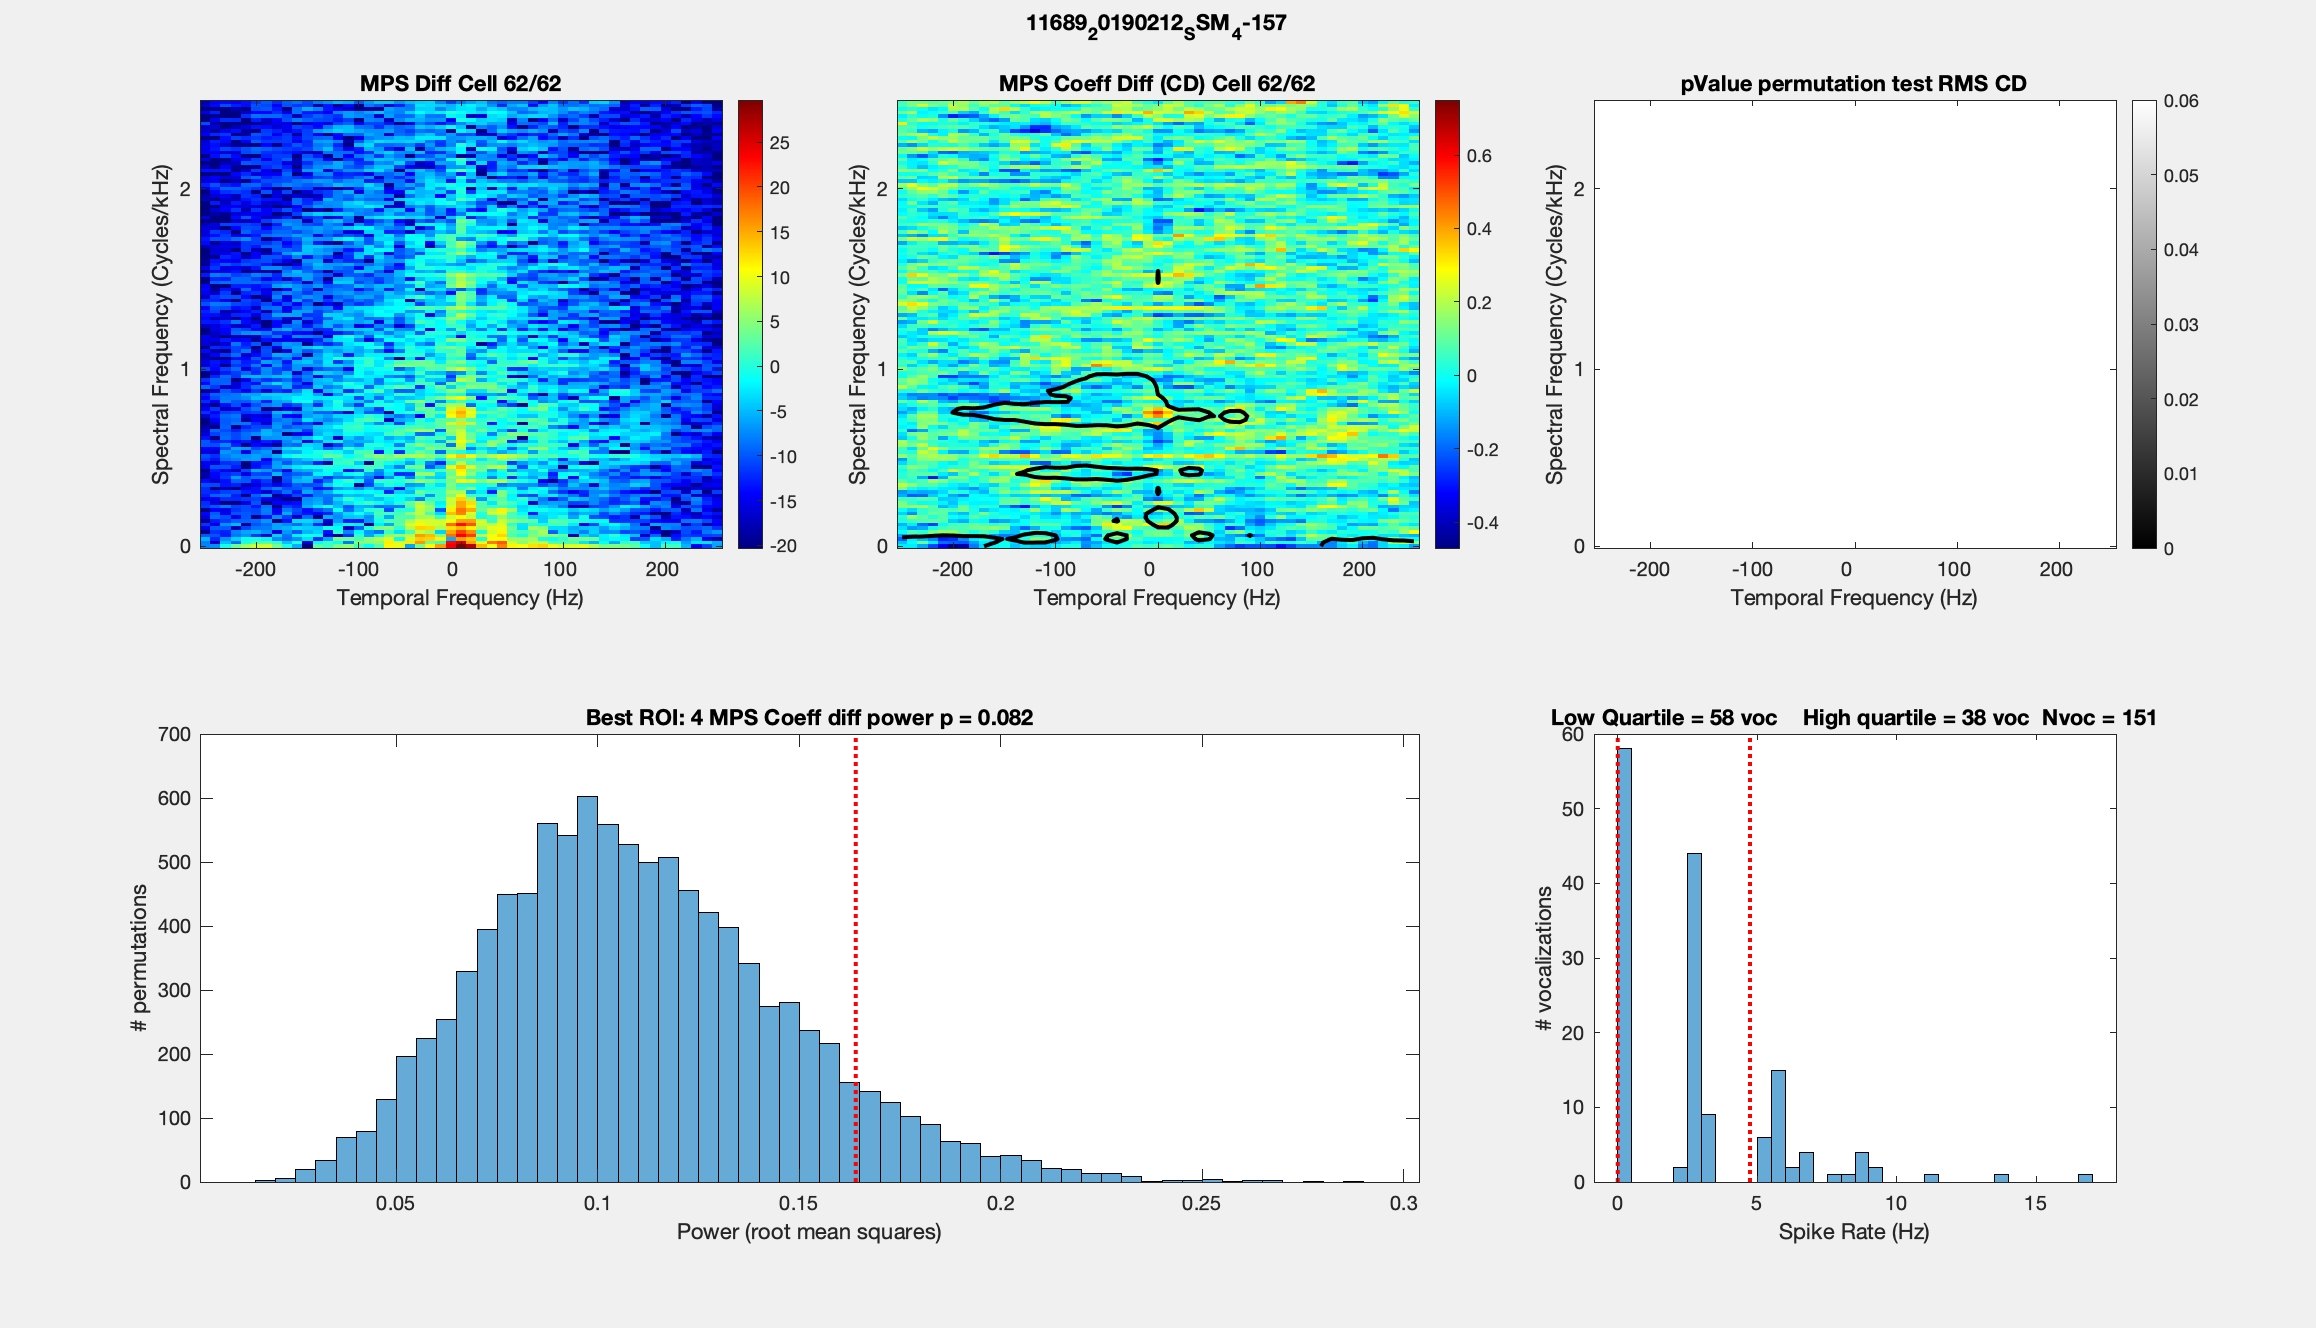

NBoot = 10000;
ClustNum = 4;
DBNoise = 50;

MPSDiff_Trills = cell(NC,1);
% MPSDiff_p = cell(NC,1);
MPSDiff_Trills_rand_all = cell(NC,1);
MPSDiff_Trills_randRMS = cell(NC,1);
MPSDiff_Trills_RMS = nan(NC,length(ROI));
MPSDiff_Trills_RMSp = nan(NC,length(ROI));


MPSCoeffDiff_Trills = cell(NC,1);
% MPSCoeffDiff_p = cell(NC,1);
MPSCoeffDiff_Trills_rand_all = cell(NC,1);
MPSCoeffDiff_Trills_randRMS = cell(NC,1);
MPSCoeffDiff_Trills_RMS = nan(NC,length(ROI));
MPSCoeffDiff_Trills_RMSp = nan(NC,length(ROI));

Wf_pos = logical((Trills_wf>0) .* (Trills_wf*10^3<=2.5));
Wt_narrow = logical((Trills_wt>=-250) .* (Trills_wt<=250));

for cc=1:NC
    % find the extreme quartiles in average neural activity
    Quartiles = prctile(MeanRateTrills{cc},[25 75]);
    Idx = nan(length(MeanRateTrills{cc}),1);
    Idx(MeanRateTrills{cc}<=Quartiles(1)) = 1;
    Idx(MeanRateTrills{cc}>Quartiles(2)) = 2;
    ClustMaxD = unique(Idx);
    
    % Get the average MPS for both clusters
    Trills_mps_local = cell(length(ClustMaxD),1);
    for Clust = 1:length(ClustMaxD)
        Trills_mps_local{Clust} = mean([Trills_mps{cc}{Idx == ClustMaxD(Clust)}],2);
    end

    % Get the average MPS over all vocalizations for that cell
    Trills_mps_mean = mean([Trills_mps{cc}{:}],2);

    % Get the MPS difference between the 2 clusters (High rate - low rate)
    MPSDiff_vec = Trills_mps_local{2} - Trills_mps_local{1};
    MPSDiff_mat = reshape(MPSDiff_vec, length(Trills_wf), length(Trills_wt));
    MPSDiff_Trills{cc} = MPSDiff_mat(Wf_pos,Wt_narrow);
    MPSDiff_vec_upper = reshape(MPSDiff_Trills{cc},numel(MPSDiff_Trills{cc}),1);

    % Get the MPS coefficient difference between the 2 clusters
    MPSCoeffDiff_vec = MPSDiff_vec ./ Trills_mps_mean;
    MPSCoeffDiff_mat = reshape(MPSCoeffDiff_vec, length(Trills_wf), length(Trills_wt));
    MPSCoeffDiff_Trills{cc} = MPSCoeffDiff_mat(Wf_pos,Wt_narrow);
    MPSCoeffDiff_vec_upper = reshape(MPSCoeffDiff_Trills{cc},numel(MPSCoeffDiff_Trills{cc}),1);

    % randomly sample groups of vocalizations, calculate distribution of MPSDiff
    MPSDiff_rand = cell(NBoot,1);
    MPSDiff_Trills_randRMS{cc} = nan(NBoot,length(ROI));% This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
    MPSCoeffDiff_rand = cell(NBoot,1);
    MPSCoeffDiff_Trills_randRMS{cc} = nan(NBoot,length(ROI)); % This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
%     figure
%     tiledlayout(3,3)
    for bb=1:NBoot
        Idx_rand = Idx(randperm(length(Idx)));
        % Get the average MPS for both clusters
        Trills_mps_local = cell(length(ClustMaxD),1);
        for Clust = 1:length(ClustMaxD)
            Trills_mps_local{Clust} = mean([Trills_mps{cc}{Idx_rand == ClustMaxD(Clust)}],2);
        end

        % Get the MPS difference between the 2 clusters
        MPSDiff_rand_vec = Trills_mps_local{1} - Trills_mps_local{2};
        MPSDiff_rand_mat = reshape(MPSDiff_rand_vec, length(Trills_wf), length(Trills_wt));
        MPSDiff_rand_mat_upper = MPSDiff_rand_mat(Wf_pos,Wt_narrow);
        MPSDiff_rand{bb} = reshape(MPSDiff_rand_mat_upper, numel(MPSDiff_rand_mat_upper),1);
        for rr=1:length(ROI)
            ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
            MPSDiff_Trills_randRMS{cc}(bb,rr) = (mean(MPSDiff_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end
        
        % Get the MPS coefficient difference between the 2 clusters
        MPSCoeffDiff_rand_vec = MPSDiff_rand_vec ./ Trills_mps_mean;
        MPSCoeffDiff_rand_mat = reshape(MPSCoeffDiff_rand_vec, length(Trills_wf), length(Trills_wt));
        MPSCoeffDiff_rand_mat_upper = MPSCoeffDiff_rand_mat(Wf_pos,Wt_narrow);
        MPSCoeffDiff_rand{bb} = reshape(MPSCoeffDiff_rand_mat_upper, numel(MPSCoeffDiff_rand_mat_upper),1);
        for rr=1:length(ROI)
            ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
            MPSCoeffDiff_Trills_randRMS{cc}(bb,rr) = (mean(MPSCoeffDiff_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end

%         if (~rem(bb,NBoot/10)) && (bb<NBoot)
%             nexttile
%             plot_mps(MPSDiff_rand_mat, Trills_wf, Trills_wt,DBNoise,0, [0 2.5], [-200 200])
%         end
    end
    MPSDiff_Trills_rand_all{cc} = [MPSDiff_rand{:}]';
    MPSCoeffDiff_Trills_rand_all{cc} = [MPSCoeffDiff_rand{:}]';
    
    % Not useful anymore
%     MPSDiff_p{cc} = sum(abs(MPSDiff_rand_all{cc})>abs(MPSDiff_vec_upper'))./NBoot;
%     MPSDiff_pclean = imgaussfilt(MPSDiff_p{cc},0.5);
%     MPSDiff_pclean(MPSDiff_pclean>1) = 1;
%     MPSCoeffDiff_p{cc} = sum(abs(MPSCoeffDiff_rand_all{cc})>abs(MPSCoeffDiff_vec_upper'))./NBoot;
%     MPSCoeffDiff_pclean = imgaussfilt(MPSCoeffDiff_p{cc},0.5);
%     MPSCoeffDiff_pclean(MPSCoeffDiff_pclean>1) = 1;
%   
    % Calculate for each ROI the probability of getting the average RMS
    % we're getting in the observed data
    MPSDiff_RMS_p_map = ones(size(ROI{1}));
    MPSCoeffDiff_RMS_p_map = ones(size(ROI{1}));
    for rr=1:length(ROI)
        ROI_local = reshape(ROI{rr},numel(ROI{rr}),1);
        MPSDiff_Trills_RMS(cc,rr) = (mean(MPSDiff_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSDiff_Trills_RMSp(cc,rr) = sum(MPSDiff_Trills_randRMS{cc}(:,rr)>=MPSDiff_Trills_RMS(cc,rr))/NBoot;
        MPSDiff_RMS_p_map(logical(ROI{rr})) = MPSDiff_Trills_RMSp(cc,rr);
        MPSCoeffDiff_Trills_RMS(cc,rr) = (mean(MPSCoeffDiff_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSCoeffDiff_Trills_RMSp(cc,rr) = sum(MPSCoeffDiff_Trills_randRMS{cc}(:,rr)>=MPSCoeffDiff_Trills_RMS(cc,rr))/NBoot;
        MPSCoeffDiff_RMS_p_map(logical(ROI{rr})) = MPSCoeffDiff_Trills_RMSp(cc,rr);
    end

    F1 = figure(1);
    clf(F1)
    set(F1,'Visible','on')
    tiledlayout(2,3)
    nexttile
%     MPS_rescale = MPSDiff{cc};
%     MinMPS = min(min(MPSDiff{cc}));
%     MPS_rescale = MPS_rescale + (-MinMPS +1);
    plot_mps(abs(MPSDiff_Trills{cc}), Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,1, [0 2.5], [-250 250]);
    title(sprintf('MPS Diff Cell %d/%d', cc, NC))
    
    NT = nexttile;
    plot_mps(MPSCoeffDiff_Trills{cc}, Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,0, [0 2.5], [-250 250]);
    title(sprintf('MPS Coeff Diff (CD) Cell %d/%d', cc, NC))
    hold on
    [~, Cplot] = contour(NT,CVMPS4Contour,[Level Level]);
    Cplot.LineWidth = 2;
    Cplot.Color = 'k';
    hold off
    
%     nexttile
%     % plot the pvalue in each region of interest for Power of
%     % difference
%     Im = imagesc(MPSDiff_RMS_p_map);
%     colorbar()
%     axis xy
%     colormap(Im.Parent,'gray')
%     Im.Parent.CLim = [0 0.05];
%     % get nice X and y tick labels
%     MaxWf = max(floor(Wf_ROI*10^3));
%     YTickLabel=0:MaxWf;
%     YTick = nan(length(YTickLabel),1);
%     for yy=1:length(YTick)
%         YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
%     end
%     set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
%     MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
%     XTickLabel = -MaxWt:100:MaxWt;
%     XTick = nan(length(XTickLabel),1);
%     for xx=1:length(XTick)
%         [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
%     end
%     set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
%     ylabel('Spectral Frequency (Cycles/kHz)')
%     xlabel('Temporal Frequency (Hz)')
%     title('pValue permutation test on RMS difference')

    
    NT = nexttile;
    % plot the pvalue in each region of interest for Power of
    % difference coefficient
    Im = imagesc(MPSCoeffDiff_RMS_p_map);
    colorbar()
    axis xy
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_ROI*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    ylabel('Spectral Frequency (Cycles/kHz)')
    xlabel('Temporal Frequency (Hz)')
    title('pValue permutation test RMS CD')
    
    
    nexttile([1,2])
    % Best ROI
    [p_BestROI,IndBestROI] = min(MPSCoeffDiff_Trills_RMSp(cc,:));
    histogram(MPSCoeffDiff_Trills_randRMS{cc}(:,IndBestROI)); hold on; V=vline(MPSCoeffDiff_Trills_RMS(cc,IndBestROI));V.LineWidth = 2;hold off; xlabel('Power (root mean squares)'); ylabel('# permutations'); title(sprintf('Best ROI: %d MPS Coeff diff power p = %.3f', IndBestROI, p_BestROI));
   
    nexttile([1 1])
    histogram(MeanRateTrills{cc}, 'BinWidth',0.5); hold on; V = vline(Quartiles(1)); V.LineWidth=2;V = vline(Quartiles(2)); V.LineWidth=2;hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations'); title(sprintf('Low Quartile = %d voc    High quartile = %d voc  Nvoc = %d', sum(Idx==1), sum(Idx==2), length(Idx)))
    [~,Name] = fileparts(ListCellsVocTrill(cc));
    suplabel(Name,'t');
    drawnow
    if any(MPSCoeffDiff_Trills_RMSp(cc,:)<0.06)
        orient(F1,'landscape')
        print(F1,fullfile(Path2AllData,sprintf('RateNeuralDist_MPS_%s.pdf', Name)),'-dpdf','-fillpage')
    end
%     pause()
    
end

function [YPerStim, YPerStimt, YMeanPerStim] = get_y(SAT, Duration,Delay,TR)
        % Calculate the time varying rate applying a gaussian window TR on the
        % spike pattern. The spike pattern considered starts Delay(1) ms
        % before the onset of the vocalization and stops Delay(2) ms after the
        % onset of the vocalization
        % The width of the Gaussian is determined by TR, the Sampling rate
        % is kept as 1kHz
        % Also calculates the average spike rate during the
        % vocalization starting Delay(1)  before stim onset and stopping at stim offset, YMeanPerStim is in Hz
        DebugFig =0;
        % Gaussian window of 2*std equal to TR (68% of Gaussian centered in TR)
        nStd =(max(Duration) - Delay(1) + Delay(2))/10; % before set as 4
        Tau = (TR/2);
        T_pts = (0:2*nStd*Tau) - nStd*Tau; % centered tpoints around the mean = 0 and take data into account up to nstd away on each side
        Expwav = exp(-0.5*(T_pts).^2./Tau^2)/(Tau*(2*pi)^0.5);
        Expwav = Expwav./sum(Expwav);
        
        % Time slots for the neural response enlarge by Delay/2 
        YPerStimt = 1.5*Delay(1) : (Delay(2)-1);

        % Preallocate for speed
        YPerStim = nan(length(Duration), length(YPerStimt));
        YMeanPerStim = nan(length(Duration),1);
        
        % Loop through the stimuli and fill in the matrix
        for stim=1:length(Duration)
            % Get all the spikes from Delay(1) up to the end of the  vocalization
            YMeanPerStim(stim) = sum((SAT{stim}>=Delay(1)) .* (SAT{stim}<=(Duration(stim))))/((-Delay(1)+Duration(stim))*10^(-3));
            
            % Get the spike pattern
            SpikePattern = zeros(1,length(YPerStimt));
            for isp = 1:length(SAT{stim})
                SpikeInd = round(SAT{stim}(isp));
                if (SpikeInd>=1.5*Delay(1)) && (SpikeInd<=Delay(2)-1)
                    SpikePattern(SpikeInd - 1.5*Delay(1) +1) = SpikePattern(SpikeInd - 1.5*Delay(1) +1) +1;
                end
            end
            
            % Convolve with Gaussian to obtain our smooth time varying spike train
            YPerStim(stim, :) = conv(SpikePattern, Expwav,'same');
            if sum(YPerStim(stim, :))~=sum(SpikePattern)
                YPerStim(stim, :) = YPerStim(stim, :) ./ sum(YPerStim(stim, :)) .* sum(SpikePattern);
            end

            if DebugFig
                figure(200) %#ok<UNRCH>
                set(gcf,'Visible','on')
                clf
                plot(YPerStimt,YPerStim(stim, :), 'LineWidth',2)
                xlabel('Time ms')
                ylabel('Spike Rate mHz (/ms)')
                title(sprintf('Stim %d/%d',stim,length(Duration)));
                %         RemainTime = length(XPerStim_temp) - (length(XPerStim{stim})-1)*(1/Fs*10^3);
                %         XPerStimt{stim} = RemainTime/2+(1/Fs*10^3)*(0:(length(XPerStim{stim})-1));
                hold on
                SpikeTimes = YPerStimt(logical(SpikePattern));
                for ss = 1:length(SpikeTimes)
                    V=vline(SpikeTimes(ss), 'k-');
                    V.LineWidth = 2;
                    hold on
                end
                pause(1)
            end

        end

        % Supress the 0.5 delay we added to get a nicer edge
        IndGood =  YPerStimt>=Delay(1);
        YPerStimt = YPerStimt(IndGood);
        YPerStim = YPerStim(:,IndGood);
end

function [MPS, Wf, Wt] = mps_calc(Y, FS,Max_freq)
        % spectrogram parameters
        Spec_sample_rate = 1000; % sampling rate Hz
        Freq_spacing = 100; % width of the frequency window for the FFT Hz
        Min_freq = 100; % highpass filter before FFT Hz
        if nargin<3
            Max_freq = 50000; % low pass filter before FFT
        end
        % MPS parameters
        Window = 0.1;% duration of the window in sec when binning the spectrogram
        Norm = 1; % boolean to indicate if you want to normalize or not the MPS (zscore of the spectrogram before 2Dfft
        BiosoundObj = py.soundsig.sound.BioSound(py.numpy.array(Y), pyargs('fs', FS));
        spectroCalc(BiosoundObj, Spec_sample_rate, Freq_spacing, Min_freq, Max_freq)
        mpsCalc(BiosoundObj, Window, Norm)
        MPS = double(BiosoundObj.mps);
        Wf = double(BiosoundObj.wf);
        Wt = double(BiosoundObj.wt);
end

function [MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,Log, YLim, XLim,CLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<5
        Log=1;
    end

    if nargin<6
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<7
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<8
        CLim = nan;
    end
    if nargin<9
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet');
    colorbar()
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_local*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end

function outyy = mysmooth(yy,Span)
        if nargin<2
            Span = 5;
        end
        outyy=nan(size(yy));
        for ii=1:length(yy)
            if ii==1 || ii==length(yy)
                outyy(ii) = yy(ii);
            elseif ii<=((Span-1)/2)
                HalfSpan = ii-1;
                outyy(ii) = nanmean(yy(1:(ii+HalfSpan)));
            elseif (length(yy)-ii) <= ((Span-1)/2)
                HalfSpan = length(yy)-ii;
                outyy(ii) = nanmean(yy((ii-HalfSpan):end));
            else
                HalfSpan = (Span-1)/2;
                outyy(ii) = nanmean(yy((ii-HalfSpan):(ii+HalfSpan)));
            end
        end
end


function [Idx, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum, Method, Counter)
    if nargin<3
        Method = {'kmeans', 'RecursivePoint'}; % first element 'kmeans' or 'kmedoids'; second element 'RecursivePoint' 'RecursiveCluster' or 'SecondMaxD'
    end
    if nargin<4
        Counter = 0; % Count the number of recursive loops authorized MaxCounter
    end
    MaxCounter = 5;
    Counter=Counter+1;
    NData = size(Score,1);
    % run a Kmeans with ClustNum clusters
    for Attempt = 1:1000
        if strcmp(Method{1},'kmeans')
            Idx = kmeans(Score,ClustNum, 'Distance', 'sqeuclidean','Replicates',200, 'Display','off');
            % find the most extreme clusters by calculating the distance of their
            % centroids in the PC space
            Centroids_Score = nan(ClustNum,size(Score,2));
            for clust = 1:ClustNum
                Centroids_Score(clust,:) = mean(Score(Idx==clust,:));
            end
            D = squareform(pdist(Centroids_Score, 'seuclidean'));
        elseif strcmp(Method{1}, 'kmedoids')
            [Idx, Medoids] = kmedoids(Score,ClustNum, 'Distance', 'sqeuclidean','Replicates',4);
            % find the most extreme clusters by calculating the distance of their
            % centroids/Medoids in the PC space
            D = squareform(pdist(Medoids, 'seuclidean'));
        end
        UD = unique(D);
        SortD = sort(UD, 'descend');
        if strcmp(Method{2}, 'SecondMaxD')
            MaxD = SortD(2);
        else
            MaxD = SortD(1);
        end
        IndMax = find(D==MaxD);
        [I, J] = (ind2sub(size(D),IndMax(1)));
        ClustMaxD = [I J];
        if (sum(Idx==I)>=(NData/(2*ClustNum))) && (sum(Idx==J)>=(NData/(2*ClustNum)))
            break
        end
    end

    if ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursivePoint') && (Counter<=MaxCounter)
        % There is an outlier that drives the clustering, let's cluster the
        % data without that data point
        if (sum(Idx==I)==1)
            Outlier = find(Idx==I);
        elseif (sum(Idx==J)==1)
            Outlier = find(Idx==J);
        end
        Score(Outlier,:)=[];
        fprintf(1,'Recursive loop %d attempting data removal for finding correct size extreme clusters', Counter)
        [Idx_local, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum, Method, Counter);
        if Counter>MaxCounter
            Idx=nan;
            ClustMaxD = nan;
            return
        end
        Idx(setdiff(1:NData, Outlier)) = Idx_local;
        Idx(Outlier) = ClustNum +1;
    elseif ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursivePoint') && (Counter>MaxCounter)
        warning('Outliers are driving the clustering algorithms and we already tried to correct with %d recursive loops on data removal without success', MaxCounter)
        Idx = nan;
        ClustMaxD = nan;
        return
    end

    if ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursiveCluster') && ClustNum>2
        % There is an outlier that drives the clustering, let's cluster the
        % data with less groups
        fprintf(1,'Recursive loop %d attempting # clusters diminution for finding correct size extreme clusters', Counter)
        [Idx, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum-1, Method, Counter);
        
    elseif ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursiveCluster') && ClustNum==2
        warning('Reaching the minimum Nb cluster attempting to take the second furthest clusters')
        ClustNum = ClustNum+Counter-1;
        Method{2}='SecondMaxD';
        [Idx, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum, Method, Counter);
    elseif ((sum(Idx==I)==1) || (sum(Idx==J)==1))
        warning('Cannot find extreme clusters')
        Idx = nan;
        ClustMaxD = nan;
    end

    
end


function plot_extreme_clusters(Score_local,RateTrills_mat_local, SoundFeature_mat,  NeMatrix, AcMatrix, MeanFeature, Featurename)
% run a Kmeans with 4 clusters
[Idx, ClustMaxD] = find_extreme_clusters(Score_local, 4);
    

% sort the matrix of distances according to clusters and plot
% sort rows
[~, SortIndex] = sort(Idx);
AcData = AcMatrix(SortIndex, :);
NeData = NeMatrix(SortIndex,:);
% sort columns
AcData = AcData(:,SortIndex);
NeData = NeData(:, SortIndex);

F = figure();
set(F,'Visible','on')
t=tiledlayout(11,2);
nexttile([3 1])
imagesc(AcData)
colorbar()
title(sprintf('%s distance',Featurename))
nexttile([3 1])
imagesc(NeData)
colorbar()
title('Neural distance')

% Plot the Time varying rates that correspond to each cluster

nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    plot(RateTrills_mat_local(Idx == ClustMaxD(clust),:)', '-', 'Color', Col, 'LineWidth',1)
    hold on
end
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
xlabel('Time (ms)')
ylabel('Spike Rate')
XLim = get(gca,'XLim');
hold off

% PLot the time varying feature that correspond to each cluster
SoundFeature_mat_local = SoundFeature_mat - repmat(MeanFeature, size(SoundFeature_mat,1),1);
nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    plot(SoundFeature_mat_local(Idx == ClustMaxD(clust),:)', '-', 'Color', Col, 'LineWidth',1)
    hold on
end
xlabel('Time (ms)')
ylabel(sprintf('ZS %s',Featurename))
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
set(gca, 'XLim', XLim)
hold off

nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    shadedErrorBar([],mean(RateTrills_mat_local(Idx == ClustMaxD(clust),:)), std(RateTrills_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
    hold on
end
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
xlabel('Time (ms)')
ylabel('Spike Rate')
set(gca, 'XLim', XLim)
hold off

nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    shadedErrorBar([],mean(SoundFeature_mat_local(Idx == ClustMaxD(clust),:)), std(SoundFeature_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
    hold on
end
xlabel('Time (ms)')
ylabel(sprintf('ZS %s',Featurename))
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
set(gca, 'XLim', XLim)
hold off
end


function plot_spectro(logB,DBNOISE, to, fo, f_low, f_high,t_max)
%     logB = 20*log10(abs(s));
    maxB = max(max(logB));
    minB = maxB-DBNOISE;            

    Im = imagesc(to*1000,fo,logB);          % to is in seconds
    axis xy;
    caxis('manual');
    caxis([minB maxB]); 
    cmap = spec_cmap();
    colormap(Im.Parent,cmap);

    v_axis = axis; 
    v_axis(3)=f_low; 
    v_axis(4)=f_high;
    v_axis(2) = t_max;
    axis(v_axis);
    xlabel('time (ms)'), ylabel('Frequency');
end